## Notes

- Similar to A. H. Gazi et al., TBME, 2022 paper, only the biosignal data collected before lunch on the first day of the trauma recall + nVNS protocol are used

- Similar to A. H. Gazi et al., JMIR, 2020 paper, state-space models are fit in modal form (a.k.a. Jordan canonical form)

- No regularization is used for now (underfitting is more likely in this case compared to overfitting)

- Each protocol condition is considered its own known input, $u_i$. Since we have neutral, trauma, and VNS as protocol conditions, $i\in \left\lbrace 1,2,3\right\rbrace$.

## Clear

clear
clc

## Fit Models or Load Models?

This boolean, if set to false, allows you to run this script in its entirety without refitting models

Otherwise, if set to true, models will be refit, saved (overwriting previously fit models), and then loaded for analysis

fitModels = false;

if ~fitModels
    % If we are planning to load models, give the user the option to change
    % loading directory
    modelSave_dir = ['Saved Models', filesep, 'LSSM_2024_03', filesep];
end

## Debug Mode to Generate and Save Plots?

When this boolean is set to true, plots are generated and saved for debugging purposes

debugMode = true;

## Ignore any subjects?

List out the subject numbers you would like to ignore

subj_ignore = [];
% Example
% subj_ignore = [104, 105, 111, 114, 117, 125, 135, 137, 140, 141, 144, 149, ...
%     150, 151, 152, 156];

## Setup

### Subject Classes

% Active non-PTSD
active_nonP = [108, 110, 111, 119, 120, 122, 123, 125, 126, ...
    129, 132];
active_nonP_noB = 106;   % No brain data available (relevant to TBME 2022 paper)
active_nonP_all = [active_nonP, active_nonP_noB];   % Concatenate

% Sham non-PTSD
sham_nonP = [124, 131, 133, 137, 139, 140, 142, 143];
sham_nonP_noB = [104, 105, 107, ...
    109, 113, 116];      % No brain data available (relevant to TBME 2022 paper)
sham_nonP_all = [sham_nonP, sham_nonP_noB];     % Concatenate

% Active PTSD
active_PTSD = [114, 115, 117, 135, 141, 145, 147, 150, 151, ...
    155, 156];
active_PTSD_noB = [102, 118];
active_PTSD_all = [active_PTSD, active_PTSD_noB]; % Concatenate

% Sham PTSD
sham_PTSD = [121, 128, 130, 134, 138, 144, 148, 149, 152, 153, ...
    154];
sham_PTSD_noB = [];
sham_PTSD_all = [sham_PTSD, sham_PTSD_noB];     % Concatenate

% All subjects
subjects = [active_nonP, sham_nonP, active_PTSD, sham_PTSD];
subjects_noB = [active_nonP_noB, sham_nonP_noB, ...
    active_PTSD_noB, sham_PTSD_noB];    % No brain data available
subjects_all = [subjects, subjects_noB];    % Concatenate

Compute set differences to ignore subjects specified

active_nonP_all = setdiff(active_nonP_all, subj_ignore);
sham_nonP_all = setdiff(sham_nonP_all, subj_ignore);
active_PTSD_all = setdiff(active_PTSD_all, subj_ignore);
sham_PTSD_all = setdiff(sham_PTSD_all, subj_ignore);
subjects_all = setdiff(subjects_all, subj_ignore);

### Directories Relative to Script

% Directory where processed physiological features are stored
procFeat_dir = ['Processed Features', filesep];

% Directory where protocol timings and other info are stored
% (e.g., VNS amplitudes)
protInfo_dir = ['Protocol Info', filesep];

% If we are fitting models, we need to specify the saving and loading
% directory for the first time
if fitModels
    modelSave_dir = ['Saved Models', filesep, 'LSSM_2024_03', filesep];
end

plotSave_dir = ['Results Figures', filesep, 'LSSM_2024_03', filesep];

## Hyperparameters

### Non-Optimized HPs

Which features to use as system output, $y$?

% Beat-by-beat time series
featNames_TS_beat = {'HR', 'PEP', 'PPGamp', 'PAT', 'PTT_recip'};

% Breath-by-breath time series
featNames_TS_resp = {'RR', 'Ti', 'Te', 'Ti_over_Te'};

% EDA time series features
% featNames_TS_eda = {};

% HRV features
featNames_var_HRV = {};
% featNames_var_HRV = {'RMSSD', 'sdnn', 'lfhf', 'sd1sd2'};

% RPV features
featNames_var_RPV = {};
% featNames_var_RPV = {'RR_AR_1', 'RR_IQR', 'Ti_AR_1', 'Ti_IQR', ...
%     'Te_AR_1', 'Te_IQR'};


% Concatenate the names of desired features in case models are not fit
featNames_desir = [featNames_TS_beat, featNames_TS_resp, ...
    featNames_var_HRV, featNames_var_RPV];
% featNames_desir = [featNames_TS_beat, featNames_TS_resp, ...
%     featNames_TS_eda, featNames_var_HRV, featNames_var_RPV];

Others

% Input option
inputOpt = 'vtn';

% Frequency to resample physiological time series to
resamp_Fs = 0.2;

% Scale features to unit variance?
unitVar_feat = false;

% Train-Test Split
trTest_split = 6.5;     % Split between scans 6 and 7

### Optimized HPs

% Model orders to optimize over
% (for now, only constraint is to keep state dim <= feature dim)
% (we also keep state dim >= 3 so I don't have to change plotting code)
modelOrders = 3:numel(featNames_desir);

Input delays to optimize over

% Should be <= 10 s
neutralDelays = 0:floor(10*resamp_Fs);
traumaDelays = 0:floor(10*resamp_Fs);

% Should be >= 5 s and <= 25 s
vnsDelays = ceil(5*resamp_Fs):floor(25*resamp_Fs);

## Model Fitting

We are fitting a non-autonomous state-space model in innovations form:


$$x_{k+1} ={\textrm{Ax}}_k +\left(b_v u_{v_{k-\tau {\;}_v } } +b_t u_{t_{k-\tau {\;}_t } } +b_n u_{n_{k-\tau_n } } \right)+{\textrm{Ke}}_k$$



$$y_k ={\textrm{Cx}}_k +e_k$$


where $k$ is the discrete timestep, $$x \in \mathbb{R}^m$$ is the latent state, $A$ is the system matrix, $b_v$ is the input-to-state matrix for VNS, $u_v$ represents VNS, $\tau {\;}_v$ is the input delay for VNS, $b_t$ is the input-to-state matrix for trauma recall, $u_t$ represents on-off trauma recall, $\tau {\;}_t$ is the input delay for trauma recall, $b_n$ is the input-to-state matrix for the neutral condition, $u_n$ represents on-off neutral condition, $\tau {\;}_n$ is the input delay for the neutral condition, $K$ is the Kalman predictor gain, $e$ is the residual, $y$ is the vector of observables, and $C$ is the output matrix.

Regardless of subject class or brain data availability, same modeling process performed, so we loop through them in parallel

if fitModels
    % This if statement just checks if a parallel session
    % is already open to avoid the error that pops up if a
    % session is already open and you try to create another one
    if isempty(gcp('nocreate'))
        parpool('local', 12);   % Meant to be run on Gazilla
    end
    
    % Parallel for loop through all subjects
    parfor sub = 1:length(subjects_all)
        % Store subject number
        subjectNumber = subjects_all(sub);
        
        % Output progress to user
        timeNow = datetime('now','TimeZone','local',...
            'Format','d-MMM-y HH:mm:ss Z');
        disp(['Started on subject ', num2str(subjectNumber), ...
            ' at ', datestr(timeNow)])

### Load Necessary Data for Model Fitting  

Load physiological features

        % Filename
        procFeat_file = [procFeat_dir, 'S', ...
            num2str(subjectNumber), '_procFeat.mat'];
        
        % I need to ensure transparency for parfor loop
        data_struct = load(procFeat_file, 'physFeatures_beat', ...
            'physFeatures_resp', 'physFeatures_HRV', ...
            'physFeatures_RPV');
        %     data_struct = load(procFeat_file, 'physFeatures_beat', ...
        %         'physFeatures_resp', physFeatures_eda, ...
        %         'physFeatures_HRV', 'physFeatures_RPV');
        physFeatures_beat = data_struct.physFeatures_beat;
        physFeatures_resp = data_struct.physFeatures_resp;
        %     physFeatures_eda = data_struct.physFeatures_eda;
        physFeatures_HRV = data_struct.physFeatures_HRV;
        physFeatures_RPV = data_struct.physFeatures_RPV;

    Load protocol timings and VNS amplitudes

        % Filename
        protInfo_file = [protInfo_dir, 'S', ...
            num2str(subjectNumber), '_protInfo.mat'];
        
        % I need to ensure transparency for parfor loop
        data_struct = load(protInfo_file, 'times', 'VNSamps');
        protTimings = data_struct.times;
        VNSamps = data_struct.VNSamps;

### Combine Desired Phys. Features

        % This function takes the before lunch segments
        % of the desired features, combines them into a single
        % struct, and then returns that struct making sure names
        % and fields are in equivalent order
        % Note that in doing so, it takes the midpoint of each
        % variability window as the corresponding timepoint to
        % return one time vector for HRV and RPV features
        [feat_desir, featNames_desir] = combo_desirFeat(...
            physFeatures_beat, featNames_TS_beat, ...
            physFeatures_resp, featNames_TS_resp, ...
            physFeatures_HRV, featNames_var_HRV, ...
            physFeatures_RPV, featNames_var_RPV);
        %     [feat_desir, featNames_desir] = combo_desirFeat(...
        %         physFeatures_beat, featNames_TS_beat, ...
        %         physFeatures_resp, featNames_TS_resp, ...
        %         physFeatures_eda, featNames_TS_eda, ...
        %         physFeatures_HRV, featNames_var_HRV, ...
        %         physFeatures_RPV, featNames_var_RPV);
        
        if debugMode
            % Save plots to see what we've done so far
            plotFeat_structs(6, [plotSave_dir, 'Original Features', ...
                filesep, 'Subject ', ...
                num2str(subjectNumber), ' '], ...
                'featNew', feat_desir);
        end

### Downsample Features to Desired Frequency

NOTES: Based on my inspection of plots on 1/9/2022, it seems that this resampling is usually fine, EXCEPT when large portions of data are missing. For these large portions, linear interpolation removes all of the natural variability expected and instead draws these nasty straight lines that look odd as hell

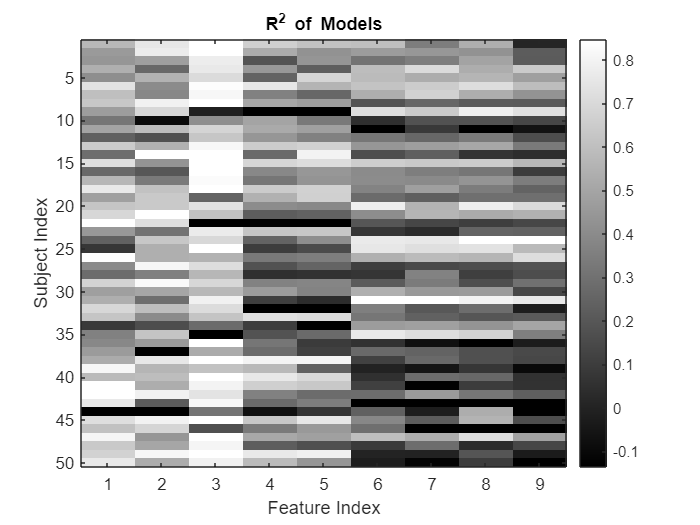

        % This function takes all the features and resamples
        % them to the desired frequency using the specified
        % interpolation method
        feat_resamp = resamp_feat(feat_desir, resamp_Fs, 'linear');
        
        if debugMode
            % Save plots to see what we've done so far
            plotFeat_structs(6, [plotSave_dir, 'Resampled Features', ...
                filesep, 'Subject ', ...
                num2str(subjectNumber), ' '], ...

                'featOverlay', 'featNew', feat_resamp, ...
                'featOld', feat_desir);
        end

### Align all Features According to Last Start and First End Times

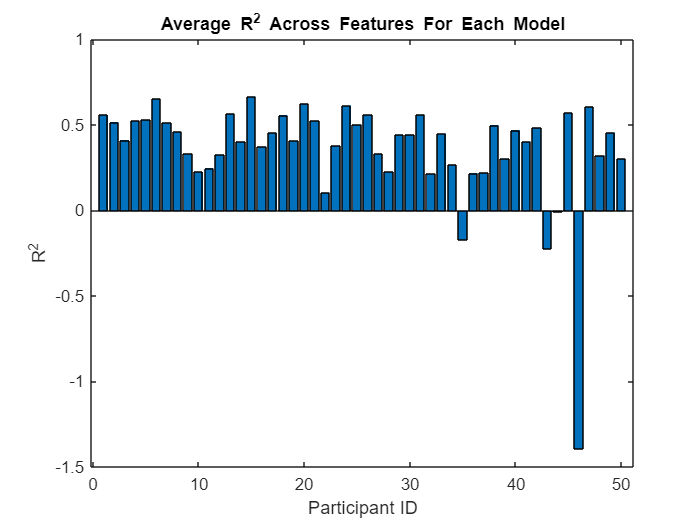

        % This function takes the resampled features and aligns
        % them according to the latest start time of all the features

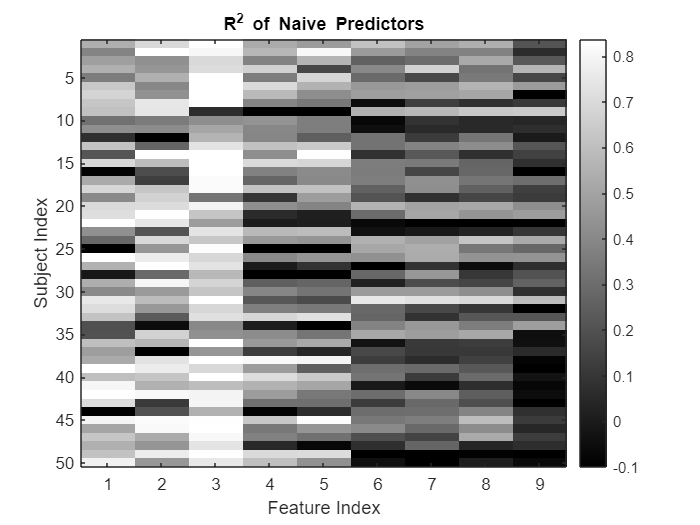

        % and the earliest end time of all the features using the
        % specified interpolation method
        feat_align = align_feat(feat_resamp, resamp_Fs, 'linear');
        
        if debugMode
            % Save plots to see what we've done so far
            plotFeat_structs(6, [plotSave_dir, 'Aligned Features', ...
                filesep, 'Subject ', ...

                num2str(subjectNumber), ' '], ...
                'featOverlay', 'featNew', feat_align, ...
                'featOld', feat_resamp);
        end

### Shift the Features to Define Equilibrium

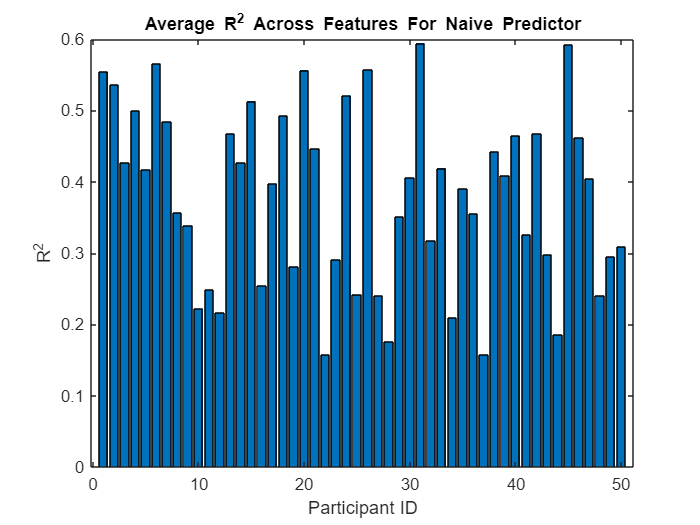

        % Here, we subtract away a specified value

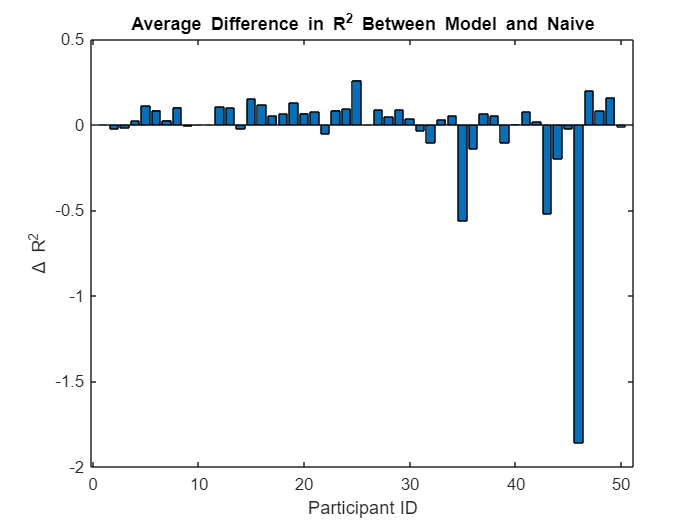

        % ("rest", mean, etc.) from each of the
        % feature time series because stable linear
        % systems, in the absence of noise, converge to "0".
        % So, we are redefining the equilibrium to be the
        % "rest", the mean, etc. for the system to be more
        % legitimate.
        feat_equil = equil_feat(feat_align, 'rest');
        

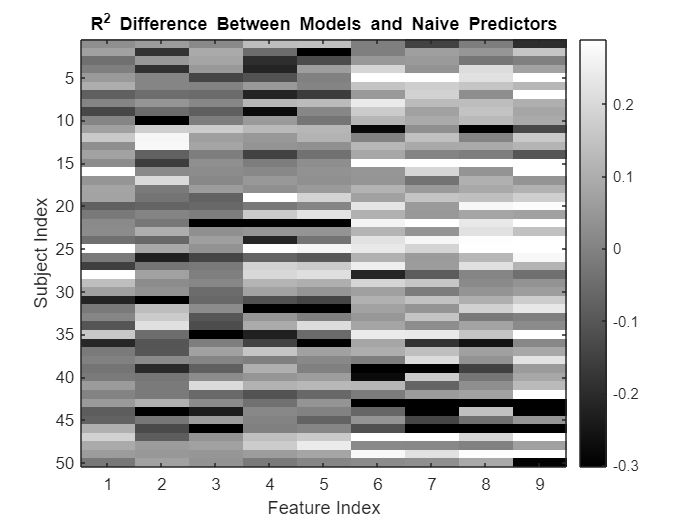

        if debugMode
            % Save plots to see what we've done so far
            plotFeat_structs(6, [plotSave_dir, 'Shifted Features', ...
                filesep, 'Subject ', ...
                num2str(subjectNumber), ' '], ...
                'featOverlay', 'featNew', feat_equil, ...
                'featOld', feat_align);

        end

### Form the Feature Array

        % This function takes the feature structure and now that

ans = -0.0203

        % the features are all the same length and aligned to the

ans = 0.0422

        % same time points, combines the features such that each

ans = 0.3593

        % one is its own column and each time point is its own row.

ans = 0.4409

        % The function also returns a single time vector that has

ans = 1.1919

        % the same number of rows as the feature array
        [featArray, timeVec, featNames] = array_feat(feat_equil);

ans = 0.7636

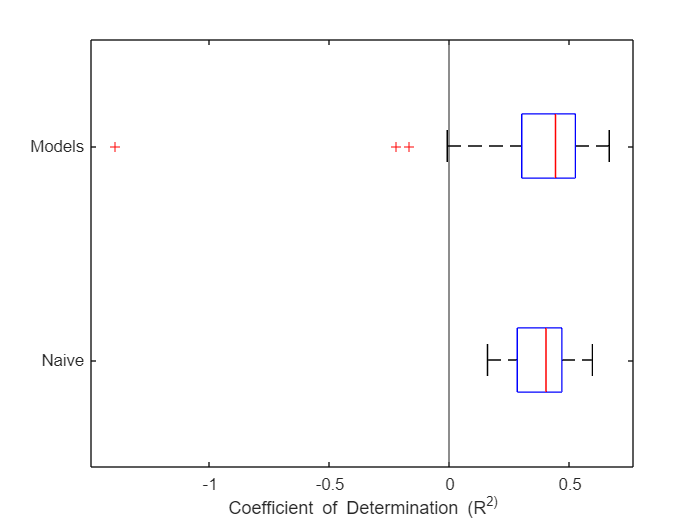

        
        if debugMode
            % Save plots to see what we've done so far
            plotArrays(6, [plotSave_dir, 'Feature Arrays', ...
                filesep, 'Subject ', ...
                num2str(subjectNumber), ' '], ...
                'time', timeVec, 'new', featArray, featNames);

        end

### Create Inputs Using Protocol Timings and Time Vector

        % This function takes the protocol timings and VNS
        % amplitudes and creates inputs according to each
        % protocol condition. These inputs are all the same
        % length as timeVec (i.e., the timings are all aligned)
        % You can decide whether to use binary or non-binary
        % VNS inputs, and if you decide non-binary, you must
        % provide the VNS amplitudes. You can also decide which
        % protocol conditions to create inputs for
        inputArray = create_inputs(timeVec, protTimings, ...
            false, VNSamps, inputOpt);
        
        if debugMode
            if strcmp(inputOpt, 'vtn')
            % Save plots to see what we've done so far
            plotArrays(6, [plotSave_dir, 'Input Arrays', ...
                filesep, 'Subject ', ...
                num2str(subjectNumber), ' '], ...
                'time', timeVec, 'new', inputArray, ...
                {'VNS', 'Trauma', 'Neutral'});
            elseif strcmp(inputOpt, 'vt')
                % Save plots to see what we've done so far
                plotArrays(6, [plotSave_dir, 'Input Arrays', ...
                    filesep, 'Subject ', ...
                    num2str(subjectNumber), ' '], ...
                    'time', timeVec, 'new', inputArray, ...
                    {'VNS', 'Trauma'});
            elseif strcmp(inputOpt, 'vn')
                % Save plots to see what we've done so far
                plotArrays(6, [plotSave_dir, 'Input Arrays', ...
                    filesep, 'Subject ', ...
                    num2str(subjectNumber), ' '], ...
                    'time', timeVec, 'new', inputArray, ...
                    {'VNS', 'Neutral'});
            else
                % Save plots to see what we've done so far
                plotArrays(6, [plotSave_dir, 'Input Arrays', ...
                    filesep, 'Subject ', ...
                    num2str(subjectNumber), ' '], ...
                    'time', timeVec, 'new', inputArray, ...
                    {'VNS'});
            end
        end

### Train-Test Split

NOTES: Based on my inspection of plots on 1/9/2022, subjects 140 and 150 do not have sufficient VNS, trauma,and/or neutral inputs for satisfactory testing

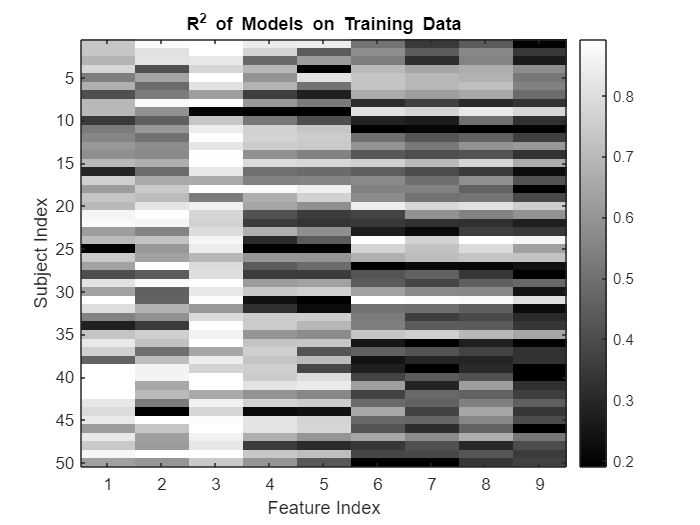

        % This function takes the time vector, the inputs,
        % the features, and the protocol timings and splits
        % the arrays into training and testing arrays according

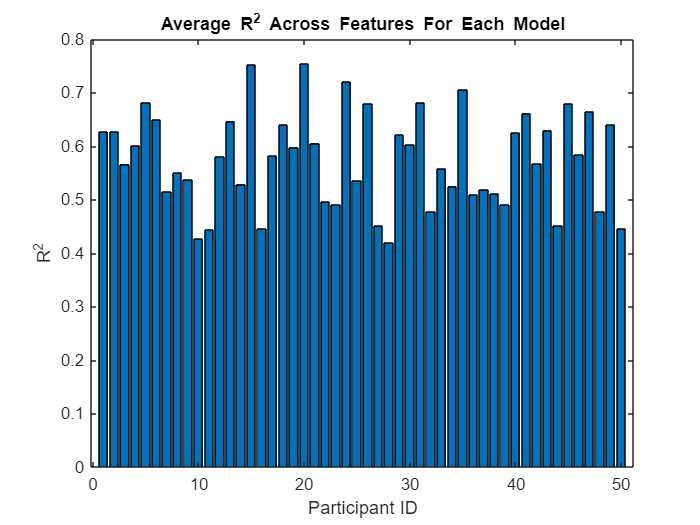

        % to desired train-test split
        [timeTrain, timeTest, ...
            featTrain, featTest, ...
            inputTrain, inputTest] = split_trainTest(...
            timeVec, protTimings, trTest_split, featArray, inputArray);

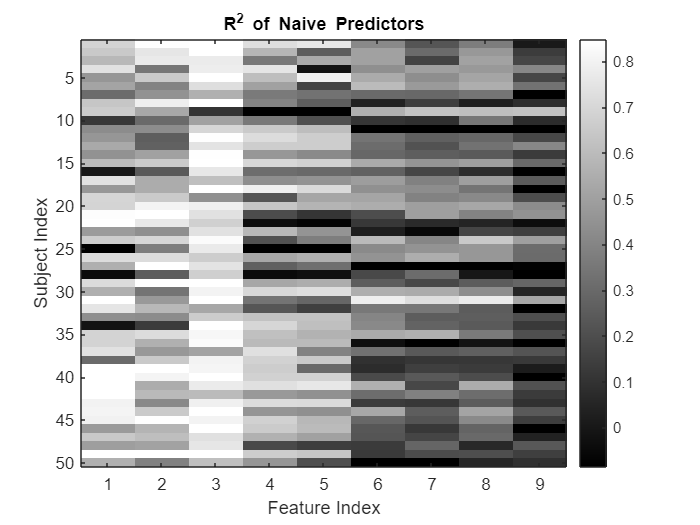

        
        if debugMode
            % Overlay training set of features on top of entire set of
            % features
            plotArrays(6, [plotSave_dir, 'Training Features', ...
                filesep, 'Subject ', ...
                num2str(subjectNumber), ' '], 'overlay', ...
                'timeNew', timeTrain, 'new', featTrain, featNames, ...
                'timeOld', timeVec, 'old', featArray, featNames);

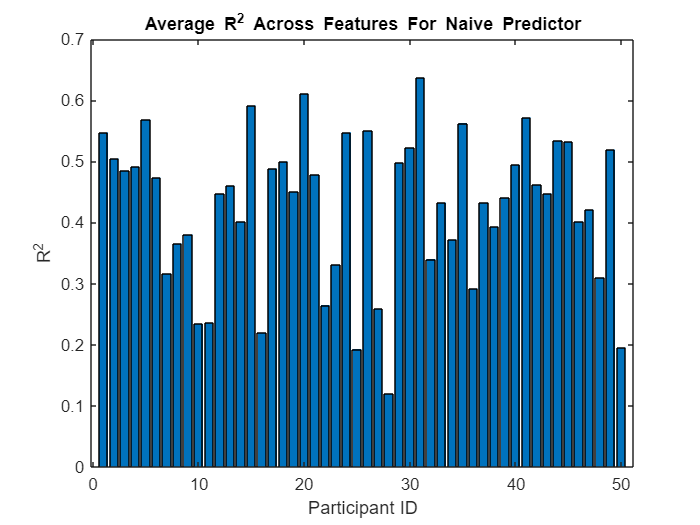

            
            % Overlay testing set of features on top of entire set of
            % features
            plotArrays(6, [plotSave_dir, 'Testing Features', ...
                filesep, 'Subject ', ...

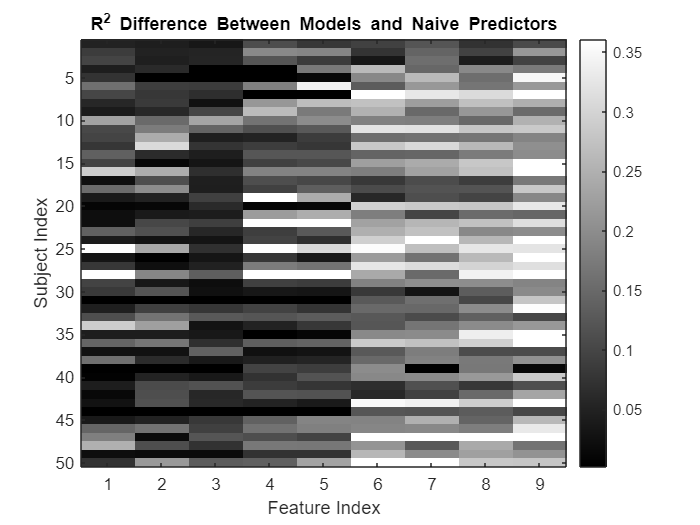

                num2str(subjectNumber), ' '], 'overlay', ...
                'timeNew', timeTest, 'new', featTest, featNames, ...
                'timeOld', timeVec, 'old', featArray, featNames);
            
            
            if strcmp(inputOpt, 'vtn')
                % Overlay training set of inputs on top of entire set of inputs
                plotArrays(6, [plotSave_dir, 'Training Inputs', ...
                    filesep, 'Subject ', ...
                    num2str(subjectNumber), ' '], 'overlay', ...
                    'timeNew', timeTrain, 'new', inputTrain, ...

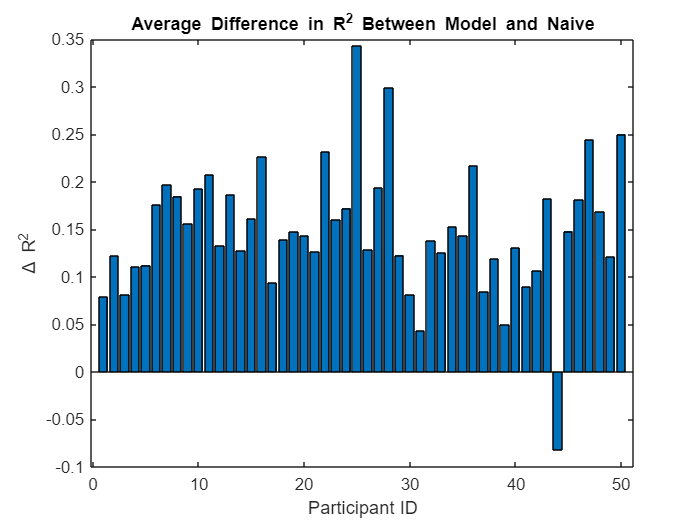

                    {'VNS', 'Trauma', 'Neutral'}, ...
                    'timeOld', timeVec, 'old', inputArray, ...
                    {'VNS', 'Trauma', 'Neutral'});
                
                % Overlay testing set of inputs on top of entire set of inputs

                plotArrays(6, [plotSave_dir, 'Testing Inputs', ...
                    filesep, 'Subject ', ...
                    num2str(subjectNumber), ' '], 'overlay', ...

ans = 0.1490

                    'timeNew', timeTest, 'new', inputTest, ...

ans = 0.1434

                    {'VNS', 'Trauma', 'Neutral'}, ...

ans = 0.5756

                    'timeOld', timeVec, 'old', inputArray, ...

ans = 0.5811

                    {'VNS', 'Trauma', 'Neutral'});
            elseif strcmp(inputOpt, 'vt')
                % Overlay training set of inputs on top of entire set of inputs
                plotArrays(6, [plotSave_dir, 'Training Inputs', ...
                    filesep, 'Subject ', ...
                    num2str(subjectNumber), ' '], 'overlay', ...
                    'timeNew', timeTrain, 'new', inputTrain, ...
                    {'VNS', 'Trauma'}, ...
                    'timeOld', timeVec, 'old', inputArray, ...
                    {'VNS', 'Trauma'});
                
                % Overlay testing set of inputs on top of entire set of inputs
                plotArrays(6, [plotSave_dir, 'Testing Inputs', ...
                    filesep, 'Subject ', ...
                    num2str(subjectNumber), ' '], 'overlay', ...
                    'timeNew', timeTest, 'new', inputTest, ...
                    {'VNS', 'Trauma'}, ...
                    'timeOld', timeVec, 'old', inputArray, ...
                    {'VNS', 'Trauma'});
            elseif strcmp(inputOpt, 'vn')
                % Overlay training set of inputs on top of entire set of inputs
                plotArrays(6, [plotSave_dir, 'Training Inputs', ...
                    filesep, 'Subject ', ...
                    num2str(subjectNumber), ' '], 'overlay', ...
                    'timeNew', timeTrain, 'new', inputTrain, ...
                    {'VNS', 'Neutral'}, ...
                    'timeOld', timeVec, 'old', inputArray, ...
                    {'VNS', 'Neutral'});
                
                % Overlay testing set of inputs on top of entire set of inputs
                plotArrays(6, [plotSave_dir, 'Testing Inputs', ...
                    filesep, 'Subject ', ...
                    num2str(subjectNumber), ' '], 'overlay', ...
                    'timeNew', timeTest, 'new', inputTest, ...
                    {'VNS', 'Neutral'}, ...
                    'timeOld', timeVec, 'old', inputArray, ...
                    {'VNS', 'Neutral'});
            else
                % Overlay training set of inputs on top of entire set of inputs
                plotArrays(6, [plotSave_dir, 'Training Inputs', ...
                    filesep, 'Subject ', ...
                    num2str(subjectNumber), ' '], 'overlay', ...
                    'timeNew', timeTrain, 'new', inputTrain, ...
                    {'VNS'}, ...
                    'timeOld', timeVec, 'old', inputArray, ...
                    {'VNS'});
                
                % Overlay testing set of inputs on top of entire set of inputs
                plotArrays(6, [plotSave_dir, 'Testing Inputs', ...
                    filesep, 'Subject ', ...
                    num2str(subjectNumber), ' '], 'overlay', ...
                    'timeNew', timeTest, 'new', inputTest, ...
                    {'VNS'}, ...
                    'timeOld', timeVec, 'old', inputArray, ...
                    {'VNS'});
            end
        end

### Scale Train and Test Features to $\sigma$ = 1 Based on Train Features?

        % Should I scale all the features to have SD = 1?
        if unitVar_feat
            % Scale testing features first before altering training
            % features
            featTest = featTest./std(featTrain, 0, 1);
            featTrain = featTrain./std(featTrain, 0, 1);
        end

### Optimize Hyperparameters

Here, we optimize over $m$, the model order, $\tau_v$, $\tau_t$, and $\tau_n$, the input delays.

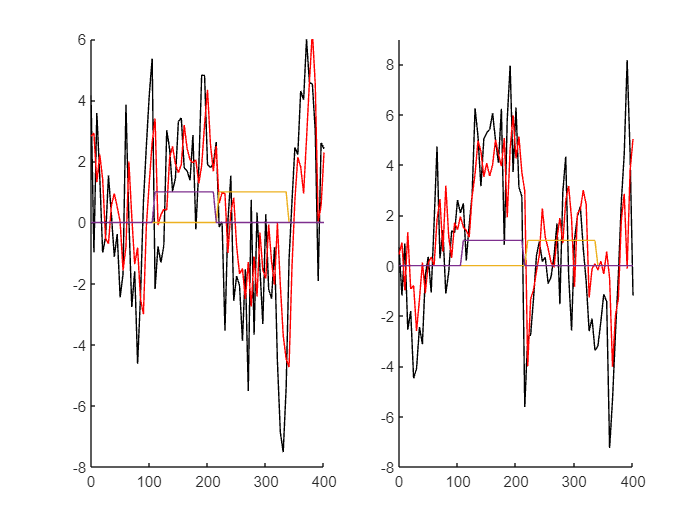

        if strcmp(inputOpt, 'vtn')
            % We use the training data to optimize hyperparameters via AICc
%             [mOrder_star, vnsDelay_star, ...
%                 traumDelay_star, neutrDelay_star] = ...
%                 optimizeHP_LSSM(false, timeTrain, featTrain, modelOrders, ...
%                 inputTrain, inputOpt, ...
%                 vnsDelays, traumaDelays, neutralDelays);
            
            % We use a portion of the training data as validation data
            % to optimize hyperparameters
            [mOrder_star, vnsDelay_star, ...
                traumDelay_star, neutrDelay_star] = ...
                optimizeHP_LSSM(false, timeTrain, featTrain, modelOrders, ...
                inputTrain, inputOpt, ...
                vnsDelays, traumaDelays, neutralDelays, ...
                'validation', 0.3);
            
            % Purposeful data leakage to see best case (sanity check)
%             [mOrder_star, vnsDelay_star, ...
%                 traumDelay_star, neutrDelay_star] = ...

%                 optimizeHP_LSSM(false, timeTrain, featTrain, modelOrders, ...
%                 inputTrain, inputOpt, ...
%                 vnsDelays, traumaDelays, neutralDelays, 'leak_test', ...
%                 timeTest, featTest, inputTest);
        elseif strcmp(inputOpt, 'vt')
            % We use the training data to optimize hyperparameters via AICc
%             [mOrder_star, vnsDelay_star, ...
%                 traumDelay_star] = ...
%                 optimizeHP_LSSM(false, timeTrain, featTrain, modelOrders, ...
%                 inputTrain, inputOpt, ...
%                 vnsDelays, traumaDelays);
            
            % We use a portion of the training data as validation data
            % to optimize hyperparameters
            [mOrder_star, vnsDelay_star, ...
                traumDelay_star] = ...
                optimizeHP_LSSM(false, timeTrain, featTrain, modelOrders, ...
                inputTrain, inputOpt, ...
                vnsDelays, traumaDelays, ...
                'validation', 0.3);
            
            % Purposeful data leakage to see best case (sanity check)
%             [mOrder_star, vnsDelay_star, ...
%                 traumDelay_star] = ...
%                 optimizeHP_LSSM(false, timeTrain, featTrain, modelOrders, ...
%                 inputTrain, inputOpt, ...
%                 vnsDelays, traumaDelays, ...
%                 'leak_test', timeTest, featTest, inputTest);
        elseif strcmp(inputOpt, 'vn')
            % We use the training data to optimize hyperparameters via AICc
%             [mOrder_star, vnsDelay_star, ...
%                 neutrDelay_star] = ...
%                 optimizeHP_LSSM(false, timeTrain, featTrain, modelOrders, ...
%                 inputTrain, inputOpt, ...
%                 vnsDelays, neutralDelays);
            
            % We use a portion of the training data as validation data
            % to optimize hyperparameters
            [mOrder_star, vnsDelay_star, ...
                neutrDelay_star] = ...
                optimizeHP_LSSM(false, timeTrain, featTrain, modelOrders, ...
                inputTrain, inputOpt, ...
                vnsDelays, neutralDelays, ...
                'validation', 0.3);
            
            % Purposeful data leakage to see best case (sanity check)
%             [mOrder_star, vnsDelay_star, ...
%                 neutrDelay_star] = ...
%                 optimizeHP_LSSM(false, timeTrain, featTrain, modelOrders, ...
%                 inputTrain, inputOpt, ...
%                 vnsDelays, neutralDelays, ...
%                 'leak_test', timeTest, featTest, inputTest);
        else
            % We use the training data to optimize hyperparameters via AICc
%             [mOrder_star, vnsDelay_star] = ...
%                 optimizeHP_LSSM(false, timeTrain, featTrain, modelOrders, ...
%                 inputTrain, inputOpt, ...
%                 vnsDelays);
            
            % We use a portion of the training data as validation data
            % to optimize hyperparameters
            [mOrder_star, vnsDelay_star] = ...
                optimizeHP_LSSM(false, timeTrain, featTrain, modelOrders, ...
                inputTrain, inputOpt, ...
                vnsDelays, ...
                'validation', 0.3);
            
            % Purposeful data leakage to see best case (sanity check)
%             [mOrder_star, vnsDelay_star] = ...
%                 optimizeHP_LSSM(false, timeTrain, featTrain, modelOrders, ...
%                 inputTrain, inputOpt, ...
%                 vnsDelays, ...
%                 'leak_test', timeTest, featTest, inputTest);
        end

### Fit the Final Model for This Subject

We fit the final model using $m^* ,\tau_v^{\;*} ,\tau_t^{\;*}$, and $\tau_n^{\;*}$

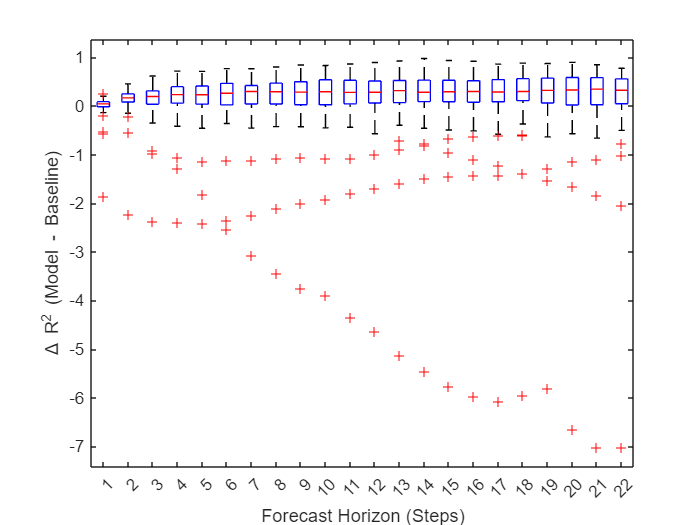

        % Using the optimal hyperparameters, we fit the
        % final model for this subject using the training data
        if strcmp(inputOpt, 'vtn')
            LSSM_final = fit_LSSM(timeTrain, featTrain, mOrder_star, ...
                inputTrain, inputOpt, ...
                vnsDelay_star, traumDelay_star, neutrDelay_star);

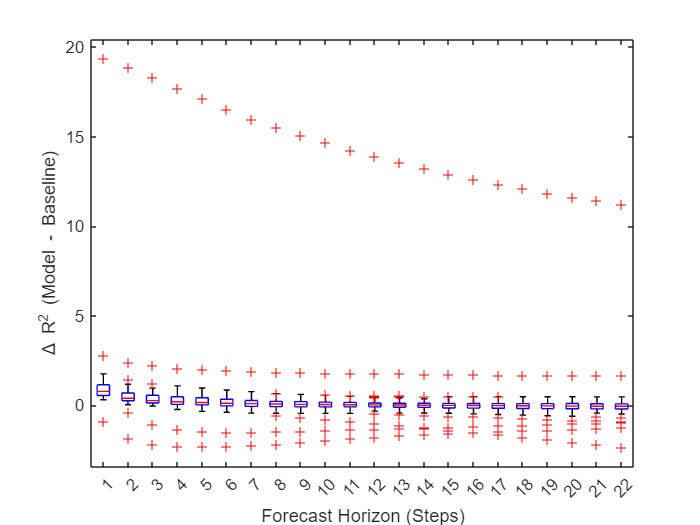

        elseif strcmp(inputOpt, 'vt')
            LSSM_final = fit_LSSM(timeTrain, featTrain, mOrder_star, ...
                inputTrain, inputOpt, ...

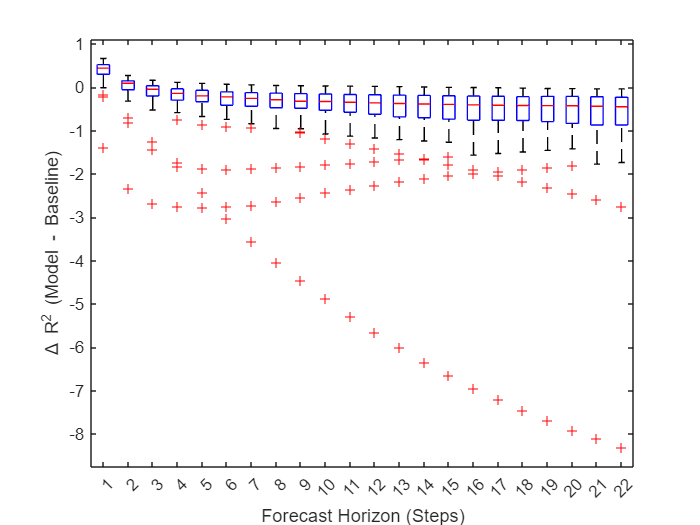

                vnsDelay_star, traumDelay_star);
        elseif strcmp(inputOpt, 'vn')
            LSSM_final = fit_LSSM(timeTrain, featTrain, mOrder_star, ...

                inputTrain, inputOpt, ...
                vnsDelay_star, neutrDelay_star);
        else
            LSSM_final = fit_LSSM(timeTrain, featTrain, mOrder_star, ...
                inputTrain, inputOpt, ...
                vnsDelay_star);
        end
        

### Save Model and End the Parallel Model Fitting

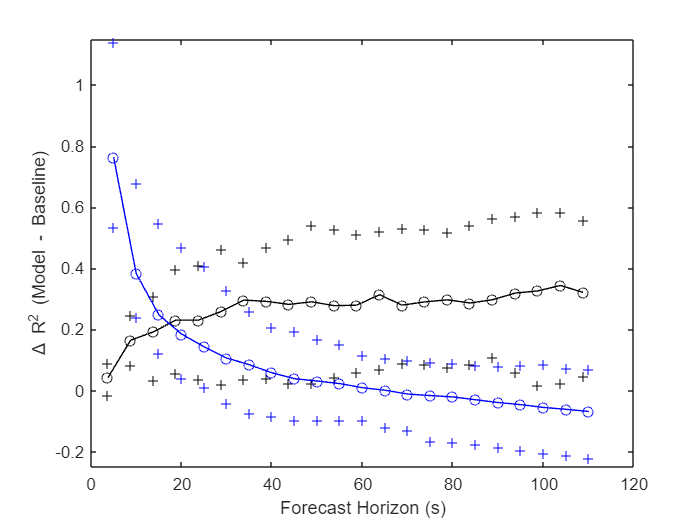

        % Save the final model and any additional
        % variables necessary for further analysis
        saveFileName = [modelSave_dir, 'S', num2str(subjectNumber), ...
            '_LSSM_2024_03.mat'];
        
        % Workaround necessary due to parfor loop
        save_struct = struct();     % Initialize struct
        % Specify variables to save
        save_struct.featNames = featNames;
        save_struct.resamp_Fs = resamp_Fs;
        save_struct.trTest_split = trTest_split;
        save_struct.subjectNumber = subjectNumber;
        save_struct.timeTrain = timeTrain;
        save_struct.timeTest = timeTest;
        save_struct.featTrain = featTrain;
        save_struct.featTest = featTest;
        save_struct.inputTrain = inputTrain;
        save_struct.inputTest = inputTest;
        save_struct.LSSM_final = LSSM_final;
        save_struct.inputOpt = inputOpt;

        
        % Save
        parsave(saveFileName, save_struct)
        
        % Output progress to user
        timeNow = datetime('now','TimeZone','local',...
            'Format','d-MMM-y HH:mm:ss Z');
        disp(['Done with subject ', num2str(subjectNumber), ...
            ' at ', datestr(timeNow)])
    end
end

## Model Analysis

Load all subjects' models for all subsequent analysis

% Initialize cell array to hold all subjects' models
LSSM_allSubj = cell(length(subjects_all), 1);

% Loop through subjects
for sub = 1:length(subjects_all)
    % Store subject number
    subjectNumber = subjects_all(sub);
    
    % Filename of .mat file that stores subject's model
    loadFileName = [modelSave_dir, 'S', num2str(subjectNumber), ...
        '_LSSM_2024_03.mat'];
    
    % Load and store away
    loadStruct = load(loadFileName, 'LSSM_final', 'featNames');
    LSSM_allSubj{sub} = loadStruct.LSSM_final;
    
    % Just keep storing away until the end so I can subsequently use
    featNames = loadStruct.featNames;
end

### Evaluate Model Fit on Test Data

Initialize arrays to store K-step ahead $R^2$ for models and baseline predictors

% Steps ahead the model will try to predict
K_steps = 1;

% Columns will be for features, and rows will be for subjects
% (i.e., for each subject and for each feature, we will get one R^2)
R2_model = zeros(length(subjects_all), numel(featNames));
R2_naive = zeros(length(subjects_all), numel(featNames));


R2_mean = zeros(length(subjects_all), numel(featNames));

Loop through subjects

% Loop through subjects
for sub = 1:length(subjects_all)
    % Store subject number
    subjectNumber = subjects_all(sub);

Load test data (and train data in case I use for initial conditions)

    % Filename of .mat file that stores subject's model
    loadFileName = [modelSave_dir, 'S', num2str(subjectNumber), ...
        '_LSSM_2024_03.mat'];
    
    % Load and store away
    loadStruct = load(loadFileName, 'featTest', 'inputTest', 'timeTest', ...
        'featTrain', 'inputTrain', 'timeTrain');
    yTest = loadStruct.featTest; yTrain = loadStruct.featTrain; % output
    uTest = loadStruct.inputTest; uTrain = loadStruct.inputTrain; % input
    tTest = loadStruct.timeTest; tTrain = loadStruct.timeTrain; % discrete time

Initial conditions for models

    % Set the initial conditions for prediction based on end of training data
    IC_training = struct('Input', uTrain, 'Output', yTrain);
    predictOpt = predictOptions('InitialCondition', IC_training);

Perform K-step ahead predictions for this participant's model

    % Store away K-step ahead predicted feature values on test set
    [y_hat, ic, ~] = predict(LSSM_allSubj{sub}, iddata(yTest, uTest, ...
        tTest(2) - tTest(1)), K_steps, predictOpt);

For each feature, indexed by $i$, we can compute ${R_i }^2 =1-\frac{\;\left|\right|y_i -\hat{\;y_i } \left|{\left|\right.}_2^2 \right.}{\left|\right|y_i -\bar{\;y_i } \left|{\left|\right.}_2^2 \right.}$, where $y_i$ is defined here, to abuse notation, as $y_i ={\left\lbrack y_{i_1 } ,y_{i_2 } ,\ldotp \ldotp \ldotp ,y_{i_L } \right\rbrack }^T$, where $L$ is the length of the test data, $\hat{\;y_i }$ holds the predicted values over all $L$, and $\bar{\;y_i }$ stores a vector of $\frac{1}{L}\sum_{k\;=\;1}^L y_{i_k }$ repeated $L$ times (the output of a mean predictor).

    % Compute R^2 for each feature for this subject
    R2_model(sub, :) = Rsquared(yTest(1:end, :), y_hat.OutputData(1:end, :));

Evaluate baseline models on test data and store $R^2$. Note that mean predictor, by definition, has $R^2$ of 0, so only need to evaluate naive predictor

    y_naive = naivePred(yTest, 'steps', K_steps, 'initialEst', ...
        yTrain(end-K_steps+1, :));  % Initial conditions based on final training points
    
    R2_naive(sub, :) = Rsquared(yTest(1:end, :), y_naive(1:end, :));

    
    % Compute R2 using the training data's mean as a constant prediction
    % for the length of the testing data
    % (arguably more legitimate "mean predictor")
    R2_mean(sub, :) = Rsquared(yTest(1:end, :), ...
        repmat(mean(yTrain, 1), [size(yTest, 1), 1]));
end

Inspect $R^2$ to evaluate model quality

% Model
imagesc(R2_model)
title('R^2 of Models')
xlabel('Feature Index')
ylabel('Subject Index')
caxis([prctile(R2_model, 5, 'all'), prctile(R2_model, 95, 'all')])
colormap gray
colorbar

bar(mean(R2_model, 2))
xlabel('Participant ID')
ylabel('R^2')
title('Average R^2 Across Features For Each Model')
% Naive
imagesc(R2_naive)
title('R^2 of Naive Predictors')
xlabel('Feature Index')
ylabel('Subject Index')
caxis([prctile(R2_naive, 5, 'all'), prctile(R2_naive, 95, 'all')])
colormap gray
colorbar

bar(mean(R2_naive, 2))
xlabel('Participant ID')
ylabel('R^2')
title('Average R^2 Across Features For Naive Predictor')

% Here, I need to compare model R^2 vs. naive and mean predictor R^2
R2_residual = R2_model - R2_naive;

bar(mean(R2_residual, 2))
xlabel('Participant ID')
ylabel('\Delta R^2')
title('Average Difference in R^2 Between Model and Naive')
imagesc(R2_residual)
title('R^2 Difference Between Models and Naive Predictors')
xlabel('Feature Index')
ylabel('Subject Index')
caxis([prctile(R2_residual, 5, 'all'), prctile(R2_residual, 95, 'all')])
colormap gray
colorbar
% Quantitative Comparisons
mean(mean(R2_model, 2) - mean(R2_naive, 2)) % Comparison w/ naive
median(mean(R2_model, 2) - mean(R2_naive, 2))   % Comparison w/ naive
mean(mean(R2_model, 2)) % Comparison w/ mean
median(mean(R2_model, 2))   % Comparison w/ mean
mean(mean(R2_model, 2) - mean(R2_mean, 2)) % Comparison with training mean predictor

median(mean(R2_model, 2) - mean(R2_mean, 2)) % Comparison with training mean predictor


% Box and whisker plots
boxplot([mean(R2_naive, 2), mean(R2_model, 2)], 'orientation', 'horizontal')
yticklabels({'Naive', 'Models'})
xlabel('Coefficient of Determination (R^2)')
xline(0)

### Check for Underfitting by Evaluating Models on Training Data

% Columns will be for features, and rows will be for subjects
% (i.e., for each subject and for each feature, we will get one R^2)
R2_model_train = zeros(length(subjects_all), numel(featNames));
R2_naive_train = zeros(length(subjects_all), numel(featNames));

% Loop through subjects
for sub = 1:length(subjects_all)
    % Store subject number
    subjectNumber = subjects_all(sub);
    
    % Filename of .mat file that stores subject's model
    loadFileName = [modelSave_dir, 'S', num2str(subjectNumber), ...
        '_prelim_LSSM_2021_12.mat'];
    
    % Load and store away
    loadStruct = load(loadFileName, 'featTrain', 'inputTrain', 'timeTrain');
    yTrain = loadStruct.featTrain; % output
    uTrain = loadStruct.inputTrain; % input
    tTrain = loadStruct.timeTrain; % discrete time
    
    % Default
    predictOpt = predictOptions('InitialCondition', 'z');
    
    % Store away 1-step ahead predicted feature values on training data
    [y_hat_train, ic, ~] = predict(LSSM_allSubj{sub}, iddata(yTrain, uTrain, ...
        tTrain(2) - tTrain(1)), K_steps, predictOpt);
    
    % Compute R^2 for each feature for this subject
    R2_model_train(sub, :) = Rsquared(yTrain(1:end, :), y_hat_train.OutputData(1:end, :));

Evaluate baseline models on test data and store $R^2$. Note that mean predictor, by definition, has $R^2$ of 0, so only need to evaluate naive predictor

    y_naive_train = naivePred(yTrain, 'steps', K_steps);
    
    R2_naive_train(sub, :) = Rsquared(yTrain(1:end, :), y_naive_train(1:end, :));
end


Inspect $R^2$

% Model
imagesc(R2_model_train)
title('R^2 of Models on Training Data')
xlabel('Feature Index')
ylabel('Subject Index')
caxis([prctile(R2_model_train, 5, 'all'), prctile(R2_model_train, 95, 'all')])
colormap gray
colorbar

bar(mean(R2_model_train, 2))
xlabel('Participant ID')
ylabel('R^2')
title('Average R^2 Across Features For Each Model')

% Naive
imagesc(R2_naive_train)
title('R^2 of Naive Predictors')
xlabel('Feature Index')
ylabel('Subject Index')
caxis([prctile(R2_naive_train, 5, 'all'), prctile(R2_naive_train, 95, 'all')])
colormap gray
colorbar

bar(mean(R2_naive_train, 2))
xlabel('Participant ID')
ylabel('R^2')
title('Average R^2 Across Features For Naive Predictor')

% Here, I need to compare model R^2 vs. naive and mean predictor R^2
R2_residual_train = R2_model_train - R2_naive_train;

imagesc(R2_residual_train)
title('R^2 Difference Between Models and Naive Predictors')
xlabel('Feature Index')
ylabel('Subject Index')
caxis([prctile(R2_residual_train, 5, 'all'), prctile(R2_residual_train, 95, 'all')])
colormap gray
colorbar

bar(mean(R2_residual_train, 2))
xlabel('Participant ID')
ylabel('\Delta R^2')
title('Average Difference in R^2 Between Model and Naive')

% Quantitative Comparisons
mean(mean(R2_model_train, 2) - mean(R2_naive_train, 2)) % Comparison w/ naive
median(mean(R2_model_train, 2) - mean(R2_naive_train, 2))   % Comparison w/ naive
mean(mean(R2_model_train, 2)) % Comparison w/ zero predictor
median(mean(R2_model_train, 2))   % Comparison w/ zero predictor

#### Save away model fitting performances

% Filename
% If we're loading from somewhere separate, we don't want to overwrite
if fitModels
    saveFileName = [modelSave_dir, 'fitPerformances.mat'];
else
    saveFileName = ['..', filesep, '..', filesep, ...
        'Saved Models', filesep, 'LSSM_2024_03', filesep, ...
        'fitPerformances.mat'];
end

% Save away fit performances and variables necessary
% to interpret performances arrays
save(saveFileName, 'subjects_all', 'featNames', ...
    'R2_model', 'R2_mean', 'R2_naive', 'R2_model_train', 'R2_naive_train');

#### Example Testing Data and Model Predictions

As of 3/17/2024, I am going with subject 115, who had PTSD and received active stimulation

This choice was made because they are the first active PTSD subject with better than naive predicitons (114 did not have better than naive).

sub = 12;   % Index of 115

% Load data
subjectNumber = subjects_all(sub);
loadFileName = [modelSave_dir, 'S', num2str(subjectNumber), ...
'_prelim_LSSM_2021_12.mat'];
loadStruct = load(loadFileName, 'featTest', 'inputTest', 'timeTest', ...
'featTrain', 'inputTrain', 'timeTrain');

% Store data into appropriate variables
yTest = loadStruct.featTest; yTrain = loadStruct.featTrain; % output
uTest = loadStruct.inputTest; uTrain = loadStruct.inputTrain; % input
tTest = loadStruct.timeTest; tTrain = loadStruct.timeTrain; % discrete time

% Set the initial conditions for the test data pred. based on training data
IC_training = struct('Input', uTrain, 'Output', yTrain);
predictOpt = predictOptions('InitialCondition', IC_training);

% Compute Kalman 1-step predictions
[y_hat, ic, ~] = predict(LSSM_allSubj{sub}, iddata(yTest, uTest, ...
tTest(2) - tTest(1)), 1, predictOpt);


Now, we plot

115's heart rate and respiration rate data are especially interesting for their very last trauma recall and VNS administration

% Ballpark
tStart = 6552;
tEnd = 6952; 

% Exact so we can easily index and plot desired data
tStart_idx = find(abs(tTest - tStart) < 1); tStart = tTest(tStart_idx); 
tEnd_idx = find(abs(tTest - tEnd) < 1); tEnd = tTest(tEnd_idx);

% Let's create 1x2 subplot grid for HR and RR data
HR_idx = 1;
RR_idx = 6;
VNS_idx = 1;
traum_idx = 2;

figure()
subplot(1, 2, 1) % HR
hold on
% Data
plot(tTest(tStart_idx:tEnd_idx) - tStart, yTest(tStart_idx:tEnd_idx, HR_idx), 'k') % Real
plot(tTest(tStart_idx:tEnd_idx) - tStart, y_hat.OutputData(tStart_idx:tEnd_idx, HR_idx), 'r') % Predicted

% For timings
plot(tTest(tStart_idx:tEnd_idx) - tStart, uTest(tStart_idx:tEnd_idx, VNS_idx)) % VNS input
plot(tTest(tStart_idx:tEnd_idx) - tStart, uTest(tStart_idx:tEnd_idx, traum_idx)) % Trauma input

ylim([-8, 6]) % to get the most of my space
hold off

subplot(1, 2, 2) % RR
hold on
plot(tTest(tStart_idx:tEnd_idx) - tStart, yTest(tStart_idx:tEnd_idx, RR_idx), 'k') % Real
plot(tTest(tStart_idx:tEnd_idx) - tStart, y_hat.OutputData(tStart_idx:tEnd_idx, RR_idx), 'r') % Predicted

% For timings
plot(tTest(tStart_idx:tEnd_idx) - tStart, uTest(tStart_idx:tEnd_idx, VNS_idx)) % VNS input
plot(tTest(tStart_idx:tEnd_idx) - tStart, uTest(tStart_idx:tEnd_idx, traum_idx)) % Trauma input

ylim([-8, 9]) % to get the most of my space
hold off

% Let's link their x-axes
linkaxes([subplot(1, 2, 1), subplot(1, 2, 2)], 'x');

#### Forecasting Comparison Against Baselines

We will evaluate the forecasting performance of the models and baselines and plot the differences against forecast horizon

% To do this, we need to take the models, the training data, and the
% testing data for each subject, compute the R2 values for the models and
% the baselines, store them away, and then iterate across subjects. Then,
% we need to repeat this for every forecast horizon we want to test and
% then store the final results in an array for subsequent analysis

% Forecast horizons to try
% Stopping at 22 because that is where training mean predictor defeats
% models (statistically significantly using signed rank test)
forecastHorizons = 1:22; 

% Initialize arrays to store results
R2_model = zeros(length(subjects_all), length(forecastHorizons));
R2_naive = zeros(length(subjects_all), length(forecastHorizons));
R2_trainMean = zeros(length(subjects_all), length(forecastHorizons));

% Start the looping process
% (subjects is outer loop to minimize number of times data loaded)
for sub = 1:length(subjects_all)
    % Store subject number
    subjectNumber = subjects_all(sub);

    % Filename of .mat file that stores subject's model
    loadFileName = [modelSave_dir, 'S', num2str(subjectNumber), ...
        '_prelim_LSSM_2021_12.mat'];

    % Load and store away
    loadStruct = load(loadFileName, 'featTest', 'inputTest', 'timeTest', ...
        'featTrain', 'inputTrain', 'timeTrain');
    yTest = loadStruct.featTest; yTrain = loadStruct.featTrain; % output
    uTest = loadStruct.inputTest; uTrain = loadStruct.inputTrain; % input
    tTest = loadStruct.timeTest; tTrain = loadStruct.timeTrain; % discrete time
    
    % Loop through horizons
    for horiz = forecastHorizons

Compute the performances for model (averaging R2 across features)

        % Set the initial conditions for prediction based on end of training data
        IC_training = struct('Input', uTrain, 'Output', yTrain);
        predictOpt = predictOptions('InitialCondition', IC_training);

        % Store away K-step ahead predicted feature values on test set
        [y_hat, ic, ~] = predict(LSSM_allSubj{sub}, iddata(yTest, uTest, ...
            tTest(2) - tTest(1)), horiz, predictOpt);

        % Compute R^2 for each feature for this subject
        R2_model_subSpec = Rsquared(yTest, y_hat.OutputData);

        % Store away average R2 across features for the model's R2
        R2_model(sub, horiz - forecastHorizons(1) + 1) = ...
            mean(R2_model_subSpec);

Compute the performances for naive

        y_naive = naivePred(yTest, 'steps', horiz, 'initialEst', ...
            yTrain(end-horiz+1, :));  % Initial conditions based on final training points

        R2_naive_subSpec = Rsquared(yTest, y_naive);

        R2_naive(sub, horiz - forecastHorizons(1) + 1) = ...
            mean(R2_naive_subSpec);    

Compute the performance for training mean predictor

        % Compute R2 using the training data's mean as a constant prediction
        % for the length of the testing data
        R2_mean_subSpec = Rsquared(yTest, ...
            repmat(mean(yTrain, 1), [size(yTest, 1), 1]));

        R2_trainMean(sub, horiz - forecastHorizons(1) + 1) = ...
            mean(R2_mean_subSpec);
    end
end

Compute the desired deltas

deltaR2_naive = R2_model - R2_naive;
deltaR2_trainMean = R2_model - R2_trainMean;
deltaR2_testMean = R2_model;        % R2_testMean would just be zeros by def. of R2

Plot

boxplot(deltaR2_naive)
ylabel('\Delta R^2 (Model - Baseline)')
xlabel('Forecast Horizon (Steps)')
boxplot(deltaR2_trainMean)
ylabel('\Delta R^2 (Model - Baseline)')
xlabel('Forecast Horizon (Steps)')
boxplot(deltaR2_testMean)
ylabel('\Delta R^2 (Model - Baseline)')
xlabel('Forecast Horizon (Steps)')
% I just want to plot the 25th, 50th, and 75th percentiles for the naive
% and training mean comparisons, overlaid on the same plot
% Compute the desired percentiles
deltaR2_naive_25 = prctile(deltaR2_naive, 25, 1);
deltaR2_naive_50 = prctile(deltaR2_naive, 50, 1);
deltaR2_naive_75 = prctile(deltaR2_naive, 75, 1);

deltaR2_trainMean_25 = prctile(deltaR2_trainMean, 25, 1);
deltaR2_trainMean_50 = prctile(deltaR2_trainMean, 50, 1);
deltaR2_trainMean_75 = prctile(deltaR2_trainMean, 75, 1);

% Each should now be a row vector that I can plot
% (arbitrarily use last tTest we loaded)
xOff = 0.25;
plot((tTest(2) - tTest(1))*(forecastHorizons - xOff), deltaR2_naive_25, 'k+', ...
    'LineStyle','none')
hold on
plot((tTest(2) - tTest(1))*(forecastHorizons - xOff), deltaR2_naive_50, 'k-o')
plot((tTest(2) - tTest(1))*(forecastHorizons - xOff), deltaR2_naive_75, 'k+')

plot((tTest(2) - tTest(1))*forecastHorizons, deltaR2_trainMean_25, 'b+')
plot((tTest(2) - tTest(1))*forecastHorizons, deltaR2_trainMean_50, 'b-o')
plot((tTest(2) - tTest(1))*forecastHorizons, deltaR2_trainMean_75, 'b+')

ylabel('\Delta R^2 (Model - Baseline)')
xlabel('Forecast Horizon (s)')
ylim([-0.25, 1.15])
hold off

### Analyze the products of $C$ and $b_v$, $b_t$, and $b_n$ (or subset used based on input option)

In this section of code, we will compare the products of the "state-to-output" (C parameters) and "input-to-state" parameters fit for each of the protocol conditions treated as input: VNS/sham (v), traumatic stress (t), and neutral scripts (n).

Store away C and B parameters of all subjects' models

bParams_allSubj = cell(length(subjects_all), 1);
cParams_allSubj = cell(length(subjects_all), 1);

% Loop through subjects
for sub = 1:length(subjects_all)
    % Store each subject's set of B and C parameters,
    bParams_allSubj{sub} = LSSM_allSubj{sub}.B;
    cParams_allSubj{sub} = LSSM_allSubj{sub}.C;
end


Store away group-specific parameters for later code

% Initialize cell arrays for all the possible groupings
bParams_PTSD = {}; bParams_nonP = {};
bParams_active = {}; bParams_sham = {};
bParams_PTSDactive = {}; bParams_PTSDsham = {};
bParams_nonPactive = {}; bParams_nonPsham = {};

cParams_PTSD = {}; cParams_nonP = {};
cParams_active = {}; cParams_sham = {};
cParams_PTSDactive = {}; cParams_PTSDsham = {};
cParams_nonPactive = {}; cParams_nonPsham = {};

subNums_PTSD = []; subNums_nonP = [];
subNums_active = []; subNums_sham = [];
subNums_PTSDactive = []; subNums_PTSDsham = [];
subNums_nonPactive = []; subNums_nonPsham = [];

% Rescale (if needed) and concatenate for all the possible groupings
for sub = 1:length(subjects_all)
    % Store subject number
    subjectNumber = subjects_all(sub);
    
    % ---------- Rescaling C Parameters (if needed) ----------- %
    % Rescale C parameters as if features were unit variance
    % (this makes the values of C*b comparable across all features, in case
    % models were fit on train data that were not unit variance)
    % Filename of .mat file that stores subject's processed data
    dataFileName = [modelSave_dir, 'S', num2str(subjectNumber), ...
        '_LSSM_2024_03.mat'];
    
    % Load training data features
    loadStruct = load(dataFileName, 'featTest', 'featTrain');
    yTrain = loadStruct.featTrain; % output
    
    % Rescale
    for feat_idx = 1:size(yTrain, 2)
        cParams_allSubj{sub}(feat_idx, :) = ...
            (1/std(yTrain(:, feat_idx)))*...
            cParams_allSubj{sub}(feat_idx, :);
    end
    % --------------------------------------------------------- %
    
    % Classify subject and concatenate accordingly
    if any(ismember(active_PTSD_all, subjectNumber))
        bParams_PTSDactive = [bParams_PTSDactive; bParams_allSubj{sub}];
        cParams_PTSDactive = [cParams_PTSDactive; cParams_allSubj{sub}];
        subNums_PTSDactive = [subNums_PTSDactive; subjectNumber];
    elseif any(ismember(sham_PTSD_all, subjectNumber))
        bParams_PTSDsham = [bParams_PTSDsham; bParams_allSubj{sub}];
        cParams_PTSDsham = [cParams_PTSDsham; cParams_allSubj{sub}];
        subNums_PTSDsham = [subNums_PTSDsham; subjectNumber];
    elseif any(ismember(active_nonP_all, subjectNumber))
        bParams_nonPactive = [bParams_nonPactive; bParams_allSubj{sub}];
        cParams_nonPactive = [cParams_nonPactive; cParams_allSubj{sub}];
        subNums_nonPactive = [subNums_nonPactive; subjectNumber];
    else
        bParams_nonPsham = [bParams_nonPsham; bParams_allSubj{sub}];
        cParams_nonPsham = [cParams_nonPsham; cParams_allSubj{sub}];
        subNums_nonPsham = [subNums_nonPsham; subjectNumber];
    end
end

% Create final overarching sets
bParams_PTSD = [bParams_PTSDactive; bParams_PTSDsham]; 
bParams_nonP = [bParams_nonPactive; bParams_nonPsham];
bParams_active = [bParams_nonPactive; bParams_PTSDactive]; 
bParams_sham = [bParams_nonPsham; bParams_PTSDsham];

cParams_PTSD = [cParams_PTSDactive; cParams_PTSDsham]; 
cParams_nonP = [cParams_nonPactive; cParams_nonPsham];
cParams_active = [cParams_nonPactive; cParams_PTSDactive]; 
cParams_sham = [cParams_nonPsham; cParams_PTSDsham];

subNums_PTSD = [subNums_PTSDactive; subNums_PTSDsham]; 
subNums_nonP = [subNums_nonPactive; subNums_nonPsham];
subNums_active = [subNums_nonPactive; subNums_PTSDactive]; 
subNums_sham = [subNums_nonPsham; subNums_PTSDsham];

#### Compare the C*B values themselves

**Subject-Specific**

for sub = 1:length(subjects_all)
    % Store subject number for plot labeling
    subjectNumber = subjects_all(sub);
    
    % Rank based on absolute value separately
    barPlot_CBproducts(num2str(subjectNumber), ...
        [plotSave_dir, 'SubjectSpecific_CBproducts', ...
        filesep, 'BarPlots', filesep, 'Subject ', ...
        num2str(subjectNumber)], cParams_allSubj{sub}, featNames, ...
        'vtn', bParams_allSubj{sub});
end

**Group-Specific**

All subjects

Because I am statistically testing for paper, I ask for CBproducts as output

CBproducts_all = barPlot_CBproducts('All Subjects', [plotSave_dir, 'GroupSpecific_CBproducts', ...
    filesep, 'BarPlots', filesep, 'All Subjects'], cParams_allSubj, featNames, 'vtn', ...
    bParams_allSubj);

All PTSD

barPlot_CBproducts('All PTSD', [plotSave_dir, 'GroupSpecific_CBproducts', ...
    filesep, 'BarPlots', filesep, 'All PTSD'], cParams_PTSD, featNames, 'vtn', ...
    bParams_PTSD);

All Non-PTSD

barPlot_CBproducts('All Non-PTSD', [plotSave_dir, 'GroupSpecific_CBproducts', ...
    filesep, 'BarPlots', filesep, 'All Non-PTSD'], cParams_nonP, featNames, 'vtn', ...
    bParams_nonP);

All Active

barPlot_CBproducts('All Active', [plotSave_dir, 'GroupSpecific_CBproducts', ...
    filesep, 'BarPlots', filesep, 'All Active'], cParams_active, featNames, 'vtn', ...
    bParams_active);

All Sham

barPlot_CBproducts('All Sham', [plotSave_dir, 'GroupSpecific_CBproducts', ...
    filesep, 'BarPlots', filesep, 'All Sham'], cParams_sham, featNames, 'vtn', ...
    bParams_sham);

Non-PTSD Active

barPlot_CBproducts('Non-PTSD Active', [plotSave_dir, 'GroupSpecific_CBproducts', ...
    filesep, 'BarPlots', filesep, 'Non-PTSD Active'], cParams_nonPactive, featNames, 'vtn', ...
    bParams_nonPactive);

Non-PTSD Sham

barPlot_CBproducts('Non-PTSD Sham', [plotSave_dir, 'GroupSpecific_CBproducts', ...
    filesep, 'BarPlots', filesep, 'Non-PTSD Sham'], cParams_nonPsham, featNames, 'vtn', ...
    bParams_nonPsham);

PTSD Active

barPlot_CBproducts('PTSD Active', [plotSave_dir, 'GroupSpecific_CBproducts', ...
    filesep, 'BarPlots', filesep, 'PTSD Active'], cParams_PTSDactive, featNames, 'vtn', ...
    bParams_PTSDactive);

PTSD Sham

barPlot_CBproducts('PTSD Sham', [plotSave_dir, 'GroupSpecific_CBproducts', ...
    filesep, 'BarPlots', filesep, 'PTSD Sham'], cParams_PTSDsham, featNames, 'vtn', ...
    bParams_PTSDsham);

#### Compare the C*B norms

**Subject-Specific**

for sub = 1:length(subjects_all)
    % Store subject number for plot labeling
    subjectNumber = subjects_all(sub);
    
    % Rank based on absolute value separately
    norm_CBproducts(num2str(subjectNumber), ...
        [plotSave_dir, 'SubjectSpecific_CBproducts', ...
        filesep, 'Norms', filesep, 'Subject ', ...
        num2str(subjectNumber)], cParams_allSubj{sub}, ...
        'vtn', bParams_allSubj{sub});
end

**Group-Specific**

All subjects

norm_CBproducts('All Subjects', [plotSave_dir, 'GroupSpecific_CBproducts', ...
    filesep, 'Norms', filesep, 'All Subjects'], cParams_allSubj, 'vtn', ...
    bParams_allSubj);

All PTSD

norm_CBproducts('All PTSD', [plotSave_dir, 'GroupSpecific_CBproducts', ...
    filesep, 'Norms', filesep, 'All PTSD'], cParams_PTSD, 'vtn', ...
    bParams_PTSD);

All Non-PTSD

norm_CBproducts('All Non-PTSD', [plotSave_dir, 'GroupSpecific_CBproducts', ...
    filesep, 'Norms', filesep, 'All Non-PTSD'], cParams_nonP, 'vtn', ...
    bParams_nonP);

All Active

norm_CBproducts('All Active', [plotSave_dir, 'GroupSpecific_CBproducts', ...
    filesep, 'Norms', filesep, 'All Active'], cParams_active, 'vtn', ...
    bParams_active);

All Sham

norm_CBproducts('All Sham', [plotSave_dir, 'GroupSpecific_CBproducts', ...
    filesep, 'Norms', filesep, 'All Sham'], cParams_sham, 'vtn', ...
    bParams_sham);

Non-PTSD Active

norm_CBproducts('Non-PTSD Active', [plotSave_dir, 'GroupSpecific_CBproducts', ...
    filesep, 'Norms', filesep, 'Non-PTSD Active'], cParams_nonPactive, 'vtn', ...
    bParams_nonPactive);

Non-PTSD Sham

norm_CBproducts('Non-PTSD Sham', [plotSave_dir, 'GroupSpecific_CBproducts', ...
    filesep, 'Norms', filesep, 'Non-PTSD Sham'], cParams_nonPsham, 'vtn', ...
    bParams_nonPsham);

PTSD Active

norm_CBproducts('PTSD Active', [plotSave_dir, 'GroupSpecific_CBproducts', ...
    filesep, 'Norms', filesep, 'PTSD Active'], cParams_PTSDactive, 'vtn', ...
    bParams_PTSDactive);

PTSD Sham

norm_CBproducts('PTSD Sham', [plotSave_dir, 'GroupSpecific_CBproducts', ...
    filesep, 'Norms', filesep, 'PTSD Sham'], cParams_PTSDsham, 'vtn', ...
    bParams_PTSDsham);

#### Compare the Pairwise Angles Between C*b Terms

**Subject-Specific**

for sub = 1:length(subjects_all)
    % Store subject number for plot labeling
    subjectNumber = subjects_all(sub);
    
    % Rank based on absolute value separately
    angle_CBproducts(num2str(subjectNumber), ...
        [plotSave_dir, 'SubjectSpecific_CBproducts', ...
        filesep, 'Angles', filesep, 'Subject ', ...
        num2str(subjectNumber)], cParams_allSubj{sub}, ...
        'vtn', bParams_allSubj{sub});
    
%     % Check to make sure angles are properly computed in 2-D
%     angle_CBproducts_debug(num2str(subjectNumber), ...
%         [plotSave_dir, 'SubjectSpecific_CBproducts', ...
%         filesep, 'Angles', filesep, 'Subject ', ...
%         num2str(subjectNumber), '_debug'], cParams_allSubj{sub}, ...
%         'vtn', bParams_allSubj{sub}, ...
%         'elementNums', [1, 6]);
end

**Group-Specific**

All subjects

angle_CBproducts('All Subjects', [plotSave_dir, 'GroupSpecific_CBproducts', ...
    filesep, 'Angles', filesep, 'All Subjects'], cParams_allSubj, 'vtn', ...
    bParams_allSubj);

All PTSD

angle_CBproducts('All PTSD', [plotSave_dir, 'GroupSpecific_CBproducts', ...
    filesep, 'Angles', filesep, 'All PTSD'], cParams_PTSD, 'vtn', ...
    bParams_PTSD);

All Non-PTSD

angle_CBproducts('All Non-PTSD', [plotSave_dir, 'GroupSpecific_CBproducts', ...
    filesep, 'Angles', filesep, 'All Non-PTSD'], cParams_nonP, 'vtn', ...
    bParams_nonP);

All Active

angle_CBproducts('All Active', [plotSave_dir, 'GroupSpecific_CBproducts', ...
    filesep, 'Angles', filesep, 'All Active'], cParams_active, 'vtn', ...
    bParams_active);

All Sham

angle_CBproducts('All Sham', [plotSave_dir, 'GroupSpecific_CBproducts', ...
    filesep, 'Angles', filesep, 'All Sham'], cParams_sham, 'vtn', ...
    bParams_sham);

Non-PTSD Active

angle_CBproducts('Non-PTSD Active', [plotSave_dir, 'GroupSpecific_CBproducts', ...
    filesep, 'Angles', filesep, 'Non-PTSD Active'], cParams_nonPactive, 'vtn', ...
    bParams_nonPactive);

Non-PTSD Sham

angle_CBproducts('Non-PTSD Sham', [plotSave_dir, 'GroupSpecific_CBproducts', ...
    filesep, 'Angles', filesep, 'Non-PTSD Sham'], cParams_nonPsham, 'vtn', ...
    bParams_nonPsham);

PTSD Active

angle_CBproducts('PTSD Active', [plotSave_dir, 'GroupSpecific_CBproducts', ...
    filesep, 'Angles', filesep, 'PTSD Active'], cParams_PTSDactive, 'vtn', ...
    bParams_PTSDactive);

PTSD Sham

angle_CBproducts('PTSD Sham', [plotSave_dir, 'GroupSpecific_CBproducts', ...
    filesep, 'Angles', filesep, 'PTSD Sham'], cParams_PTSDsham, 'vtn', ...
    bParams_PTSDsham);

#### Compare the Norms of the Differences Between C*b Terms

**Subject-Specific**

for sub = 1:length(subjects_all)
    % Store subject number for plot labeling
    subjectNumber = subjects_all(sub);
    
    % Rank based on absolute value separately
    normDiffs_CBproducts(num2str(subjectNumber), ...
        [plotSave_dir, 'SubjectSpecific_CBproducts', ...
        filesep, 'Norms_Diffs', filesep, 'Subject ', ...
        num2str(subjectNumber)], cParams_allSubj{sub}, ...
        'vtn', bParams_allSubj{sub});
end

**Group-Specific**

All subjects

normDiffs_CBproducts('All Subjects', [plotSave_dir, 'GroupSpecific_CBproducts', ...
    filesep, 'Norms_Diffs', filesep, 'All Subjects'], cParams_allSubj, 'vtn', ...
    bParams_allSubj);

All PTSD

normDiffs_CBproducts('All PTSD', [plotSave_dir, 'GroupSpecific_CBproducts', ...
    filesep, 'Norms_Diffs', filesep, 'All PTSD'], cParams_PTSD, 'vtn', ...
    bParams_PTSD);

All Non-PTSD

normDiffs_CBproducts('All Non-PTSD', [plotSave_dir, 'GroupSpecific_CBproducts', ...
    filesep, 'Norms_Diffs', filesep, 'All Non-PTSD'], cParams_nonP, 'vtn', ...
    bParams_nonP);

All Active

normDiffs_CBproducts('All Active', [plotSave_dir, 'GroupSpecific_CBproducts', ...
    filesep, 'Norms_Diffs', filesep, 'All Active'], cParams_active, 'vtn', ...
    bParams_active);

All Sham

normDiffs_CBproducts('All Sham', [plotSave_dir, 'GroupSpecific_CBproducts', ...
    filesep, 'Norms_Diffs', filesep, 'All Sham'], cParams_sham, 'vtn', ...
    bParams_sham);

Non-PTSD Active

normDiffs_CBproducts('Non-PTSD Active', [plotSave_dir, 'GroupSpecific_CBproducts', ...
    filesep, 'Norms_Diffs', filesep, 'Non-PTSD Active'], cParams_nonPactive, 'vtn', ...
    bParams_nonPactive);

Non-PTSD Sham

normDiffs_CBproducts('Non-PTSD Sham', [plotSave_dir, 'GroupSpecific_CBproducts', ...
    filesep, 'Norms_Diffs', filesep, 'Non-PTSD Sham'], cParams_nonPsham, 'vtn', ...
    bParams_nonPsham);

PTSD Active

normDiffs_CBproducts('PTSD Active', [plotSave_dir, 'GroupSpecific_CBproducts', ...
    filesep, 'Norms_Diffs', filesep, 'PTSD Active'], cParams_PTSDactive, 'vtn', ...
    bParams_PTSDactive);

PTSD Sham

normDiffs_CBproducts('PTSD Sham', [plotSave_dir, 'GroupSpecific_CBproducts', ...
    filesep, 'Norms_Diffs', filesep, 'PTSD Sham'], cParams_PTSDsham, 'vtn', ...
    bParams_PTSDsham);

#### Compare C*B Values Between Groups

All Active vs. All Sham

compare_CBproducts('Active vs. Sham', [plotSave_dir, 'GroupCompare_CBproducts', ...
    filesep, 'Active_v_Sham'], cParams_active, cParams_sham, featNames, ...
    bParams_active, bParams_sham, 'vtn', {'Active', 'Sham'});

All PTSD vs. All Non-PTSD

compare_CBproducts('PTSD vs. Non-PTSD', [plotSave_dir, 'GroupCompare_CBproducts', ...
    filesep, 'PTSD_v_NonP'], cParams_PTSD, cParams_nonP, featNames, ...
    bParams_PTSD, bParams_nonP, 'vtn', {'PTSD', 'Non-PTSD'});

Non-PTSD Active vs. PTSD Active

compare_CBproducts('Non-PTSD Active vs. PTSD Active', ...
    [plotSave_dir, 'GroupCompare_CBproducts', ...
    filesep, 'NonPActive_v_PTSDActive'], ...
    cParams_nonPactive, cParams_PTSDactive, featNames, ...
    bParams_nonPactive, bParams_PTSDactive, 'vtn', ...
    {'Non-PTSD Active', 'PTSD Active'});

Non-PTSD Active vs. Non-PTSD Sham

compare_CBproducts('Non-PTSD Active vs. Non-PTSD Sham', ...
    [plotSave_dir, 'GroupCompare_CBproducts', ...
    filesep, 'NonPActive_v_NonPSham'], ...
    cParams_nonPactive, cParams_nonPsham, featNames, ...
    bParams_nonPactive, bParams_nonPsham, 'vtn', ...
    {'Non-PTSD Active', 'Non-PTSD Sham'});

Non-PTSD Active vs. PTSD Sham

compare_CBproducts('Non-PTSD Active vs. PTSD Sham', ...
    [plotSave_dir, 'GroupCompare_CBproducts', ...
    filesep, 'NonPActive_v_PTSDSham'], ...
    cParams_nonPactive, cParams_PTSDsham, featNames, ...
    bParams_nonPactive, bParams_PTSDsham, 'vtn', ...
    {'Non-PTSD Active', 'PTSD Sham'});

PTSD Active vs. Non-PTSD Sham

compare_CBproducts('PTSD Active vs. Non-PTSD Sham', ...
    [plotSave_dir, 'GroupCompare_CBproducts', ...
    filesep, 'PTSDActive_v_NonPSham'], ...
    cParams_PTSDactive, cParams_nonPsham, featNames, ...
    bParams_PTSDactive, bParams_nonPsham, 'vtn', ...
    {'PTSD Active', 'Non-PTSD Sham'});

PTSD Active vs. PTSD Sham

compare_CBproducts('PTSD Active vs. PTSD Sham', ...
    [plotSave_dir, 'GroupCompare_CBproducts', ...
    filesep, 'PTSDActive_v_PTSDSham'], ...
    cParams_PTSDactive, cParams_PTSDsham, featNames, ...
    bParams_PTSDactive, bParams_PTSDsham, 'vtn', ...
    {'PTSD Active', 'PTSD Sham'});

Non-PTSD Sham vs. PTSD Sham

compare_CBproducts('Non-PTSD Sham vs. PTSD Sham', ...
    [plotSave_dir, 'GroupCompare_CBproducts', ...
    filesep, 'NonPSham_v_PTSDSham'], ...
    cParams_nonPsham, cParams_PTSDsham, featNames, ...
    bParams_nonPsham, bParams_PTSDsham, 'vtn', ...
    {'Non-PTSD Sham', 'PTSD Sham'});

### Analyze the DC Gain $C(I-A)^{-1}B$ , Separated by Input (VNS/Sham vs. Traumatic Stress vs. Neutral)

In this section of code, we will compare the DC Gain terms fit for each of the protocol conditions treated as input: VNS/sham (v), traumatic stress (t), and neutral scripts (n). The DC Gain term is a matrix of #features x #inputs, so we're just computing the matrix and then separating for each input

Store away C, A, and B parameters of all subjects' models

bParams_allSubj = cell(length(subjects_all), 1);
cParams_allSubj = cell(length(subjects_all), 1);
aParams_allSubj = cell(length(subjects_all), 1);

% Loop through subjects
for sub = 1:length(subjects_all)
    % Store each subject's set of B and C parameters,
    bParams_allSubj{sub} = LSSM_allSubj{sub}.B;
    cParams_allSubj{sub} = LSSM_allSubj{sub}.C;
    aParams_allSubj{sub} = LSSM_allSubj{sub}.A;
end


Store away group-specific parameters for later code

% Initialize cell arrays for all the possible groupings
bParams_PTSD = {}; bParams_nonP = {};
bParams_active = {}; bParams_sham = {};
bParams_PTSDactive = {}; bParams_PTSDsham = {};
bParams_nonPactive = {}; bParams_nonPsham = {};

cParams_PTSD = {}; cParams_nonP = {};
cParams_active = {}; cParams_sham = {};
cParams_PTSDactive = {}; cParams_PTSDsham = {};
cParams_nonPactive = {}; cParams_nonPsham = {};

aParams_PTSD = {}; aParams_nonP = {};
aParams_active = {}; aParams_sham = {};
aParams_PTSDactive = {}; aParams_PTSDsham = {};
aParams_nonPactive = {}; aParams_nonPsham = {};

subNums_PTSD = []; subNums_nonP = [];
subNums_active = []; subNums_sham = [];
subNums_PTSDactive = []; subNums_PTSDsham = [];
subNums_nonPactive = []; subNums_nonPsham = [];

% Rescale (if needed) and concatenate for all the possible groupings
for sub = 1:length(subjects_all)
    % Store subject number
    subjectNumber = subjects_all(sub);
    
    % ---------- Rescaling C Parameters (if needed) ----------- %
    % Rescale C parameters as if features were unit variance
    % (this makes the values of C*b comparable across all features, in case
    % models were fit on train data that were not unit variance)
    % Filename of .mat file that stores subject's processed data
    dataFileName = [modelSave_dir, 'S', num2str(subjectNumber), ...
        '_LSSM_2024_03.mat'];
    
    % Load training data features
    loadStruct = load(dataFileName, 'featTest', 'featTrain');
    yTrain = loadStruct.featTrain; % output
    
    % Rescale
    for feat_idx = 1:size(yTrain, 2)
        cParams_allSubj{sub}(feat_idx, :) = ...
            (1/std(yTrain(:, feat_idx)))*...
            cParams_allSubj{sub}(feat_idx, :);
    end
    % --------------------------------------------------------- %
    
    % Classify subject and concatenate accordingly
    if any(ismember(active_PTSD_all, subjectNumber))
        bParams_PTSDactive = [bParams_PTSDactive; bParams_allSubj{sub}];
        cParams_PTSDactive = [cParams_PTSDactive; cParams_allSubj{sub}];
        aParams_PTSDactive = [aParams_PTSDactive; aParams_allSubj{sub}];
        subNums_PTSDactive = [subNums_PTSDactive; subjectNumber];
    elseif any(ismember(sham_PTSD_all, subjectNumber))
        bParams_PTSDsham = [bParams_PTSDsham; bParams_allSubj{sub}];
        cParams_PTSDsham = [cParams_PTSDsham; cParams_allSubj{sub}];
        aParams_PTSDsham = [aParams_PTSDsham; aParams_allSubj{sub}];
        subNums_PTSDsham = [subNums_PTSDsham; subjectNumber];
    elseif any(ismember(active_nonP_all, subjectNumber))
        bParams_nonPactive = [bParams_nonPactive; bParams_allSubj{sub}];
        cParams_nonPactive = [cParams_nonPactive; cParams_allSubj{sub}];
        aParams_nonPactive = [aParams_nonPactive; aParams_allSubj{sub}];
        subNums_nonPactive = [subNums_nonPactive; subjectNumber];
    else
        bParams_nonPsham = [bParams_nonPsham; bParams_allSubj{sub}];
        cParams_nonPsham = [cParams_nonPsham; cParams_allSubj{sub}];
        aParams_nonPsham = [aParams_nonPsham; aParams_allSubj{sub}];
        subNums_nonPsham = [subNums_nonPsham; subjectNumber];
    end
end

% Create final overarching sets
bParams_PTSD = [bParams_PTSDactive; bParams_PTSDsham]; 
bParams_nonP = [bParams_nonPactive; bParams_nonPsham];
bParams_active = [bParams_nonPactive; bParams_PTSDactive]; 
bParams_sham = [bParams_nonPsham; bParams_PTSDsham];

cParams_PTSD = [cParams_PTSDactive; cParams_PTSDsham]; 
cParams_nonP = [cParams_nonPactive; cParams_nonPsham];
cParams_active = [cParams_nonPactive; cParams_PTSDactive]; 
cParams_sham = [cParams_nonPsham; cParams_PTSDsham];

aParams_PTSD = [aParams_PTSDactive; aParams_PTSDsham]; 
aParams_nonP = [aParams_nonPactive; aParams_nonPsham];
aParams_active = [aParams_nonPactive; aParams_PTSDactive]; 
aParams_sham = [aParams_nonPsham; aParams_PTSDsham];

subNums_PTSD = [subNums_PTSDactive; subNums_PTSDsham]; 
subNums_nonP = [subNums_nonPactive; subNums_nonPsham];
subNums_active = [subNums_nonPactive; subNums_PTSDactive]; 
subNums_sham = [subNums_nonPsham; subNums_PTSDsham];

#### Compare the DC Gain values themselves

**Subject-Specific**

for sub = 1:length(subjects_all)
    % Store subject number for plot labeling
    subjectNumber = subjects_all(sub);
    
    % Rank based on absolute value separately
    barPlot_DCgains(num2str(subjectNumber), ...
        [plotSave_dir, 'SubjectSpecific_DCgains', ...
        filesep, 'BarPlots', filesep, 'Subject ', ...
        num2str(subjectNumber)], aParams_allSubj{sub}, ...
        cParams_allSubj{sub}, featNames, ...
        'vtn', bParams_allSubj{sub});
end

**Group-Specific**

All subjects

barPlot_DCgains('All Subjects', [plotSave_dir, 'GroupSpecific_DCgains', ...
    filesep, 'BarPlots', filesep, 'All Subjects'], aParams_allSubj, ...
    cParams_allSubj, featNames, 'vtn', ...
    bParams_allSubj);

All PTSD

barPlot_DCgains('All PTSD', [plotSave_dir, 'GroupSpecific_DCgains', ...
    filesep, 'BarPlots', filesep, 'All PTSD'], aParams_PTSD, ...
    cParams_PTSD, featNames, 'vtn', ...
    bParams_PTSD);

All Non-PTSD

barPlot_DCgains('All Non-PTSD', [plotSave_dir, 'GroupSpecific_DCgains', ...
    filesep, 'BarPlots', filesep, 'All Non-PTSD'], aParams_nonP, ...
    cParams_nonP, featNames, 'vtn', ...
    bParams_nonP);

All Active

barPlot_DCgains('All Active', [plotSave_dir, 'GroupSpecific_DCgains', ...
    filesep, 'BarPlots', filesep, 'All Active'], aParams_active, ...
    cParams_active, featNames, 'vtn', ...
    bParams_active);

All Sham

barPlot_DCgains('All Sham', [plotSave_dir, 'GroupSpecific_DCgains', ...
    filesep, 'BarPlots', filesep, 'All Sham'], aParams_sham, ...
    cParams_sham, featNames, 'vtn', ...
    bParams_sham);

Non-PTSD Active

barPlot_DCgains('Non-PTSD Active', [plotSave_dir, 'GroupSpecific_DCgains', ...
    filesep, 'BarPlots', filesep, 'Non-PTSD Active'], aParams_nonPactive, ...
    cParams_nonPactive, featNames, 'vtn', ...
    bParams_nonPactive);

Non-PTSD Sham

barPlot_DCgains('Non-PTSD Sham', [plotSave_dir, 'GroupSpecific_DCgains', ...
    filesep, 'BarPlots', filesep, 'Non-PTSD Sham'], aParams_nonPsham, ...
    cParams_nonPsham, featNames, 'vtn', ...
    bParams_nonPsham);

PTSD Active

barPlot_DCgains('PTSD Active', [plotSave_dir, 'GroupSpecific_DCgains', ...
    filesep, 'BarPlots', filesep, 'PTSD Active'], aParams_PTSDactive, ...
    cParams_PTSDactive, featNames, 'vtn', ...
    bParams_PTSDactive);

PTSD Sham

barPlot_DCgains('PTSD Sham', [plotSave_dir, 'GroupSpecific_DCgains', ...
    filesep, 'BarPlots', filesep, 'PTSD Sham'], aParams_PTSDsham, ...
    cParams_PTSDsham, featNames, 'vtn', ...
    bParams_PTSDsham);

#### Compare the DC Gain norms

**Subject-Specific**

for sub = 1:length(subjects_all)
    % Store subject number for plot labeling
    subjectNumber = subjects_all(sub);
    
    % Rank based on absolute value separately
    norm_DCgains(num2str(subjectNumber), ...
        [plotSave_dir, 'SubjectSpecific_DCgains', ...
        filesep, 'Norms', filesep, 'Subject ', ...
        num2str(subjectNumber)], aParams_allSubj{sub}, ...
        cParams_allSubj{sub}, ...
        'vtn', bParams_allSubj{sub});
end

**Group-Specific**

All subjects

norm_DCgains('All Subjects', [plotSave_dir, 'GroupSpecific_DCgains', ...
    filesep, 'Norms', filesep, 'All Subjects'], aParams_allSubj, ...
    cParams_allSubj, 'vtn', ...
    bParams_allSubj);

All PTSD

norm_DCgains('All PTSD', [plotSave_dir, 'GroupSpecific_DCgains', ...
    filesep, 'Norms', filesep, 'All PTSD'], aParams_PTSD, ...
    cParams_PTSD, 'vtn', ...
    bParams_PTSD);

All Non-PTSD

norm_DCgains('All Non-PTSD', [plotSave_dir, 'GroupSpecific_DCgains', ...
    filesep, 'Norms', filesep, 'All Non-PTSD'], aParams_nonP, ...
    cParams_nonP, 'vtn', ...
    bParams_nonP);

All Active

norm_DCgains('All Active', [plotSave_dir, 'GroupSpecific_DCgains', ...
    filesep, 'Norms', filesep, 'All Active'], aParams_active, ...
    cParams_active, 'vtn', ...
    bParams_active);

All Sham

norm_DCgains('All Sham', [plotSave_dir, 'GroupSpecific_DCgains', ...
    filesep, 'Norms', filesep, 'All Sham'], aParams_sham, ...
    cParams_sham, 'vtn', ...
    bParams_sham);

Non-PTSD Active

norm_DCgains('Non-PTSD Active', [plotSave_dir, 'GroupSpecific_DCgains', ...
    filesep, 'Norms', filesep, 'Non-PTSD Active'], aParams_nonPactive, ...
    cParams_nonPactive, 'vtn', ...
    bParams_nonPactive);

Non-PTSD Sham

norm_DCgains('Non-PTSD Sham', [plotSave_dir, 'GroupSpecific_DCgains', ...
    filesep, 'Norms', filesep, 'Non-PTSD Sham'], aParams_nonPsham, ...
    cParams_nonPsham, 'vtn', ...
    bParams_nonPsham);

PTSD Active

norm_DCgains('PTSD Active', [plotSave_dir, 'GroupSpecific_DCgains', ...
    filesep, 'Norms', filesep, 'PTSD Active'], aParams_PTSDactive, ...
    cParams_PTSDactive, 'vtn', ...
    bParams_PTSDactive);

PTSD Sham

norm_DCgains('PTSD Sham', [plotSave_dir, 'GroupSpecific_DCgains', ...
    filesep, 'Norms', filesep, 'PTSD Sham'], aParams_PTSDsham, ...
    cParams_PTSDsham, 'vtn', ...
    bParams_PTSDsham);

#### Compare the Pairwise Angles Between DC Gain Terms

**Subject-Specific**

for sub = 1:length(subjects_all)
    % Store subject number for plot labeling
    subjectNumber = subjects_all(sub);
    
    % Rank based on absolute value separately
    angle_DCgains(num2str(subjectNumber), ...
        [plotSave_dir, 'SubjectSpecific_DCgains', ...
        filesep, 'Angles', filesep, 'Subject ', ...
        num2str(subjectNumber)], aParams_allSubj{sub}, ...
        cParams_allSubj{sub}, ...
        'vtn', bParams_allSubj{sub});
end

**Group-Specific**

All subjects

angle_DCgains('All Subjects', [plotSave_dir, 'GroupSpecific_DCgains', ...
    filesep, 'Angles', filesep, 'All Subjects'], aParams_allSubj, ...
    cParams_allSubj, 'vtn', ...
    bParams_allSubj);

All PTSD

angle_DCgains('All PTSD', [plotSave_dir, 'GroupSpecific_DCgains', ...
    filesep, 'Angles', filesep, 'All PTSD'], aParams_PTSD, ...
    cParams_PTSD, 'vtn', ...
    bParams_PTSD);

All Non-PTSD

angle_DCgains('All Non-PTSD', [plotSave_dir, 'GroupSpecific_DCgains', ...
    filesep, 'Angles', filesep, 'All Non-PTSD'], aParams_nonP, ...
    cParams_nonP, 'vtn', ...
    bParams_nonP);

All Active

angle_DCgains('All Active', [plotSave_dir, 'GroupSpecific_DCgains', ...
    filesep, 'Angles', filesep, 'All Active'], aParams_active, ...
    cParams_active, 'vtn', ...
    bParams_active);

All Sham

angle_DCgains('All Sham', [plotSave_dir, 'GroupSpecific_DCgains', ...
    filesep, 'Angles', filesep, 'All Sham'], aParams_sham, ...
    cParams_sham, 'vtn', ...
    bParams_sham);

Non-PTSD Active

angle_DCgains('Non-PTSD Active', [plotSave_dir, 'GroupSpecific_DCgains', ...
    filesep, 'Angles', filesep, 'Non-PTSD Active'], aParams_nonPactive, ...
    cParams_nonPactive, 'vtn', ...
    bParams_nonPactive);

Non-PTSD Sham

angle_DCgains('Non-PTSD Sham', [plotSave_dir, 'GroupSpecific_DCgains', ...
    filesep, 'Angles', filesep, 'Non-PTSD Sham'], aParams_nonPsham, ...
    cParams_nonPsham, 'vtn', ...
    bParams_nonPsham);

PTSD Active

angle_DCgains('PTSD Active', [plotSave_dir, 'GroupSpecific_DCgains', ...
    filesep, 'Angles', filesep, 'PTSD Active'], aParams_PTSDactive, ...
    cParams_PTSDactive, 'vtn', ...
    bParams_PTSDactive);

PTSD Sham

angle_DCgains('PTSD Sham', [plotSave_dir, 'GroupSpecific_DCgains', ...
    filesep, 'Angles', filesep, 'PTSD Sham'], aParams_PTSDsham, ...
    cParams_PTSDsham, 'vtn', ...
    bParams_PTSDsham);

#### Compare the Norms of the Differences Between DC Gain Terms

**Subject-Specific**

for sub = 1:length(subjects_all)
    % Store subject number for plot labeling
    subjectNumber = subjects_all(sub);
    
    % Rank based on absolute value separately
    normDiffs_DCgains(num2str(subjectNumber), ...
        [plotSave_dir, 'SubjectSpecific_DCgains', ...
        filesep, 'Norms_Diffs', filesep, 'Subject ', ...
        num2str(subjectNumber)], aParams_allSubj{sub}, ...
        cParams_allSubj{sub}, ...
        'vtn', bParams_allSubj{sub});
end

**Group-Specific**

All subjects

normDiffs_DCgains('All Subjects', [plotSave_dir, 'GroupSpecific_DCgains', ...
    filesep, 'Norms_Diffs', filesep, 'All Subjects'], aParams_allSubj, ...
    cParams_allSubj, 'vtn', ...
    bParams_allSubj);

All PTSD

normDiffs_DCgains('All PTSD', [plotSave_dir, 'GroupSpecific_DCgains', ...
    filesep, 'Norms_Diffs', filesep, 'All PTSD'], aParams_PTSD, ...
    cParams_PTSD, 'vtn', ...
    bParams_PTSD);

All Non-PTSD

normDiffs_DCgains('All Non-PTSD', [plotSave_dir, 'GroupSpecific_DCgains', ...
    filesep, 'Norms_Diffs', filesep, 'All Non-PTSD'], aParams_nonP, ...
    cParams_nonP, 'vtn', ...
    bParams_nonP);

All Active

normDiffs_DCgains('All Active', [plotSave_dir, 'GroupSpecific_DCgains', ...
    filesep, 'Norms_Diffs', filesep, 'All Active'], aParams_active, ...
    cParams_active, 'vtn', ...
    bParams_active);

All Sham

normDiffs_DCgains('All Sham', [plotSave_dir, 'GroupSpecific_DCgains', ...
    filesep, 'Norms_Diffs', filesep, 'All Sham'], aParams_sham, ...
    cParams_sham, 'vtn', ...
    bParams_sham);

Non-PTSD Active

normDiffs_DCgains('Non-PTSD Active', [plotSave_dir, 'GroupSpecific_DCgains', ...
    filesep, 'Norms_Diffs', filesep, 'Non-PTSD Active'], aParams_nonPactive, ...
    cParams_nonPactive, 'vtn', ...
    bParams_nonPactive);

Non-PTSD Sham

normDiffs_DCgains('Non-PTSD Sham', [plotSave_dir, 'GroupSpecific_DCgains', ...
    filesep, 'Norms_Diffs', filesep, 'Non-PTSD Sham'], aParams_nonPsham, ...
    cParams_nonPsham, 'vtn', ...
    bParams_nonPsham);

PTSD Active

normDiffs_DCgains('PTSD Active', [plotSave_dir, 'GroupSpecific_DCgains', ...
    filesep, 'Norms_Diffs', filesep, 'PTSD Active'], aParams_PTSDactive, ...
    cParams_PTSDactive, 'vtn', ...
    bParams_PTSDactive);

PTSD Sham

normDiffs_DCgains('PTSD Sham', [plotSave_dir, 'GroupSpecific_DCgains', ...
    filesep, 'Norms_Diffs', filesep, 'PTSD Sham'], aParams_PTSDsham, ...
    cParams_PTSDsham, 'vtn', ...
    bParams_PTSDsham);

#### Compare DC Gain Values Between Groups

All Active vs. All Sham

compare_DCgains('Active vs. Sham', [plotSave_dir, 'GroupCompare_DCgains', ...
    filesep, 'Active_v_Sham'], aParams_active, aParams_sham, ...
    cParams_active, cParams_sham, featNames, ...
    bParams_active, bParams_sham, 'vtn', {'Active', 'Sham'});

All PTSD vs. All Non-PTSD

compare_DCgains('PTSD vs. Non-PTSD', [plotSave_dir, 'GroupCompare_DCgains', ...
    filesep, 'PTSD_v_NonP'], aParams_PTSD, aParams_nonP, ...
    cParams_PTSD, cParams_nonP, featNames, ...
    bParams_PTSD, bParams_nonP, 'vtn', {'PTSD', 'Non-PTSD'});

Non-PTSD Active vs. PTSD Active

compare_DCgains('Non-PTSD Active vs. PTSD Active', ...
    [plotSave_dir, 'GroupCompare_DCgains', ...
    filesep, 'NonPActive_v_PTSDActive'], ...
    aParams_nonPactive, aParams_PTSDactive, ...
    cParams_nonPactive, cParams_PTSDactive, featNames, ...
    bParams_nonPactive, bParams_PTSDactive, 'vtn', ...
    {'Non-PTSD Active', 'PTSD Active'});

Non-PTSD Active vs. Non-PTSD Sham

compare_DCgains('Non-PTSD Active vs. Non-PTSD Sham', ...
    [plotSave_dir, 'GroupCompare_DCgains', ...
    filesep, 'NonPActive_v_NonPSham'], ...
    aParams_nonPactive, aParams_nonPsham, ...
    cParams_nonPactive, cParams_nonPsham, featNames, ...
    bParams_nonPactive, bParams_nonPsham, 'vtn', ...
    {'Non-PTSD Active', 'Non-PTSD Sham'});

Non-PTSD Active vs. PTSD Sham

compare_DCgains('Non-PTSD Active vs. PTSD Sham', ...
    [plotSave_dir, 'GroupCompare_DCgains', ...
    filesep, 'NonPActive_v_PTSDSham'], ...
    aParams_nonPactive, aParams_PTSDsham, ...
    cParams_nonPactive, cParams_PTSDsham, featNames, ...
    bParams_nonPactive, bParams_PTSDsham, 'vtn', ...
    {'Non-PTSD Active', 'PTSD Sham'});

PTSD Active vs. Non-PTSD Sham

compare_DCgains('PTSD Active vs. Non-PTSD Sham', ...
    [plotSave_dir, 'GroupCompare_DCgains', ...
    filesep, 'PTSDActive_v_NonPSham'], ...
    aParams_PTSDactive, aParams_nonPsham, ...
    cParams_PTSDactive, cParams_nonPsham, featNames, ...
    bParams_PTSDactive, bParams_nonPsham, 'vtn', ...
    {'PTSD Active', 'Non-PTSD Sham'});

PTSD Active vs. PTSD Sham

compare_DCgains('PTSD Active vs. PTSD Sham', ...
    [plotSave_dir, 'GroupCompare_DCgains', ...
    filesep, 'PTSDActive_v_PTSDSham'], ...
    aParams_PTSDactive, aParams_PTSDsham, ...
    cParams_PTSDactive, cParams_PTSDsham, featNames, ...
    bParams_PTSDactive, bParams_PTSDsham, 'vtn', ...
    {'PTSD Active', 'PTSD Sham'});

Non-PTSD Sham vs. PTSD Sham

compare_DCgains('Non-PTSD Sham vs. PTSD Sham', ...
    [plotSave_dir, 'GroupCompare_DCgains', ...
    filesep, 'NonPSham_v_PTSDSham'], ...
    aParams_nonPsham, aParams_PTSDsham, ...
    cParams_nonPsham, cParams_PTSDsham, featNames, ...
    bParams_nonPsham, bParams_PTSDsham, 'vtn', ...
    {'Non-PTSD Sham', 'PTSD Sham'});

### Simulate Pulse Responses to Protocol Condition Inputs

We can simulate these just as I did for JMIR:

(total 250 s)

1. Initialize at equilibrium

2. Let the responses stay at equilibrium for $t_{bef}$ seconds

3. On for $t_{on}$ s

4. Off for $t_{off}$ s

Since every participant has 1 model, I will have a simulated pulse response for each participant,  for each condition. I can look at (a) pulse responses of the features (i.e., $y$), (b) pulse responses the latent state (i.e., $x$), (c) pulse responses of the features in a reduced 3-D (or 2-D) space, and (d) pulse responses of the latent state in a reduced 3-D (or 2-D) space

#### Simulate and store away responses for each participant, for each condition

Create input

condNames_vtn = {'Stim', 'Trauma', 'Neutral'}; % Save this away for easy use

t_sim_bef = 10;
t_sim_on = 60;
t_sim_off = 0;

% Create input signal and associated time vector (plotting purposes later)
input_sim = [zeros((t_sim_bef*resamp_Fs), 1); ...
    ones(t_sim_on*resamp_Fs, 1); ...
    zeros((t_sim_off*resamp_Fs), 1)];
% I want time vector below to also be a column vector
t_sim = ((1/resamp_Fs):(1/resamp_Fs):length(input_sim)/resamp_Fs)';

Loop through participants, simulate responses to the input, and store away both features and state estimates Note: depth (i.e., 3rd dimension) of arrays will represent protocol condition. For example, if we only have VNS as input, then we'll have all arrays be 2-D, but if we have VNS, trauma, and neutral as inputs, then we'll have 3-D arrays for each participant, where 3rd dimension's values can either be 1 (VNS), 2 (trauma), or 3 (neutral)

% Each cell will store a participant's set of simulated pulse responses
y_sim_allSubj = cell(length(subjects_all), 1);
x_sim_allSubj = cell(length(subjects_all), 1);

% Loop through subjects
for sub = 1:length(subjects_all)
    % Simulate the responses and store away results
    [y_sim_allSubj{sub}, x_sim_allSubj{sub}] = sim_responses(...
        LSSM_allSubj{sub}, input_sim, 'vtn');
end

#### Subject-Specific Plots

Subject-Specific Plots: $y$

% Simulated feature vs. time plots, with all conditions overlaid on same
% subplot. The function used allows us to change the number of features 
% included per figure
for sub = 1:length(subjects_all)
    % Store subject number for plot labeling
    subjectNumber = subjects_all(sub);
    
    % Plot and save the simulated feature vs. time plots
    plot_simResponses_subjSpec(6, num2str(subjectNumber), ...
        [plotSave_dir, 'SubjectSpecific_simOutputs', ...
        filesep, 'Subject ', ...
        num2str(subjectNumber)], y_sim_allSubj{sub}, t_sim, ...
        'vtn', 'names', featNames);
end

Subject-Specific Plots: $x#$

% Simulated state vs. time plots, with all conditions overlaid on same
% subplot. The function used allows us to change the number of features 
% included per figure
for sub = 1:length(subjects_all)
    % Store subject number for plot labeling
    subjectNumber = subjects_all(sub);
    
    % Plot and save the simulated feature vs. time plots
    plot_simResponses_subjSpec(6, num2str(subjectNumber), ...
        [plotSave_dir, 'SubjectSpecific_simStates', ...
        filesep, 'Subject ', ...
        num2str(subjectNumber)], x_sim_allSubj{sub}, t_sim, ...
        'vtn');
end

Subject-Specific Plots: $y$ in low-D

% The function allows us to change the number of scatter plot dimensions
for sub = 1:length(subjects_all)
    % Store subject number for plot labeling
    subjectNumber = subjects_all(sub);
    
    % Plot and save the simulated feature vs. time plots
    plotLowD_simResponses_subjSpec(3, num2str(subjectNumber), ...
        [plotSave_dir, 'SubjectSpecific_simOutputs_lowD', ...
        filesep, 'Subject ', ...
        num2str(subjectNumber)], y_sim_allSubj{sub}, t_sim, ...
        'vtn');
end

PC Recipe Consistency for Subject-Specific Plots: $y$ in low-D

% I first need to reformat data and then I can input to function I created
% I reformat cell array of arrays for simulated responses into cell array
% of structs. I then reformat the array of subject numbers into a cell
% array of subject IDs, where IDs are strings
% PCrecipe_constcy_simData('Subject Specific Sim. Outputs', ...
%     [plotSave_dir, 'SubjectSpecific_simOutputs_lowD', ...
%     filesep, 'PCAnalys'], convert_array2struct(y_sim_allSubj, condNames_vtn), ...
%     'fixPositive', 1, ...
%     'featNames', featNames, ...
%     'grpNames', arrayfun(@num2str, subjects_all, 'UniformOutput', 0));

PCrecipe_constcy_simData('Subject Specific Sim. Outputs', ...
    [plotSave_dir, 'SubjectSpecific_simOutputs_lowD', ...
    filesep, 'PCAnalys'], convert_array2struct(y_sim_allSubj, condNames_vtn), ...
    'fixPositive', 9, ...
    'featNames', featNames, ...
    'grpNames', arrayfun(@num2str, subjects_all, 'UniformOutput', 0));

Subject-Specific Plots: $x$ in low-D

% The function allows us to change the number of scatter plot dimensions
for sub = 1:length(subjects_all)
    % Store subject number for plot labeling
    subjectNumber = subjects_all(sub);
    
    % Plot and save the simulated feature vs. time plots
    plotLowD_simResponses_subjSpec(3, num2str(subjectNumber), ...
        [plotSave_dir, 'SubjectSpecific_simStates_lowD', ...
        filesep, 'Subject ', ...
        num2str(subjectNumber)], x_sim_allSubj{sub}, t_sim, ...
        'vtn');
end

#### Group-Specific Plots

Note that it is not straightforward to try and aggregate latent state across a group simply because every subject could have a different latent state dimensionality and the latent states do not necessarily all correspond to each other in their current order. 

Therefore, we will be working solely with features, $y$, in this subsubsection. 

We need to aggregate responses of subject groups

% Initialize cell arrays for concatenation
y_sim_PTSDactive = {}; 
y_sim_PTSDsham = {};
y_sim_nonPactive = {};
y_sim_nonPsham = {};

% Store away participants' simulated responses in appropriate groups
for sub = 1:length(subjects_all)
    % Store subject number
    subjectNumber = subjects_all(sub);
    
    % Classify subject and store accordingly
    % (note that I use parentheses when indexing y_sim_allSubj because I
    % want to keep the data stored in a cell)
    if any(ismember(active_PTSD_all, subjectNumber))
        y_sim_PTSDactive = [y_sim_PTSDactive; y_sim_allSubj(sub)];
    elseif any(ismember(sham_PTSD_all, subjectNumber))
        y_sim_PTSDsham = [y_sim_PTSDsham; y_sim_allSubj(sub)];
    elseif any(ismember(active_nonP_all, subjectNumber))
        y_sim_nonPactive = [y_sim_nonPactive; y_sim_allSubj(sub)];
    else
        y_sim_nonPsham = [y_sim_nonPsham; y_sim_allSubj(sub)];
    end
end

% Create final overarching sets by concatenating cell arrays
y_sim_PTSD = [y_sim_PTSDactive; y_sim_PTSDsham]; 
y_sim_nonP = [y_sim_nonPactive; y_sim_nonPsham];
y_sim_active = [y_sim_nonPactive; y_sim_PTSDactive]; 
y_sim_sham = [y_sim_nonPsham; y_sim_PTSDsham];

There are two options and then two sub options for visualization that I am interested in now

1. Features

    a) All subjects' responses of a group

    b) Mean $\pm$ SEM of each group

2. Features in Low-D

    a) All subjects' responses of a group fed into PCA    

    b) Mean of each group's responses fed into PCA

1a) Each feature plotted separately; all subjects of a group's responses overlaid

All PTSD

% Plot and save group-specific simulated feature vs. time plots
plot_simResponses_groupSpec(6, 'All PTSD - Subject Overlay', ...
    [plotSave_dir, 'GroupSpecific_simOutputs', ...
    filesep, 'All PTSD_subjOverlay'], y_sim_PTSD, t_sim, ...
    'vtn', 'names', featNames, 'subjOverlay', ...
    [active_PTSD_all, sham_PTSD_all]);

All Non-PTSD

% Plot and save group-specific simulated feature vs. time plots
plot_simResponses_groupSpec(6, 'All Non-PTSD - Subject Overlay', ...
    [plotSave_dir, 'GroupSpecific_simOutputs', ...
    filesep, 'All NonPTSD_subjOverlay'], y_sim_nonP, t_sim, ...
    'vtn', 'names', featNames, 'subjOverlay', ...
    [active_nonP_all, sham_nonP_all]);

All Active

% Plot and save group-specific simulated feature vs. time plots
plot_simResponses_groupSpec(6, 'All Active - Subject Overlay', ...
    [plotSave_dir, 'GroupSpecific_simOutputs', ...
    filesep, 'All Active_subjOverlay'], y_sim_active, t_sim, ...
    'vtn', 'names', featNames, 'subjOverlay', ...
    [active_nonP_all, active_PTSD_all]);

All Sham

% Plot and save group-specific simulated feature vs. time plots
plot_simResponses_groupSpec(6, 'All Sham - Subject Overlay', ...
    [plotSave_dir, 'GroupSpecific_simOutputs', ...
    filesep, 'All Sham_subjOverlay'], y_sim_sham, t_sim, ...
    'vtn', 'names', featNames, 'subjOverlay', ...
    [sham_nonP_all, sham_PTSD_all]);

Active PTSD

% Plot and save group-specific simulated feature vs. time plots
plot_simResponses_groupSpec(6, 'Active PTSD - Subject Overlay', ...
    [plotSave_dir, 'GroupSpecific_simOutputs', ...
    filesep, 'ActivePTSD_subjOverlay'], y_sim_PTSDactive, t_sim, ...
    'vtn', 'names', featNames, 'subjOverlay', ...
    active_PTSD_all);

Active Non-PTSD

% Plot and save group-specific simulated feature vs. time plots
plot_simResponses_groupSpec(6, 'Active NonPTSD - Subject Overlay', ...
    [plotSave_dir, 'GroupSpecific_simOutputs', ...
    filesep, 'ActiveNonPTSD_subjOverlay'], y_sim_nonPactive, t_sim, ...
    'vtn', 'names', featNames, 'subjOverlay', ...
    active_nonP_all);

Sham PTSD

% Plot and save group-specific simulated feature vs. time plots
plot_simResponses_groupSpec(6, 'Sham PTSD - Subject Overlay', ...
    [plotSave_dir, 'GroupSpecific_simOutputs', ...
    filesep, 'ShamPTSD_subjOverlay'], y_sim_PTSDsham, t_sim, ...
    'vtn', 'names', featNames, 'subjOverlay', ...
    sham_PTSD_all);

Sham Non-PTSD

% Plot and save group-specific simulated feature vs. time plots
plot_simResponses_groupSpec(6, 'Sham NonPTSD - Subject Overlay', ...
    [plotSave_dir, 'GroupSpecific_simOutputs', ...
    filesep, 'ShamNonPTSD_subjOverlay'], y_sim_nonPsham, t_sim, ...
    'vtn', 'names', featNames, 'subjOverlay', ...
    sham_nonP_all);

1b) Each feature plotted separately; mean +- SEM of each group

All PTSD

% Plot and save group-specific simulated feature vs. time plots
plot_simResponses_groupSpec(6, 'All PTSD - Mean \pm SEM', ...
    [plotSave_dir, 'GroupSpecific_simOutputs', ...
    filesep, 'All PTSD_Mean_SEM'], y_sim_PTSD, t_sim, ...
    'vtn', 'names', featNames);

All Non-PTSD

% Plot and save group-specific simulated feature vs. time plots
plot_simResponses_groupSpec(6, 'All NonPTSD - Mean \pm SEM', ...
    [plotSave_dir, 'GroupSpecific_simOutputs', ...
    filesep, 'All NonPTSD_Mean_SEM'], y_sim_nonP, t_sim, ...
    'vtn', 'names', featNames);

All Active

% Plot and save group-specific simulated feature vs. time plots
plot_simResponses_groupSpec(6, 'All Active - Mean \pm SEM', ...
    [plotSave_dir, 'GroupSpecific_simOutputs', ...
    filesep, 'All Active_Mean_SEM'], y_sim_active, t_sim, ...
    'vtn', 'names', featNames);

All Sham

% Plot and save group-specific simulated feature vs. time plots
plot_simResponses_groupSpec(6, 'All Sham - Mean \pm SEM', ...
    [plotSave_dir, 'GroupSpecific_simOutputs', ...
    filesep, 'All Sham_Mean_SEM'], y_sim_sham, t_sim, ...
    'vtn', 'names', featNames);

Active PTSD

% Plot and save group-specific simulated feature vs. time plots
plot_simResponses_groupSpec(6, 'Active PTSD - Mean \pm SEM', ...
    [plotSave_dir, 'GroupSpecific_simOutputs', ...
    filesep, 'ActivePTSD_Mean_SEM'], y_sim_PTSDactive, t_sim, ...
    'vtn', 'names', featNames);

Active Non-PTSD

% Plot and save group-specific simulated feature vs. time plots
plot_simResponses_groupSpec(6, 'Active NonPTSD - Mean \pm SEM', ...
    [plotSave_dir, 'GroupSpecific_simOutputs', ...
    filesep, 'ActiveNonPTSD_Mean_SEM'], y_sim_nonPactive, t_sim, ...
    'vtn', 'names', featNames);

Sham PTSD

% Plot and save group-specific simulated feature vs. time plots
plot_simResponses_groupSpec(6, 'Sham PTSD - Mean \pm SEM', ...
    [plotSave_dir, 'GroupSpecific_simOutputs', ...
    filesep, 'ShamPTSD_Mean_SEM'], y_sim_PTSDsham, t_sim, ...
    'vtn', 'names', featNames);

Sham Non-PTSD

% Plot and save group-specific simulated feature vs. time plots
plot_simResponses_groupSpec(6, 'Sham NonPTSD - Mean \pm SEM', ...
    [plotSave_dir, 'GroupSpecific_simOutputs', ...
    filesep, 'ShamNonPTSD_Mean_SEM'], y_sim_nonPsham, t_sim, ...
    'vtn', 'names', featNames);

2a) All feature responses projected into a lower dimensional subspace; all subjects of a group's responses overlaid

All PTSD

% Plot and save group-specific simulated feature vs. time plots in low D
plotLowD_simResponses_groupSpec(3, 'All PTSD - Subject Overlay', ...
    [plotSave_dir, 'GroupSpecific_simOutputs_lowD', ...
    filesep, 'All PTSD_subjOverlay'], y_sim_PTSD, t_sim, ...
    'vtn', 'subjOverlay', [active_PTSD_all, sham_PTSD_all]);

All Non-PTSD

% Plot and save group-specific simulated feature vs. time plots in low D
plotLowD_simResponses_groupSpec(3, 'All NonPTSD - Subject Overlay', ...
    [plotSave_dir, 'GroupSpecific_simOutputs_lowD', ...
    filesep, 'All NonPTSD_subjOverlay'], y_sim_nonP, t_sim, ...
    'vtn', 'subjOverlay', [active_nonP_all, sham_nonP_all]);

All Active

% Plot and save group-specific simulated feature vs. time plots in low D
plotLowD_simResponses_groupSpec(3, 'All Active - Subject Overlay', ...
    [plotSave_dir, 'GroupSpecific_simOutputs_lowD', ...
    filesep, 'All Active_subjOverlay'], y_sim_active, t_sim, ...
    'vtn', 'subjOverlay', [active_nonP_all, active_PTSD_all]);

All Sham

% Plot and save group-specific simulated feature vs. time plots in low D
plotLowD_simResponses_groupSpec(3, 'All Sham - Subject Overlay', ...
    [plotSave_dir, 'GroupSpecific_simOutputs_lowD', ...
    filesep, 'All Sham_subjOverlay'], y_sim_sham, t_sim, ...
    'vtn', 'subjOverlay', [sham_nonP_all, sham_PTSD_all]);

Active PTSD

% Plot and save group-specific simulated feature vs. time plots in low D
plotLowD_simResponses_groupSpec(3, 'Active PTSD - Subject Overlay', ...
    [plotSave_dir, 'GroupSpecific_simOutputs_lowD', ...
    filesep, 'ActivePTSD_subjOverlay'], y_sim_PTSDactive, t_sim, ...
    'vtn', 'subjOverlay', active_PTSD_all);

Sham PTSD

% Plot and save group-specific simulated feature vs. time plots in low D
plotLowD_simResponses_groupSpec(3, 'Sham PTSD - Subject Overlay', ...
    [plotSave_dir, 'GroupSpecific_simOutputs_lowD', ...
    filesep, 'ShamPTSD_subjOverlay'], y_sim_PTSDsham, t_sim, ...
    'vtn', 'subjOverlay', sham_PTSD_all);

Active Non-PTSD

% Plot and save group-specific simulated feature vs. time plots in low D
plotLowD_simResponses_groupSpec(3, 'Active NonPTSD - Subject Overlay', ...
    [plotSave_dir, 'GroupSpecific_simOutputs_lowD', ...
    filesep, 'ActiveNonPTSD_subjOverlay'], y_sim_nonPactive, t_sim, ...
    'vtn', 'subjOverlay', active_nonP_all);

Sham Non-PTSD

% Plot and save group-specific simulated feature vs. time plots in low D
plotLowD_simResponses_groupSpec(3, 'Sham NonPTSD - Subject Overlay', ...
    [plotSave_dir, 'GroupSpecific_simOutputs_lowD', ...
    filesep, 'ShamNonPTSD_subjOverlay'], y_sim_nonPsham, t_sim, ...
    'vtn', 'subjOverlay', sham_nonP_all);

PC Recipe Consistency for Group-Specific Plots of Overlaid$y$ in low-D

% I first need to reformat data and then I can input to function I created
% PCrecipe_constcy_simData('Group Specific Sim. Outputs - Subject Overlay', ...
%     [plotSave_dir, 'GroupSpecific_simOutputs_lowD', ...
%     filesep, 'PCAnalys_subjOverlay'], ...
%     {convert_array2struct(y_sim_allSubj, condNames_vtn), ...
%     convert_array2struct(y_sim_PTSD, condNames_vtn), ...
%     convert_array2struct(y_sim_nonP, condNames_vtn),...
%     convert_array2struct(y_sim_active, condNames_vtn), ...
%     convert_array2struct(y_sim_sham, condNames_vtn), ...
%     convert_array2struct(y_sim_PTSDactive, condNames_vtn), ...
%     convert_array2struct(y_sim_PTSDsham, condNames_vtn), ...
%     convert_array2struct(y_sim_nonPactive, condNames_vtn), ...
%     convert_array2struct(y_sim_nonPsham, condNames_vtn)}, ...
%     'fixPositive', 1, 'subjOverlay', ...
%     'featNames', featNames, ...
%     'grpNames', {'All Subjects', 'All PTSD', 'All Non-PTSD', ...
%     'All Active', 'All Sham', 'PTSD Active', 'PTSD Sham', ...
%     'Non-PTSD Active', 'Non-PTSD Sham'});

PCrecipe_constcy_simData('Group Specific Sim. Outputs - Subject Overlay', ...
    [plotSave_dir, 'GroupSpecific_simOutputs_lowD', ...
    filesep, 'PCAnalys_subjOverlay'], ...
    {convert_array2struct(y_sim_allSubj, condNames_vtn), ...
    convert_array2struct(y_sim_PTSD, condNames_vtn), ...
    convert_array2struct(y_sim_nonP, condNames_vtn),...
    convert_array2struct(y_sim_active, condNames_vtn), ...
    convert_array2struct(y_sim_sham, condNames_vtn), ...
    convert_array2struct(y_sim_PTSDactive, condNames_vtn), ...
    convert_array2struct(y_sim_PTSDsham, condNames_vtn), ...
    convert_array2struct(y_sim_nonPactive, condNames_vtn), ...
    convert_array2struct(y_sim_nonPsham, condNames_vtn)}, ...
    'fixPositive', 9, 'subjOverlay', ...
    'featNames', featNames, ...
    'grpNames', {'All Subjects', 'All PTSD', 'All Non-PTSD', ...
    'All Active', 'All Sham', 'PTSD Active', 'PTSD Sham', ...
    'Non-PTSD Active', 'Non-PTSD Sham'});

2b) All feature responses projected into low D subspace; mean of each group's responses for each condition overlaid

All PTSD

% Plot and save group-specific simulated feature vs. time plots in low D
plotLowD_simResponses_groupSpec(3, 'All PTSD - Mean Responses', ...
    [plotSave_dir, 'GroupSpecific_simOutputs_lowD', ...
    filesep, 'All PTSD_Mean'], y_sim_PTSD, t_sim, ...
    'vtn');

All Non-PTSD

% Plot and save group-specific simulated feature vs. time plots in low D
plotLowD_simResponses_groupSpec(3, 'All NonPTSD - Mean Responses', ...
    [plotSave_dir, 'GroupSpecific_simOutputs_lowD', ...
    filesep, 'All NonPTSD_Mean'], y_sim_nonP, t_sim, ...
    'vtn');

All Active

% Plot and save group-specific simulated feature vs. time plots in low D
plotLowD_simResponses_groupSpec(3, 'All Active - Mean Responses', ...
    [plotSave_dir, 'GroupSpecific_simOutputs_lowD', ...
    filesep, 'All Active_Mean'], y_sim_active, t_sim, ...
    'vtn');

All Sham

% Plot and save group-specific simulated feature vs. time plots in low D
plotLowD_simResponses_groupSpec(3, 'All Sham - Mean Responses', ...
    [plotSave_dir, 'GroupSpecific_simOutputs_lowD', ...
    filesep, 'All Sham_Mean'], y_sim_sham, t_sim, ...
    'vtn');

Active PTSD

% Plot and save group-specific simulated feature vs. time plots in low D
plotLowD_simResponses_groupSpec(3, 'Active PTSD - Mean Responses', ...
    [plotSave_dir, 'GroupSpecific_simOutputs_lowD', ...
    filesep, 'ActivePTSD_Mean'], y_sim_PTSDactive, t_sim, ...
    'vtn');

Sham PTSD

% Plot and save group-specific simulated feature vs. time plots in low D
plotLowD_simResponses_groupSpec(3, 'Sham PTSD - Mean Responses', ...
    [plotSave_dir, 'GroupSpecific_simOutputs_lowD', ...
    filesep, 'ShamPTSD_Mean'], y_sim_PTSDsham, t_sim, ...
    'vtn');

Active Non-PTSD

% Plot and save group-specific simulated feature vs. time plots in low D
plotLowD_simResponses_groupSpec(3, 'Active NonPTSD - Mean Responses', ...
    [plotSave_dir, 'GroupSpecific_simOutputs_lowD', ...
    filesep, 'ActiveNonPTSD_Mean'], y_sim_nonPactive, t_sim, ...
    'vtn');

Sham Non-PTSD

% Plot and save group-specific simulated feature vs. time plots in low D
plotLowD_simResponses_groupSpec(3, 'Sham NonPTSD - Mean Responses', ...
    [plotSave_dir, 'GroupSpecific_simOutputs_lowD', ...
    filesep, 'ShamNonPTSD_Mean'], y_sim_nonPsham, t_sim, ...
    'vtn');

PC Recipe Consistency for Group-Specific Plots of Mean $y$ in low-D

% I first need to reformat data and then I can input to function I created
% PCrecipe_constcy_simData('Group Specific Sim. Outputs - Mean Responses', ...
%     [plotSave_dir, 'GroupSpecific_simOutputs_lowD', ...
%     filesep, 'PCAnalys_Mean'], ...
%     {convert_array2struct(y_sim_allSubj, condNames_vtn), ...
%     convert_array2struct(y_sim_PTSD, condNames_vtn), ...
%     convert_array2struct(y_sim_nonP, condNames_vtn),...
%     convert_array2struct(y_sim_active, condNames_vtn), ...
%     convert_array2struct(y_sim_sham, condNames_vtn), ...
%     convert_array2struct(y_sim_PTSDactive, condNames_vtn), ...
%     convert_array2struct(y_sim_PTSDsham, condNames_vtn), ...
%     convert_array2struct(y_sim_nonPactive, condNames_vtn), ...
%     convert_array2struct(y_sim_nonPsham, condNames_vtn)}, ...
%     'fixPositive', 1, ...
%     'featNames', featNames, ...
%     'grpNames', {'All Subjects', 'All PTSD', 'All Non-PTSD', ...
%     'All Active', 'All Sham', 'PTSD Active', 'PTSD Sham', ...
%     'Non-PTSD Active', 'Non-PTSD Sham'});

PCrecipe_constcy_simData('Group Specific Sim. Outputs - Mean Responses', ...
    [plotSave_dir, 'GroupSpecific_simOutputs_lowD', ...
    filesep, 'PCAnalys_Mean'], ...
    {convert_array2struct(y_sim_allSubj, condNames_vtn), ...
    convert_array2struct(y_sim_PTSD, condNames_vtn), ...
    convert_array2struct(y_sim_nonP, condNames_vtn),...
    convert_array2struct(y_sim_active, condNames_vtn), ...
    convert_array2struct(y_sim_sham, condNames_vtn), ...
    convert_array2struct(y_sim_PTSDactive, condNames_vtn), ...
    convert_array2struct(y_sim_PTSDsham, condNames_vtn), ...
    convert_array2struct(y_sim_nonPactive, condNames_vtn), ...
    convert_array2struct(y_sim_nonPsham, condNames_vtn)}, ...
    'fixPositive', 9, ...
    'featNames', featNames, ...
    'grpNames', {'All Subjects', 'All PTSD', 'All Non-PTSD', ...
    'All Active', 'All Sham', 'PTSD Active', 'PTSD Sham', ...
    'Non-PTSD Active', 'Non-PTSD Sham'});

#### Low-D Group Comparison Plots

We will, again, be working solely with features, $y$, in this subsubsection. These comparisons will be conducted in the same subspace, i.e., I will average within each group and condition, for each feature. I will then stack all groups' averages, apply PCA, reseparate, and then plot separately and overlaid.

The reason we do not need to create these comparison plots for the features themselves is that I can simply pull up the plots of the groups and compare visually. Worst case, I can always reset ylim on any subplot that is too zoomed in or too zoomed out when comparing.

We have two options: 1) All participants' responses; 2) Mean responses

1) All participants' responses

All Active vs. All Sham

plotLowD_simResponses_groupCompare(3, 'Active vs. Sham', ...
    [plotSave_dir, 'GroupCompare_simOutputs_lowD', ...
    filesep, 'Active_v_Sham_subjOverlay'], ...
    {convert_array2struct(y_sim_active, condNames_vtn), ...
    convert_array2struct(y_sim_sham, condNames_vtn)}, resamp_Fs, ...
    'subjOverlay', {[active_nonP_all, active_PTSD_all], ...
    [sham_nonP_all, sham_PTSD_all]}, 'groupNames', ...
    {'All Active', 'All Sham'});

All PTSD vs. All Non-PTSD

plotLowD_simResponses_groupCompare(3, 'PTSD vs. NonPTSD', ...
    [plotSave_dir, 'GroupCompare_simOutputs_lowD', ...
    filesep, 'PTSD_v_NonPTSD_subjOverlay'], ...
    {convert_array2struct(y_sim_PTSD, condNames_vtn), ...
    convert_array2struct(y_sim_nonP, condNames_vtn)}, resamp_Fs, ...
    'subjOverlay', {[active_PTSD_all, sham_PTSD_all], ...
    [active_nonP_all, sham_nonP_all]}, 'groupNames', ...
    {'All PTSD', 'All NonPTSD'});

All 4 groups

plotLowD_simResponses_groupCompare(3, ...
    'Active PTSD vs. Sham PTSD vs. Active non-PTSD vs. Sham non-PTSD', ...
    [plotSave_dir, 'GroupCompare_simOutputs_lowD', ...
    filesep, 'fourGroups_subjOverlay'], ...
    {convert_array2struct(y_sim_PTSDactive, condNames_vtn), ...
    convert_array2struct(y_sim_PTSDsham, condNames_vtn), ...
    convert_array2struct(y_sim_nonPactive, condNames_vtn), ...
    convert_array2struct(y_sim_nonPsham, condNames_vtn)}, resamp_Fs, ...
    'subjOverlay', {active_PTSD_all, sham_PTSD_all, ...
    active_nonP_all, sham_nonP_all}, 'groupNames', ...
    {'Active PTSD', 'Sham PTSD', 'Active NonPTSD', 'Sham NonPTSD'});

2) Mean responses

All Active vs. All Sham

plotLowD_simResponses_groupCompare(3, 'Active vs. Sham', ...
    [plotSave_dir, 'GroupCompare_simOutputs_lowD', ...
    filesep, 'Active_v_Sham_mean'], ...
    {convert_array2struct(y_sim_active, condNames_vtn), ...
    convert_array2struct(y_sim_sham, condNames_vtn)}, resamp_Fs, ...
    'groupNames', {'All Active', 'All Sham'});

All PTSD vs. All Non-PTSD

plotLowD_simResponses_groupCompare(3, 'PTSD vs. NonPTSD', ...
    [plotSave_dir, 'GroupCompare_simOutputs_lowD', ...
    filesep, 'PTSD_v_NonPTSD_mean'], ...
    {convert_array2struct(y_sim_PTSD, condNames_vtn), ...
    convert_array2struct(y_sim_nonP, condNames_vtn)}, resamp_Fs, ...
    'groupNames', {'All PTSD', 'All NonPTSD'});

All 4 groups

plotLowD_simResponses_groupCompare(3, ...
    'Active PTSD vs. Sham PTSD vs. Active non-PTSD vs. Sham non-PTSD', ...
    [plotSave_dir, 'GroupCompare_simOutputs_lowD', ...
    filesep, 'fourGroups_mean'], ...
    {convert_array2struct(y_sim_PTSDactive, condNames_vtn), ...
    convert_array2struct(y_sim_PTSDsham, condNames_vtn), ...
    convert_array2struct(y_sim_nonPactive, condNames_vtn), ...
    convert_array2struct(y_sim_nonPsham, condNames_vtn)}, resamp_Fs, ...
    'groupNames', ...
    {'Active PTSD', 'Sham PTSD', 'Active NonPTSD', 'Sham NonPTSD'});

Because the above comparisons produced interesting results, I add all possible pairwise subgroup comparisons to the mix

Non-PTSD Active vs. PTSD Active

plotLowD_simResponses_groupCompare(3, 'Non-PTSD Active vs. PTSD Active', ...
    [plotSave_dir, 'GroupCompare_simOutputs_lowD', ...
    filesep, 'NonPTSDActive_v_PTSDActive_mean'], ...
    {convert_array2struct(y_sim_nonPactive, condNames_vtn), ...
    convert_array2struct(y_sim_PTSDactive, condNames_vtn)}, resamp_Fs, ...
    'groupNames', ...
    {'Non-PTSD Active', 'PTSD Active'});

Non-PTSD Active vs. Non-PTSD Sham

plotLowD_simResponses_groupCompare(3, 'Non-PTSD Active vs. Non-PTSD Sham', ...
    [plotSave_dir, 'GroupCompare_simOutputs_lowD', ...
    filesep, 'NonPTSDActive_v_NonPTSDSham_mean'], ...
    {convert_array2struct(y_sim_nonPactive, condNames_vtn), ...
    convert_array2struct(y_sim_nonPsham, condNames_vtn)}, resamp_Fs, 'groupNames', ...
    {'Non-PTSD Active', 'Non-PTSD Sham'});

Non-PTSD Active vs. PTSD Sham

plotLowD_simResponses_groupCompare(3, 'Non-PTSD Active vs. PTSD Sham', ...
    [plotSave_dir, 'GroupCompare_simOutputs_lowD', ...
    filesep, 'NonPTSDActive_v_PTSDSham_mean'], ...
    {convert_array2struct(y_sim_nonPactive, condNames_vtn), ...
    convert_array2struct(y_sim_PTSDsham, condNames_vtn)}, resamp_Fs, 'groupNames', ...
    {'Non-PTSD Active', 'PTSD Sham'});

PTSD Active vs. Non-PTSD Sham

plotLowD_simResponses_groupCompare(3, 'PTSD Active vs. Non-PTSD Sham', ...
    [plotSave_dir, 'GroupCompare_simOutputs_lowD', ...
    filesep, 'PTSDActive_v_NonPTSDSham_mean'], ...
    {convert_array2struct(y_sim_PTSDactive, condNames_vtn), ...
    convert_array2struct(y_sim_nonPsham, condNames_vtn)}, resamp_Fs, 'groupNames', ...
    {'PTSD Active', 'Non-PTSD Sham'});

PTSD Active vs. PTSD Sham

plotLowD_simResponses_groupCompare(3, 'PTSD Active vs. PTSD Sham', ...
    [plotSave_dir, 'GroupCompare_simOutputs_lowD', ...
    filesep, 'PTSDActive_v_PTSDSham_mean'], ...
    {convert_array2struct(y_sim_PTSDactive, condNames_vtn), ...
    convert_array2struct(y_sim_PTSDsham, condNames_vtn)}, resamp_Fs, 'groupNames', ...
    {'PTSD Active', 'PTSD Sham'});

Non-PTSD Sham vs. PTSD Sham

plotLowD_simResponses_groupCompare(3, 'Non-PTSD Sham vs. PTSD Sham', ...
    [plotSave_dir, 'GroupCompare_simOutputs_lowD', ...
    filesep, 'NonPTSDSham_v_PTSDSham_mean'], ...
    {convert_array2struct(y_sim_nonPsham, condNames_vtn), ...
    convert_array2struct(y_sim_PTSDsham, condNames_vtn)}, resamp_Fs, 'groupNames', ...
    {'Non-PTSD Sham', 'PTSD Sham'});

PC Recipe Consistency for Group Comparison Plots of Mean $y$ in low-D

% I first need to reformat data and then I can input to function I created
% PCrecipe_constcy_simData('Group Compare Sim. Outputs - Mean Responses', ...
%     [plotSave_dir, 'GroupCompare_simOutputs_lowD', ...
%     filesep, 'PCAnalys_Mean'], ...
%     {[convert_array2struct(y_sim_PTSDactive, condNames_vtn); ...
%     convert_array2struct(y_sim_PTSDsham, condNames_vtn); ...
%     convert_array2struct(y_sim_nonPactive, condNames_vtn); ...
%     convert_array2struct(y_sim_nonPsham, condNames_vtn)], ...
%     [convert_array2struct(y_sim_PTSDactive, condNames_vtn); ...
%     convert_array2struct(y_sim_nonPactive, condNames_vtn)], ...
%     [convert_array2struct(y_sim_nonPactive, condNames_vtn); ...
%     convert_array2struct(y_sim_nonPsham, condNames_vtn)], ...
%     [convert_array2struct(y_sim_nonPactive, condNames_vtn); ...
%     convert_array2struct(y_sim_PTSDsham, condNames_vtn)], ...
%     [convert_array2struct(y_sim_PTSDactive, condNames_vtn); ...
%     convert_array2struct(y_sim_nonPsham, condNames_vtn)], ...
%     [convert_array2struct(y_sim_PTSDactive, condNames_vtn); ...
%     convert_array2struct(y_sim_PTSDsham, condNames_vtn)], ...
%     [convert_array2struct(y_sim_nonPsham, condNames_vtn); ...
%     convert_array2struct(y_sim_PTSDsham, condNames_vtn)]}, ...
%     'fixPositive', 1, ...
%     'featNames', featNames, ...
%     'grpNames', {...
%     'Active PTSD vs. Sham PTSD vs. Active Non-PTSD vs. Sham Non-PTSD', ...
%     'Active Non-PTSD vs. Active PTSD', ...
%     'Active Non-PTSD vs. Sham Non-PTSD', ...
%     'Active Non-PTSD vs. Sham PTSD', ...
%     'Active PTSD vs. Sham Non-PTSD', ...
%     'Active PTSD vs. Sham PTSD', ...
%     'Sham PTSD vs. Sham Non-PTSD'});

PCrecipe_constcy_simData('Group Compare Sim. Outputs - Mean Responses', ...
    [plotSave_dir, 'GroupCompare_simOutputs_lowD', ...
    filesep, 'PCAnalys_Mean'], ...
    {[convert_array2struct(y_sim_PTSDactive, condNames_vtn); ...
    convert_array2struct(y_sim_PTSDsham, condNames_vtn); ...
    convert_array2struct(y_sim_nonPactive, condNames_vtn); ...
    convert_array2struct(y_sim_nonPsham, condNames_vtn)], ...
    [convert_array2struct(y_sim_PTSDactive, condNames_vtn); ...
    convert_array2struct(y_sim_nonPactive, condNames_vtn)], ...
    [convert_array2struct(y_sim_nonPactive, condNames_vtn); ...
    convert_array2struct(y_sim_nonPsham, condNames_vtn)], ...
    [convert_array2struct(y_sim_nonPactive, condNames_vtn); ...
    convert_array2struct(y_sim_PTSDsham, condNames_vtn)], ...
    [convert_array2struct(y_sim_PTSDactive, condNames_vtn); ...
    convert_array2struct(y_sim_nonPsham, condNames_vtn)], ...
    [convert_array2struct(y_sim_PTSDactive, condNames_vtn); ...
    convert_array2struct(y_sim_PTSDsham, condNames_vtn)], ...
    [convert_array2struct(y_sim_nonPsham, condNames_vtn); ...
    convert_array2struct(y_sim_PTSDsham, condNames_vtn)]}, ...
    'fixPositive', 9, ...
    'featNames', featNames, ...
    'grpNames', {...
    'Active PTSD vs. Sham PTSD vs. Active Non-PTSD vs. Sham Non-PTSD', ...
    'Active Non-PTSD vs. Active PTSD', ...
    'Active Non-PTSD vs. Sham Non-PTSD', ...
    'Active Non-PTSD vs. Sham PTSD', ...
    'Active PTSD vs. Sham Non-PTSD', ...
    'Active PTSD vs. Sham PTSD', ...
    'Sham PTSD vs. Sham Non-PTSD'});

### Protocol Condition Responses Using (Resampled) Feature Data

#### Load Features

% These cell arrays will store features saved post-modeling, one cell/subject
y_saved_allSubj = cell(length(subjects_all), 1);

% Loop through subjects and load features
for sub = 1:length(subjects_all)
    % Store subject number
    subjectNumber = subjects_all(sub);
    
    % Filename of .mat file that stores subject's processed data
    dataFileName = [modelSave_dir, 'S', num2str(subjectNumber), ...
        '_LSSM_2024_03.mat'];
    
    % Load features and time
    loadStruct = load(dataFileName, 'featTest', 'featTrain');
    yTest = loadStruct.featTest; yTrain = loadStruct.featTrain; % output
    
    % Merge training and testing to keep things simple during segmentation
    y_saved_allSubj{sub} = [yTrain; yTest];
end

#### Smooth the (resampled) feature data prior to segmentation and analysis?

% Should we smooth?
smoothData = true;
smoothingTime = 30; % how many seconds to smooth over
% smoothingTime = 20; % how many seconds to smooth over

% If we're supposed to smooth, just resave smoothed output over same cell
% because then it's easy to adapt below code to make almost no difference
% wehther data are smoothed are not
if smoothData
    for sub = 1:length(subjects_all)
        y_saved_allSubj{sub} = smooth_responses(y_saved_allSubj{sub}, smoothingTime, resamp_Fs);
    end
end

Since every participant has different length trauma and neutral scripts, I standardize my segmentation as follows:

VNS/Sham: $[t_{start}, t_{start}+120 s]$; Trauma: $[t_{start}, t_{start}+60 s]$; Neutral: $[t_{start}, t_{start}+60 s]$

A few options exist that are worth exploring:

- The first is to keep all conditions separate, so treating each of the neutrals, trauma, and stims separate (i.e., in ideal case, you get 10 responses per participant for before lunch data). 

- The second is to average within each subject across all of the same protocol condition. 

- The third is to do the same as #2, but only using training data, as this would be most comparable to what the model has learned from

#### Separate out each protocol condition's response for each subject, for each feature

All options listed above require that we first segment the data according to protocol condition so we can then create participant-specific plots and group-specific plots by averaging over participants within the same group. We will segment according to parameters used for simulation. See above $t_{bef}$, $t_{on}$, and $t_{off}$.

% t_real_bef = t_sim_bef;    % Include same amount of time before
t_real_bef = 10;        % Just in case I skip around in code

% t_vns_seg = 120; % How much to include after start time
t_vns_seg = 60;
t_traum_seg = 60;
t_neutr_seg = 60;
% t_traum_seg = 120;
% t_neutr_seg = 120;

t_real_aft = 0;    % Number of seconds afterwards to include

#### Should we re-normalize segmented responses to their own separate baselines?

Doing this focuses on the transient effect of the conditions rather than anything cumulative. I included this option to make the segmented real responses start from similar baseline points for better comparability with simulated model responses

sepBaselines = true;
t_sepBaseline = 30;     % Seconds

Loop through participants; load data, time, and protocol timings; and segment according to protocol timings

Note: each cell will contain a struct, one field per condition. y_segm_allSubj{1}.v will store a 3-D array for the first subject where the first dimension will store time, the second dimension will store features, and the third dimension will store repetition of the condition (i.e., neutral 2 data will be stored such that dim 3 = 2)

% One cell per subject to store segmented data
y_segm_allSubj = cell(length(subjects_all), 1);

% These cell arrays will store time vectors and protocol timings as was saved post-modeling
t_saved_allSubj = cell(length(subjects_all), 1);
protTimings_allSubj = cell(length(subjects_all), 1);    % Store this too

% Loop through subjects
for sub = 1:length(subjects_all)
    % Store subject number
    subjectNumber = subjects_all(sub);
    
    % Filename of .mat file that stores subject's processed data
    dataFileName = [modelSave_dir, 'S', num2str(subjectNumber), ...
        '_LSSM_2024_03.mat'];
    
    % Load features and time
    loadStruct = load(dataFileName, 'timeTest', 'timeTrain');
    tTest = loadStruct.timeTest; tTrain = loadStruct.timeTrain; % discrete time
    
    % Store time across training and testing
    t_saved_allSubj{sub} = [tTrain; tTest];
    
    % Filename for protocol timings
    protFileName = [protInfo_dir, 'S', ...
        num2str(subjectNumber), '_protInfo.mat'];
    
    % Load protocol timings for this subject
    loadStruct = load(protFileName, 'times', 'VNSamps');
    protTimings_allSubj{sub} = loadStruct.times;
    
    if sepBaselines
        % Segment the data according to protocol timings and store away
        y_segm_allSubj{sub} = segm_condResponses(...
            y_saved_allSubj{sub}, t_saved_allSubj{sub}, protTimings_allSubj{sub}, ...
            t_real_bef, t_real_aft, t_vns_seg, t_traum_seg, t_neutr_seg, ...
            'sepBaselines', t_sepBaseline);
    else
        % Segment the data according to protocol timings and store away
        y_segm_allSubj{sub} = segm_condResponses(...
            y_saved_allSubj{sub}, t_saved_allSubj{sub}, protTimings_allSubj{sub}, ...
            t_real_bef, t_real_aft, t_vns_seg, t_traum_seg, t_neutr_seg);
    end
end

#### Subject-Specific Plots

Features separately: each protocol condition on its own

% Feature vs. time plot, where the function parameters are set according to
% the particular goal of this code block
for sub = 1:length(subjects_all)
    % Store subject number for plot labeling
    subjectNumber = subjects_all(sub);
    
    % Plot and save the condition-separated real feature vs. time plots
    plot_realResponses_subjSpec(num2str(subjectNumber), ...
        [plotSave_dir, 'SubjectSpecific_realOutputs', ...
        filesep, 'conditionSeparate', filesep], y_segm_allSubj{sub}, resamp_Fs, ...
        'plotOption', 'condSep', 'names', featNames);
end

Features separately: average for each condition type, no regard for train/test

% Feature vs. time plot, where the function parameters are set according to
% the particular goal of this code block
for sub = 1:length(subjects_all)
    % Store subject number for plot labeling
    subjectNumber = subjects_all(sub);
    
    % Plot and save the condition-averaged real feature vs. time plots
    plot_realResponses_subjSpec(num2str(subjectNumber), ...
        [plotSave_dir, 'SubjectSpecific_realOutputs', ...
        filesep, 'conditionAverage', filesep], y_segm_allSubj{sub}, resamp_Fs, ...
        'plotOption', 'condAvg', 6, 'names', featNames);
end

Features separately: average for each condition type, only train data

% Feature vs. time plot, where the function parameters are set according to
% the particular goal of this code block
for sub = 1:length(subjects_all)
    % Store subject number for plot labeling
    subjectNumber = subjects_all(sub);
    
    % Plot and save the condition-averaged real feature vs. time plots
    plot_realResponses_subjSpec(num2str(subjectNumber), ...
        [plotSave_dir, 'SubjectSpecific_realOutputs', ...
        filesep, 'conditionAverage_trainOnly', filesep], y_segm_allSubj{sub}, resamp_Fs, ...
        'plotOption', 'condAvg_train', 6, trTest_split, 'names', featNames);
end

Low-D projection: each protocol condition on its own

% The function allows us to change the number of scatter plot dimensions
for sub = 1:length(subjects_all)
    % Store subject number for plot labeling
    subjectNumber = subjects_all(sub);
    
    % Plot and save the condition-averaged feature plots in reduced dim.
    plotLowD_realResponses_subjSpec(3, num2str(subjectNumber), ...
        [plotSave_dir, 'SubjectSpecific_realOutputs_lowD', ...
        filesep, 'conditionSeparate', filesep], ...
        y_segm_allSubj{sub}, resamp_Fs, 'plotOption', 'condSep');
end

PC Recipe Consistency for Low-D Repetition-Specific, Subject-Specific Plots

% PCrecipe_constcy_realData('Subject Specific Real Outputs - Rep. Specific', ...
%     [plotSave_dir, 'SubjectSpecific_realOutputs_lowD', ...
%     filesep, 'conditionSeparate', filesep, 'PCAnalys'], y_segm_allSubj, 'condSep', ...
%     'fixPositive', 1, ...
%     'featNames', featNames, ...
%     'grpNames', arrayfun(@num2str, subjects_all, 'UniformOutput', 0));

PCrecipe_constcy_realData('Subject Specific Real Outputs - Rep. Specific', ...
    [plotSave_dir, 'SubjectSpecific_realOutputs_lowD', ...
    filesep, 'conditionSeparate', filesep, 'PCAnalys'], y_segm_allSubj, 'condSep', ...
    'fixPositive', 9, ...
    'featNames', featNames, ...
    'grpNames', arrayfun(@num2str, subjects_all, 'UniformOutput', 0));

Low-D projection: average for each condition type, no regard for train/test

% The function allows us to change the number of scatter plot dimensions
for sub = 1:length(subjects_all)
    % Store subject number for plot labeling
    subjectNumber = subjects_all(sub);
    
    % Plot and save the condition-averaged feature plots in reduced dim.
    plotLowD_realResponses_subjSpec(3, num2str(subjectNumber), ...
        [plotSave_dir, 'SubjectSpecific_realOutputs_lowD', ...
        filesep, 'conditionAverage', filesep], ...
        y_segm_allSubj{sub}, resamp_Fs, 'plotOption', 'condAvg');
end

PC Recipe Consistency for Low-D Condition-Specific, Subject-Specific Plots

% PCrecipe_constcy_realData('Subject Specific Real Outputs - Cond. Avg.', ...
%     [plotSave_dir, 'SubjectSpecific_realOutputs_lowD', ...
%     filesep, 'conditionAverage', filesep, 'PCAnalys'], ...
%     y_segm_allSubj, 'condAvg', ...
%     'fixPositive', 1, ...
%     'featNames', featNames, ...
%     'grpNames', arrayfun(@num2str, subjects_all, 'UniformOutput', 0));

PCrecipe_constcy_realData('Subject Specific Real Outputs - Cond. Avg.', ...
    [plotSave_dir, 'SubjectSpecific_realOutputs_lowD', ...
    filesep, 'conditionAverage', filesep, 'PCAnalys'], ...
    y_segm_allSubj, 'condAvg', ...
    'fixPositive', 9, ...
    'featNames', featNames, ...
    'grpNames', arrayfun(@num2str, subjects_all, 'UniformOutput', 0));

Low-D projection: average for each condition type, only train data

% The function allows us to change the number of scatter plot dimensions
for sub = 1:length(subjects_all)
    % Store subject number for plot labeling
    subjectNumber = subjects_all(sub);
    
    % Plot and save the condition-averaged feature plots in reduced dim.
    plotLowD_realResponses_subjSpec(3, num2str(subjectNumber), ...
        [plotSave_dir, 'SubjectSpecific_realOutputs_lowD', ...
        filesep, 'conditionAverage_trainOnly', filesep], ...
        y_segm_allSubj{sub}, resamp_Fs, 'plotOption', 'condAvg_train', ...
        trTest_split);
end

PC Recipe Consistency for Low-D Condition-Specific, Subject-Specific Plots for Train Data

% PCrecipe_constcy_realData('Subject Specific Real Outputs - Cond. Avg. - Train Only', ...
%     [plotSave_dir, 'SubjectSpecific_realOutputs_lowD', ...
%     filesep, 'conditionAverage_trainOnly', filesep, 'PCAnalys'], ...
%     y_segm_allSubj, 'condAvg_train', trTest_split, ...
%     'fixPositive', 1, ...
%     'featNames', featNames, ...
%     'grpNames', arrayfun(@num2str, subjects_all, 'UniformOutput', 0));

PCrecipe_constcy_realData('Subject Specific Real Outputs - Cond. Avg. - Train Only', ...
    [plotSave_dir, 'SubjectSpecific_realOutputs_lowD', ...
    filesep, 'conditionAverage_trainOnly', filesep, 'PCAnalys'], ...
    y_segm_allSubj, 'condAvg_train', trTest_split, ...
    'fixPositive', 9, ...
    'featNames', featNames, ...
    'grpNames', arrayfun(@num2str, subjects_all, 'UniformOutput', 0));

#### Group-Specific Plots

We need to aggregate responses of subject groups of interest

% Initialize cell arrays for concatenation
y_segm_PTSDactive = {};
y_segm_PTSDsham = {};
y_segm_nonPactive = {};
y_segm_nonPsham = {};

% Store away participants' segmented responses in appropriate groups
for sub = 1:length(subjects_all)
    % Store subject number
    subjectNumber = subjects_all(sub);
    
    % Classify subject and store accordingly
    % (note that I use parentheses when indexing y_segm_allSubj because I
    % want to keep the data stored in a cell)
    if any(ismember(active_PTSD_all, subjectNumber))
        y_segm_PTSDactive = [y_segm_PTSDactive; y_segm_allSubj(sub)];
    elseif any(ismember(sham_PTSD_all, subjectNumber))
        y_segm_PTSDsham = [y_segm_PTSDsham; y_segm_allSubj(sub)];
    elseif any(ismember(active_nonP_all, subjectNumber))
        y_segm_nonPactive = [y_segm_nonPactive; y_segm_allSubj(sub)];
    else
        y_segm_nonPsham = [y_segm_nonPsham; y_segm_allSubj(sub)];
    end
end

% Create final overarching sets by concatenating cell arrays
y_segm_PTSD = [y_segm_PTSDactive; y_segm_PTSDsham]; 
y_segm_nonP = [y_segm_nonPactive; y_segm_nonPsham];
y_segm_active = [y_segm_nonPactive; y_segm_PTSDactive];
y_segm_sham = [y_segm_nonPsham; y_segm_PTSDsham];

There are two options and then two sub options for visualization that I am interested in now

1. Features

    a) All subjects' responses of a group

    b) Mean $\pm$ SEM of each group

2. Features in Low-D

    a) All subjects' responses of a group fed into PCA   

    b) Mean of each group's responses fed into PCA

Note that for each of these suboptions, we have the same three subsuboptions as before: (i) condition separate, (ii) condition average, and (iii) condition average with training data only

1a) Each feature plotted separately; all subjects of a group's responses overlaid

All PTSD

% Condition separate
plot_realResponses_groupSpec('PTSD-all', ...
    [plotSave_dir, 'GroupSpecific_realOutputs', ...
    filesep, 'conditionSeparate', filesep], ...
    y_segm_PTSD, resamp_Fs, 'plotOption', 'condSep', ...
    'subjOverlay', [active_PTSD_all, sham_PTSD_all], 'names', featNames);

% Condition average
plot_realResponses_groupSpec('PTSD-all', ...
    [plotSave_dir, 'GroupSpecific_realOutputs', ...
    filesep, 'conditionAverage', filesep], ...
    y_segm_PTSD, resamp_Fs, 'plotOption', 'condAvg', 6, ...
    'subjOverlay', [active_PTSD_all, sham_PTSD_all], 'names', featNames);

% Condition average - training data only
plot_realResponses_groupSpec('PTSD-all', ...
    [plotSave_dir, 'GroupSpecific_realOutputs', ...
    filesep, 'conditionAverage_trainOnly', filesep], ...
    y_segm_PTSD, resamp_Fs, 'plotOption', 'condAvg_train', 6, trTest_split, ...
    'subjOverlay', [active_PTSD_all, sham_PTSD_all], 'names', featNames);

All Non-PTSD

% Condition separate
plot_realResponses_groupSpec('NonPTSD-all', ...
    [plotSave_dir, 'GroupSpecific_realOutputs', ...
    filesep, 'conditionSeparate', filesep], ...
    y_segm_nonP, resamp_Fs, 'plotOption', 'condSep', ...
    'subjOverlay', [active_nonP_all, sham_nonP_all], 'names', featNames);

% Condition average
plot_realResponses_groupSpec('NonPTSD-all', ...
    [plotSave_dir, 'GroupSpecific_realOutputs', ...
    filesep, 'conditionAverage', filesep], ...
    y_segm_nonP, resamp_Fs, 'plotOption', 'condAvg', 6, ...
    'subjOverlay', [active_nonP_all, sham_nonP_all], 'names', featNames);

% Condition average - training data only
plot_realResponses_groupSpec('NonPTSD-all', ...
    [plotSave_dir, 'GroupSpecific_realOutputs', ...
    filesep, 'conditionAverage_trainOnly', filesep], ...
    y_segm_nonP, resamp_Fs, 'plotOption', 'condAvg_train', 6, trTest_split, ...
    'subjOverlay', [active_nonP_all, sham_nonP_all], 'names', featNames);

All Sham

% Condition separate
plot_realResponses_groupSpec('Sham-all', ...
    [plotSave_dir, 'GroupSpecific_realOutputs', ...
    filesep, 'conditionSeparate', filesep], ...
    y_segm_sham, resamp_Fs, 'plotOption', 'condSep', ...
    'subjOverlay', [sham_nonP_all, sham_PTSD_all], 'names', featNames);

% Condition average
plot_realResponses_groupSpec('Sham-all', ...
    [plotSave_dir, 'GroupSpecific_realOutputs', ...
    filesep, 'conditionAverage', filesep], ...
    y_segm_sham, resamp_Fs, 'plotOption', 'condAvg', 6, ...
    'subjOverlay', [sham_nonP_all, sham_PTSD_all], 'names', featNames);

% Condition average - training data only
plot_realResponses_groupSpec('Sham-all', ...
    [plotSave_dir, 'GroupSpecific_realOutputs', ...
    filesep, 'conditionAverage_trainOnly', filesep], ...
    y_segm_sham, resamp_Fs, 'plotOption', 'condAvg_train', 6, trTest_split, ...
    'subjOverlay', [sham_nonP_all, sham_PTSD_all], 'names', featNames);

All Active

% Condition separate
plot_realResponses_groupSpec('Active-all', ...
    [plotSave_dir, 'GroupSpecific_realOutputs', ...
    filesep, 'conditionSeparate', filesep], ...
    y_segm_active, resamp_Fs, 'plotOption', 'condSep', ...
    'subjOverlay', [active_nonP_all, active_PTSD_all], 'names', featNames);

% Condition average
plot_realResponses_groupSpec('Active-all', ...
    [plotSave_dir, 'GroupSpecific_realOutputs', ...
    filesep, 'conditionAverage', filesep], ...
    y_segm_active, resamp_Fs, 'plotOption', 'condAvg', 6, ...
    'subjOverlay', [active_nonP_all, active_PTSD_all], 'names', featNames);

% Condition average - training data only
plot_realResponses_groupSpec('Active-all', ...
    [plotSave_dir, 'GroupSpecific_realOutputs', ...
    filesep, 'conditionAverage_trainOnly', filesep], ...
    y_segm_active, resamp_Fs, 'plotOption', 'condAvg_train', 6, trTest_split, ...
    'subjOverlay', [active_nonP_all, active_PTSD_all], 'names', featNames);

Active PTSD

% Condition separate
plot_realResponses_groupSpec('ActivePTSD', ...
    [plotSave_dir, 'GroupSpecific_realOutputs', ...
    filesep, 'conditionSeparate', filesep], ...
    y_segm_PTSDactive, resamp_Fs, 'plotOption', 'condSep', ...
    'subjOverlay', active_PTSD_all, 'names', featNames);

% Condition average
plot_realResponses_groupSpec('ActivePTSD', ...
    [plotSave_dir, 'GroupSpecific_realOutputs', ...
    filesep, 'conditionAverage', filesep], ...
    y_segm_PTSDactive, resamp_Fs, 'plotOption', 'condAvg', 6, ...
    'subjOverlay', active_PTSD_all, 'names', featNames);

% Condition average - training data only
plot_realResponses_groupSpec('ActivePTSD', ...
    [plotSave_dir, 'GroupSpecific_realOutputs', ...
    filesep, 'conditionAverage_trainOnly', filesep], ...
    y_segm_PTSDactive, resamp_Fs, 'plotOption', 'condAvg_train', 6, trTest_split, ...
    'subjOverlay', active_PTSD_all, 'names', featNames);

Active Non-PTSD

% Condition separate
plot_realResponses_groupSpec('ActiveNonPTSD', ...
    [plotSave_dir, 'GroupSpecific_realOutputs', ...
    filesep, 'conditionSeparate', filesep], ...
    y_segm_nonPactive, resamp_Fs, 'plotOption', 'condSep', ...
    'subjOverlay', active_nonP_all, 'names', featNames);

% Condition average
plot_realResponses_groupSpec('ActiveNonPTSD', ...
    [plotSave_dir, 'GroupSpecific_realOutputs', ...
    filesep, 'conditionAverage', filesep], ...
    y_segm_nonPactive, resamp_Fs, 'plotOption', 'condAvg', 6, ...
    'subjOverlay', active_nonP_all, 'names', featNames);

% Condition average - training data only
plot_realResponses_groupSpec('ActiveNonPTSD', ...
    [plotSave_dir, 'GroupSpecific_realOutputs', ...
    filesep, 'conditionAverage_trainOnly', filesep], ...
    y_segm_nonPactive, resamp_Fs, 'plotOption', 'condAvg_train', 6, trTest_split, ...
    'subjOverlay', active_nonP_all, 'names', featNames);

Sham PTSD

% Condition separate
plot_realResponses_groupSpec('ShamPTSD', ...
    [plotSave_dir, 'GroupSpecific_realOutputs', ...
    filesep, 'conditionSeparate', filesep], ...
    y_segm_PTSDsham, resamp_Fs, 'plotOption', 'condSep', ...
    'subjOverlay', sham_PTSD_all, 'names', featNames);

% Condition average
plot_realResponses_groupSpec('ShamPTSD', ...
    [plotSave_dir, 'GroupSpecific_realOutputs', ...
    filesep, 'conditionAverage', filesep], ...
    y_segm_PTSDsham, resamp_Fs, 'plotOption', 'condAvg', 6, ...
    'subjOverlay', sham_PTSD_all, 'names', featNames);

% Condition average - training data only
plot_realResponses_groupSpec('ShamPTSD', ...
    [plotSave_dir, 'GroupSpecific_realOutputs', ...
    filesep, 'conditionAverage_trainOnly', filesep], ...
    y_segm_PTSDsham, resamp_Fs, 'plotOption', 'condAvg_train', 6, trTest_split, ...
    'subjOverlay', sham_PTSD_all, 'names', featNames);

Sham Non-PTSD

% Condition separate
plot_realResponses_groupSpec('ShamNonPTSD', ...
    [plotSave_dir, 'GroupSpecific_realOutputs', ...
    filesep, 'conditionSeparate', filesep], ...
    y_segm_nonPsham, resamp_Fs, 'plotOption', 'condSep', ...
    'subjOverlay', sham_nonP_all, 'names', featNames);

% Condition average
plot_realResponses_groupSpec('ShamNonPTSD', ...
    [plotSave_dir, 'GroupSpecific_realOutputs', ...
    filesep, 'conditionAverage', filesep], ...
    y_segm_nonPsham, resamp_Fs, 'plotOption', 'condAvg', 6, ...
    'subjOverlay', sham_nonP_all, 'names', featNames);

% Condition average - training data only
plot_realResponses_groupSpec('ShamNonPTSD', ...
    [plotSave_dir, 'GroupSpecific_realOutputs', ...
    filesep, 'conditionAverage_trainOnly', filesep], ...
    y_segm_nonPsham, resamp_Fs, 'plotOption', 'condAvg_train', 6, trTest_split, ...
    'subjOverlay', sham_nonP_all, 'names', featNames);

1b) Each feature plotted separately; mean +- SEM of each group

All PTSD

% Plot and save group-specific feature vs. time plots

% Condition separate
plot_realResponses_groupSpec('PTSD-all', ...
    [plotSave_dir, 'GroupSpecific_realOutputs', ...
    filesep, 'conditionSeparate', filesep], ...
    y_segm_PTSD, resamp_Fs, 'plotOption', 'condSep', 6, ...
    'names', featNames);

% Condition average
plot_realResponses_groupSpec('PTSD-all', ...
    [plotSave_dir, 'GroupSpecific_realOutputs', ...
    filesep, 'conditionAverage', filesep], ...
    y_segm_PTSD, resamp_Fs, 'plotOption', 'condAvg', 6, ...
    'names', featNames);

% Condition average - training data only
plot_realResponses_groupSpec('PTSD-all', ...
    [plotSave_dir, 'GroupSpecific_realOutputs', ...
    filesep, 'conditionAverage_trainOnly', filesep], ...
    y_segm_PTSD, resamp_Fs, 'plotOption', 'condAvg_train', 6, trTest_split, ...
    'names', featNames);

All Non-PTSD

% Plot and save group-specific feature vs. time plots

% Condition separate
plot_realResponses_groupSpec('NonPTSD-all', ...
    [plotSave_dir, 'GroupSpecific_realOutputs', ...
    filesep, 'conditionSeparate', filesep], ...
    y_segm_nonP, resamp_Fs, 'plotOption', 'condSep', 6, ...
    'names', featNames);

% Condition average
plot_realResponses_groupSpec('NonPTSD-all', ...
    [plotSave_dir, 'GroupSpecific_realOutputs', ...
    filesep, 'conditionAverage', filesep], ...
    y_segm_nonP, resamp_Fs, 'plotOption', 'condAvg', 6, ...
    'names', featNames);

% Condition average - training data only
plot_realResponses_groupSpec('NonPTSD-all', ...
    [plotSave_dir, 'GroupSpecific_realOutputs', ...
    filesep, 'conditionAverage_trainOnly', filesep], ...
    y_segm_nonP, resamp_Fs, 'plotOption', 'condAvg_train', 6, trTest_split, ...
    'names', featNames);

All Sham

% Plot and save group-specific feature vs. time plots

% Condition separate
plot_realResponses_groupSpec('Sham-all', ...
    [plotSave_dir, 'GroupSpecific_realOutputs', ...
    filesep, 'conditionSeparate', filesep], ...
    y_segm_sham, resamp_Fs, 'plotOption', 'condSep', 6, ...
    'names', featNames);

% Condition average
plot_realResponses_groupSpec('Sham-all', ...
    [plotSave_dir, 'GroupSpecific_realOutputs', ...
    filesep, 'conditionAverage', filesep], ...
    y_segm_sham, resamp_Fs, 'plotOption', 'condAvg', 6, ...
    'names', featNames);

% Condition average - training data only
plot_realResponses_groupSpec('Sham-all', ...
    [plotSave_dir, 'GroupSpecific_realOutputs', ...
    filesep, 'conditionAverage_trainOnly', filesep], ...
    y_segm_sham, resamp_Fs, 'plotOption', 'condAvg_train', 6, trTest_split, ...
    'names', featNames);

All Active

% Plot and save group-specific feature vs. time plots

% Condition separate
plot_realResponses_groupSpec('Active-all', ...
    [plotSave_dir, 'GroupSpecific_realOutputs', ...
    filesep, 'conditionSeparate', filesep], ...
    y_segm_active, resamp_Fs, 'plotOption', 'condSep', 6, ...
    'names', featNames);

% Condition average
plot_realResponses_groupSpec('Active-all', ...
    [plotSave_dir, 'GroupSpecific_realOutputs', ...
    filesep, 'conditionAverage', filesep], ...
    y_segm_active, resamp_Fs, 'plotOption', 'condAvg', 6, ...
    'names', featNames);

% Condition average - training data only
plot_realResponses_groupSpec('Active-all', ...
    [plotSave_dir, 'GroupSpecific_realOutputs', ...
    filesep, 'conditionAverage_trainOnly', filesep], ...
    y_segm_active, resamp_Fs, 'plotOption', 'condAvg_train', 6, trTest_split, ...
    'names', featNames);

Active PTSD

% Plot and save group-specific feature vs. time plots

% Condition separate
plot_realResponses_groupSpec('ActivePTSD', ...
    [plotSave_dir, 'GroupSpecific_realOutputs', ...
    filesep, 'conditionSeparate', filesep], ...
    y_segm_PTSDactive, resamp_Fs, 'plotOption', 'condSep', 6, ...
    'names', featNames);

% Condition average
plot_realResponses_groupSpec('ActivePTSD', ...
    [plotSave_dir, 'GroupSpecific_realOutputs', ...
    filesep, 'conditionAverage', filesep], ...
    y_segm_PTSDactive, resamp_Fs, 'plotOption', 'condAvg', 6, ...
    'names', featNames);

% Condition average - training data only
plot_realResponses_groupSpec('ActivePTSD', ...
    [plotSave_dir, 'GroupSpecific_realOutputs', ...
    filesep, 'conditionAverage_trainOnly', filesep], ...
    y_segm_PTSDactive, resamp_Fs, 'plotOption', 'condAvg_train', 6, trTest_split, ...
    'names', featNames);

Active Non-PTSD

% Plot and save group-specific feature vs. time plots

% Condition separate
plot_realResponses_groupSpec('ActiveNonPTSD', ...
    [plotSave_dir, 'GroupSpecific_realOutputs', ...
    filesep, 'conditionSeparate', filesep], ...
    y_segm_nonPactive, resamp_Fs, 'plotOption', 'condSep', 6, ...
    'names', featNames);

% Condition average
plot_realResponses_groupSpec('ActiveNonPTSD', ...
    [plotSave_dir, 'GroupSpecific_realOutputs', ...
    filesep, 'conditionAverage', filesep], ...
    y_segm_nonPactive, resamp_Fs, 'plotOption', 'condAvg', 6, ...
    'names', featNames);

% Condition average - training data only
plot_realResponses_groupSpec('ActiveNonPTSD', ...
    [plotSave_dir, 'GroupSpecific_realOutputs', ...
    filesep, 'conditionAverage_trainOnly', filesep], ...
    y_segm_nonPactive, resamp_Fs, 'plotOption', 'condAvg_train', 6, trTest_split, ...
    'names', featNames);

Sham PTSD

% Plot and save group-specific feature vs. time plots

% Condition separate
plot_realResponses_groupSpec('ShamPTSD', ...
    [plotSave_dir, 'GroupSpecific_realOutputs', ...
    filesep, 'conditionSeparate', filesep], ...
    y_segm_PTSDsham, resamp_Fs, 'plotOption', 'condSep', 6, ...
    'names', featNames);

% Condition average
plot_realResponses_groupSpec('ShamPTSD', ...
    [plotSave_dir, 'GroupSpecific_realOutputs', ...
    filesep, 'conditionAverage', filesep], ...
    y_segm_PTSDsham, resamp_Fs, 'plotOption', 'condAvg', 6, ...
    'names', featNames);

% Condition average - training data only
plot_realResponses_groupSpec('ShamPTSD', ...
    [plotSave_dir, 'GroupSpecific_realOutputs', ...
    filesep, 'conditionAverage_trainOnly', filesep], ...
    y_segm_PTSDsham, resamp_Fs, 'plotOption', 'condAvg_train', 6, trTest_split, ...
    'names', featNames);

Sham Non-PTSD

% Plot and save group-specific feature vs. time plots

% Condition separate
plot_realResponses_groupSpec('ShamNonPTSD', ...
    [plotSave_dir, 'GroupSpecific_realOutputs', ...
    filesep, 'conditionSeparate', filesep], ...
    y_segm_nonPsham, resamp_Fs, 'plotOption', 'condSep', 6, ...
    'names', featNames);

% Condition average
plot_realResponses_groupSpec('ShamNonPTSD', ...
    [plotSave_dir, 'GroupSpecific_realOutputs', ...
    filesep, 'conditionAverage', filesep], ...
    y_segm_nonPsham, resamp_Fs, 'plotOption', 'condAvg', 6, ...
    'names', featNames);

% Condition average - training data only
plot_realResponses_groupSpec('ShamNonPTSD', ...
    [plotSave_dir, 'GroupSpecific_realOutputs', ...
    filesep, 'conditionAverage_trainOnly', filesep], ...
    y_segm_nonPsham, resamp_Fs, 'plotOption', 'condAvg_train', 6, trTest_split, ...
    'names', featNames);

2a) All feature responses projected into a lower dimensional subspace; all subjects of a group's responses overlaid

All PTSD

% Condition separate
plotLowD_realResponses_groupSpec(3, ...
    'PTSD-all', [plotSave_dir, 'GroupSpecific_realOutputs_lowD', ...
    filesep, 'conditionSeparate', filesep, 'PTSD-all_subjOverlay'], ...
    y_segm_PTSD, resamp_Fs, 'plotOption', 'condSep', ...
    'subjOverlay', [active_PTSD_all, sham_PTSD_all]);

% Condition average
plotLowD_realResponses_groupSpec(3, ...
    'PTSD-all', [plotSave_dir, 'GroupSpecific_realOutputs_lowD', ...
    filesep, 'conditionAverage', filesep, 'PTSD-all_subjOverlay'], ...
    y_segm_PTSD, resamp_Fs, 'plotOption', 'condAvg', ...
    'subjOverlay', [active_PTSD_all, sham_PTSD_all]);

% Condition average - training data only
plotLowD_realResponses_groupSpec(3, ...
    'PTSD-all', [plotSave_dir, 'GroupSpecific_realOutputs_lowD', ...
    filesep, 'conditionAverage_trainOnly', filesep, 'PTSD-all_subjOverlay'], ...
    y_segm_PTSD, resamp_Fs, 'plotOption', 'condAvg_train', trTest_split, ...
    'subjOverlay', [active_PTSD_all, sham_PTSD_all]);

All Non-PTSD

% Condition separate
plotLowD_realResponses_groupSpec(3, ...
    'Non-PTSD-all', [plotSave_dir, 'GroupSpecific_realOutputs_lowD', ...
    filesep, 'conditionSeparate', filesep, 'Non-PTSD-all_subjOverlay'], ...
    y_segm_nonP, resamp_Fs, 'plotOption', 'condSep', ...
    'subjOverlay', [active_nonP_all, sham_nonP_all]);

% Condition average
plotLowD_realResponses_groupSpec(3, ...
    'Non-PTSD-all', [plotSave_dir, 'GroupSpecific_realOutputs_lowD', ...
    filesep, 'conditionAverage', filesep, 'Non-PTSD-all_subjOverlay'], ...
    y_segm_nonP, resamp_Fs, 'plotOption', 'condAvg', ...
    'subjOverlay', [active_nonP_all, sham_nonP_all]);

% Condition average - training data only
plotLowD_realResponses_groupSpec(3, ...
    'Non-PTSD-all', [plotSave_dir, 'GroupSpecific_realOutputs_lowD', ...
    filesep, 'conditionAverage_trainOnly', filesep, 'Non-PTSD-all_subjOverlay'], ...
    y_segm_nonP, resamp_Fs, 'plotOption', 'condAvg_train', trTest_split, ...
    'subjOverlay', [active_nonP_all, sham_nonP_all]);

All Sham

% Condition separate
plotLowD_realResponses_groupSpec(3, ...
    'Sham-all', [plotSave_dir, 'GroupSpecific_realOutputs_lowD', ...
    filesep, 'conditionSeparate', filesep, 'Sham-all_subjOverlay'], ...
    y_segm_sham, resamp_Fs, 'plotOption', 'condSep', ...
    'subjOverlay', [sham_nonP_all, sham_PTSD_all]);

% Condition average
plotLowD_realResponses_groupSpec(3, ...
    'Sham-all', [plotSave_dir, 'GroupSpecific_realOutputs_lowD', ...
    filesep, 'conditionAverage', filesep, 'Sham-all_subjOverlay'], ...
    y_segm_sham, resamp_Fs, 'plotOption', 'condAvg', ...
    'subjOverlay', [sham_nonP_all, sham_PTSD_all]);

% Condition average - training data only
plotLowD_realResponses_groupSpec(3, ...
    'Sham-all', [plotSave_dir, 'GroupSpecific_realOutputs_lowD', ...
    filesep, 'conditionAverage_trainOnly', filesep, 'Sham-all_subjOverlay'], ...
    y_segm_sham, resamp_Fs, 'plotOption', 'condAvg_train', trTest_split, ...
    'subjOverlay', [sham_nonP_all, sham_PTSD_all]);

All Active

% Condition separate
plotLowD_realResponses_groupSpec(3, ...
    'Active-all', [plotSave_dir, 'GroupSpecific_realOutputs_lowD', ...
    filesep, 'conditionSeparate', filesep, 'Active-all_subjOverlay'], ...
    y_segm_active, resamp_Fs, 'plotOption', 'condSep', ...
    'subjOverlay', [active_nonP_all, active_PTSD_all]);

% Condition average
plotLowD_realResponses_groupSpec(3, ...
    'Active-all', [plotSave_dir, 'GroupSpecific_realOutputs_lowD', ...
    filesep, 'conditionAverage', filesep, 'Active-all_subjOverlay'], ...
    y_segm_active, resamp_Fs, 'plotOption', 'condAvg', ...
    'subjOverlay', [active_nonP_all, active_PTSD_all]);

% Condition average - training data only
plotLowD_realResponses_groupSpec(3, ...
    'Active-all', [plotSave_dir, 'GroupSpecific_realOutputs_lowD', ...
    filesep, 'conditionAverage_trainOnly', filesep, 'Active-all_subjOverlay'], ...
    y_segm_active, resamp_Fs, 'plotOption', 'condAvg_train', trTest_split, ...
    'subjOverlay', [active_nonP_all, active_PTSD_all]);

Active PTSD

% Condition separate
plotLowD_realResponses_groupSpec(3, ...
    'ActivePTSD', [plotSave_dir, 'GroupSpecific_realOutputs_lowD', ...
    filesep, 'conditionSeparate', filesep, 'ActivePTSD_subjOverlay'], ...
    y_segm_PTSDactive, resamp_Fs, 'plotOption', 'condSep', ...
    'subjOverlay', active_PTSD_all);

% Condition average
plotLowD_realResponses_groupSpec(3, ...
    'ActivePTSD', [plotSave_dir, 'GroupSpecific_realOutputs_lowD', ...
    filesep, 'conditionAverage', filesep, 'ActivePTSD_subjOverlay'], ...
    y_segm_PTSDactive, resamp_Fs, 'plotOption', 'condAvg', ...
    'subjOverlay', active_PTSD_all);

% Condition average - training data only
plotLowD_realResponses_groupSpec(3, ...
    'ActivePTSD', [plotSave_dir, 'GroupSpecific_realOutputs_lowD', ...
    filesep, 'conditionAverage_trainOnly', filesep, 'ActivePTSD_subjOverlay'], ...
    y_segm_PTSDactive, resamp_Fs, 'plotOption', 'condAvg_train', trTest_split, ...
    'subjOverlay', active_PTSD_all);

Active Non-PTSD

% Condition separate
plotLowD_realResponses_groupSpec(3, ...
    'ActiveNonPTSD', [plotSave_dir, 'GroupSpecific_realOutputs_lowD', ...
    filesep, 'conditionSeparate', filesep, 'ActiveNonPTSD_subjOverlay'], ...
    y_segm_nonPactive, resamp_Fs, 'plotOption', 'condSep', ...
    'subjOverlay', active_nonP_all);

% Condition average
plotLowD_realResponses_groupSpec(3, ...
    'ActiveNonPTSD', [plotSave_dir, 'GroupSpecific_realOutputs_lowD', ...
    filesep, 'conditionAverage', filesep, 'ActiveNonPTSD_subjOverlay'], ...
    y_segm_nonPactive, resamp_Fs, 'plotOption', 'condAvg', ...
    'subjOverlay', active_nonP_all);

% Condition average - training data only
plotLowD_realResponses_groupSpec(3, ...
    'ActiveNonPTSD', [plotSave_dir, 'GroupSpecific_realOutputs_lowD', ...
    filesep, 'conditionAverage_trainOnly', filesep, 'ActiveNonPTSD_subjOverlay'], ...
    y_segm_nonPactive, resamp_Fs, 'plotOption', 'condAvg_train', trTest_split, ...
    'subjOverlay', active_nonP_all);

Sham PTSD

% Condition separate
plotLowD_realResponses_groupSpec(3, ...
    'ShamPTSD', [plotSave_dir, 'GroupSpecific_realOutputs_lowD', ...
    filesep, 'conditionSeparate', filesep, 'ShamPTSD_subjOverlay'], ...
    y_segm_PTSDsham, resamp_Fs, 'plotOption', 'condSep', ...
    'subjOverlay', sham_PTSD_all);

% Condition average
plotLowD_realResponses_groupSpec(3, ...
    'ShamPTSD', [plotSave_dir, 'GroupSpecific_realOutputs_lowD', ...
    filesep, 'conditionAverage', filesep, 'ShamPTSD_subjOverlay'], ...
    y_segm_PTSDsham, resamp_Fs, 'plotOption', 'condAvg', ...
    'subjOverlay', sham_PTSD_all);

% Condition average - training data only
plotLowD_realResponses_groupSpec(3, ...
    'ShamPTSD', [plotSave_dir, 'GroupSpecific_realOutputs_lowD', ...
    filesep, 'conditionAverage_trainOnly', filesep, 'ShamPTSD_subjOverlay'], ...
    y_segm_PTSDsham, resamp_Fs, 'plotOption', 'condAvg_train', trTest_split, ...
    'subjOverlay', sham_PTSD_all);

Sham Non-PTSD

% Condition separate
plotLowD_realResponses_groupSpec(3, ...
    'ShamNonPTSD', [plotSave_dir, 'GroupSpecific_realOutputs_lowD', ...
    filesep, 'conditionSeparate', filesep, 'ShamNonPTSD_subjOverlay'], ...
    y_segm_nonPsham, resamp_Fs, 'plotOption', 'condSep', ...
    'subjOverlay', sham_nonP_all);

% Condition average
plotLowD_realResponses_groupSpec(3, ...
    'ShamNonPTSD', [plotSave_dir, 'GroupSpecific_realOutputs_lowD', ...
    filesep, 'conditionAverage', filesep, 'ShamNonPTSD_subjOverlay'], ...
    y_segm_nonPsham, resamp_Fs, 'plotOption', 'condAvg', ...
    'subjOverlay', sham_nonP_all);

% Condition average - training data only
plotLowD_realResponses_groupSpec(3, ...
    'ShamNonPTSD', [plotSave_dir, 'GroupSpecific_realOutputs_lowD', ...
    filesep, 'conditionAverage_trainOnly', filesep, 'ShamNonPTSD_subjOverlay'], ...
    y_segm_nonPsham, resamp_Fs, 'plotOption', 'condAvg_train', trTest_split, ...
    'subjOverlay', sham_nonP_all);

PC Recipe Consistency for Low-D Group-Specific Plots with Subjects' Data Overlaid

% % Condition separate
% PCrecipe_constcy_realData('Group Specific Real Outputs - Rep. Spec. - Subj. Overlay', ...
%     [plotSave_dir, 'GroupSpecific_realOutputs_lowD', ...
%     filesep, 'conditionSeparate', filesep, 'PCAnalys_subjOverlay'], ...
%     {y_segm_allSubj, y_segm_PTSD, y_segm_nonP,y_segm_active, y_segm_sham, ...
%     y_segm_PTSDactive, y_segm_PTSDsham, y_segm_nonPactive, y_segm_nonPsham}, ...
%     'condSep', 'fixPositive', 1, 'subjOverlay', ...
%     'featNames', featNames, ...
%     'grpNames', {'All Subjects', 'All PTSD', 'All Non-PTSD', ...
%     'All Active', 'All Sham', 'PTSD Active', 'PTSD Sham', ...
%     'Non-PTSD Active', 'Non-PTSD Sham'});
% 
% % Condition average
% PCrecipe_constcy_realData('Group Specific Real Outputs - Cond. Avg. - Subj. Overlay', ...
%     [plotSave_dir, 'GroupSpecific_realOutputs_lowD', ...
%     filesep, 'conditionAverage', filesep, 'PCAnalys_subjOverlay'], ...
%     {y_segm_allSubj, y_segm_PTSD, y_segm_nonP,y_segm_active, y_segm_sham, ...
%     y_segm_PTSDactive, y_segm_PTSDsham, y_segm_nonPactive, y_segm_nonPsham}, ...
%     'condAvg', 'fixPositive', 1, 'subjOverlay', ...
%     'featNames', featNames, ...
%     'grpNames', {'All Subjects', 'All PTSD', 'All Non-PTSD', ...
%     'All Active', 'All Sham', 'PTSD Active', 'PTSD Sham', ...
%     'Non-PTSD Active', 'Non-PTSD Sham'});
% 
% % Condition average - training data only
% PCrecipe_constcy_realData(...
%     'Group Specific Real Outputs - Cond. Avg. Train Only - Subj. Overlay', ...
%     [plotSave_dir, 'GroupSpecific_realOutputs_lowD', ...
%     filesep, 'conditionAverage_trainOnly', filesep, 'PCAnalys_subjOverlay'], ...
%     {y_segm_allSubj, y_segm_PTSD, y_segm_nonP,y_segm_active, y_segm_sham, ...
%     y_segm_PTSDactive, y_segm_PTSDsham, y_segm_nonPactive, y_segm_nonPsham}, ...
%     'condAvg_train', trTest_split, 'fixPositive', 1, 'subjOverlay', ...
%     'featNames', featNames, ...
%     'grpNames', {'All Subjects', 'All PTSD', 'All Non-PTSD', ...
%     'All Active', 'All Sham', 'PTSD Active', 'PTSD Sham', ...
%     'Non-PTSD Active', 'Non-PTSD Sham'});


% Condition separate
PCrecipe_constcy_realData('Group Specific Real Outputs - Rep. Spec. - Subj. Overlay', ...
    [plotSave_dir, 'GroupSpecific_realOutputs_lowD', ...
    filesep, 'conditionSeparate', filesep, 'PCAnalys_subjOverlay'], ...
    {y_segm_allSubj, y_segm_PTSD, y_segm_nonP,y_segm_active, y_segm_sham, ...
    y_segm_PTSDactive, y_segm_PTSDsham, y_segm_nonPactive, y_segm_nonPsham}, ...
    'condSep', 'fixPositive', 9, 'subjOverlay', ...
    'featNames', featNames, ...
    'grpNames', {'All Subjects', 'All PTSD', 'All Non-PTSD', ...
    'All Active', 'All Sham', 'PTSD Active', 'PTSD Sham', ...
    'Non-PTSD Active', 'Non-PTSD Sham'});

% Condition average
PCrecipe_constcy_realData('Group Specific Real Outputs - Cond. Avg. - Subj. Overlay', ...
    [plotSave_dir, 'GroupSpecific_realOutputs_lowD', ...
    filesep, 'conditionAverage', filesep, 'PCAnalys_subjOverlay'], ...
    {y_segm_allSubj, y_segm_PTSD, y_segm_nonP,y_segm_active, y_segm_sham, ...
    y_segm_PTSDactive, y_segm_PTSDsham, y_segm_nonPactive, y_segm_nonPsham}, ...
    'condAvg', 'fixPositive', 9, 'subjOverlay', ...
    'featNames', featNames, ...
    'grpNames', {'All Subjects', 'All PTSD', 'All Non-PTSD', ...
    'All Active', 'All Sham', 'PTSD Active', 'PTSD Sham', ...
    'Non-PTSD Active', 'Non-PTSD Sham'});

% Condition average - training data only
PCrecipe_constcy_realData(...
    'Group Specific Real Outputs - Cond. Avg. Train Only - Subj. Overlay', ...
    [plotSave_dir, 'GroupSpecific_realOutputs_lowD', ...
    filesep, 'conditionAverage_trainOnly', filesep, 'PCAnalys_subjOverlay'], ...
    {y_segm_allSubj, y_segm_PTSD, y_segm_nonP,y_segm_active, y_segm_sham, ...
    y_segm_PTSDactive, y_segm_PTSDsham, y_segm_nonPactive, y_segm_nonPsham}, ...
    'condAvg_train', trTest_split, 'fixPositive', 9, 'subjOverlay', ...
    'featNames', featNames, ...
    'grpNames', {'All Subjects', 'All PTSD', 'All Non-PTSD', ...
    'All Active', 'All Sham', 'PTSD Active', 'PTSD Sham', ...
    'Non-PTSD Active', 'Non-PTSD Sham'});

2b) All feature responses projected into low D subspace; mean of each group's responses for each condition overlaid

All PTSD

% Condition separate
plotLowD_realResponses_groupSpec(3, ...
    'PTSD-all', [plotSave_dir, 'GroupSpecific_realOutputs_lowD', ...
    filesep, 'conditionSeparate', filesep, 'PTSD-all_mean'], ...
    y_segm_PTSD, resamp_Fs, 'plotOption', 'condSep');

% Condition average
plotLowD_realResponses_groupSpec(3, ...
    'PTSD-all', [plotSave_dir, 'GroupSpecific_realOutputs_lowD', ...
    filesep, 'conditionAverage', filesep, 'PTSD-all_mean'], ...
    y_segm_PTSD, resamp_Fs, 'plotOption', 'condAvg');

% Condition average - training data only
plotLowD_realResponses_groupSpec(3, ...
    'PTSD-all', [plotSave_dir, 'GroupSpecific_realOutputs_lowD', ...
    filesep, 'conditionAverage_trainOnly', filesep, 'PTSD-all_mean'], ...
    y_segm_PTSD, resamp_Fs, 'plotOption', 'condAvg_train', trTest_split);

All Non-PTSD

% Condition separate
plotLowD_realResponses_groupSpec(3, ...
    'Non-PTSD-all', [plotSave_dir, 'GroupSpecific_realOutputs_lowD', ...
    filesep, 'conditionSeparate', filesep, 'Non-PTSD-all_mean'], ...
    y_segm_nonP, resamp_Fs, 'plotOption', 'condSep');

% Condition average
plotLowD_realResponses_groupSpec(3, ...
    'Non-PTSD-all', [plotSave_dir, 'GroupSpecific_realOutputs_lowD', ...
    filesep, 'conditionAverage', filesep, 'Non-PTSD-all_mean'], ...
    y_segm_nonP, resamp_Fs, 'plotOption', 'condAvg');

% Condition average - training data only
plotLowD_realResponses_groupSpec(3, ...
    'Non-PTSD-all', [plotSave_dir, 'GroupSpecific_realOutputs_lowD', ...
    filesep, 'conditionAverage_trainOnly', filesep, 'Non-PTSD-all_mean'], ...
    y_segm_nonP, resamp_Fs, 'plotOption', 'condAvg_train', trTest_split);

All Sham

% Condition separate
plotLowD_realResponses_groupSpec(3, ...
    'Sham-all', [plotSave_dir, 'GroupSpecific_realOutputs_lowD', ...
    filesep, 'conditionSeparate', filesep, 'Sham-all_mean'], ...
    y_segm_sham, resamp_Fs, 'plotOption', 'condSep');

% Condition average
plotLowD_realResponses_groupSpec(3, ...
    'Sham-all', [plotSave_dir, 'GroupSpecific_realOutputs_lowD', ...
    filesep, 'conditionAverage', filesep, 'Sham-all_mean'], ...
    y_segm_sham, resamp_Fs, 'plotOption', 'condAvg');

% Condition average - training data only
plotLowD_realResponses_groupSpec(3, ...
    'Sham-all', [plotSave_dir, 'GroupSpecific_realOutputs_lowD', ...
    filesep, 'conditionAverage_trainOnly', filesep, 'Sham-all_mean'], ...
    y_segm_sham, resamp_Fs, 'plotOption', 'condAvg_train', trTest_split);

All Active

% Condition separate
plotLowD_realResponses_groupSpec(3, ...
    'Active-all', [plotSave_dir, 'GroupSpecific_realOutputs_lowD', ...
    filesep, 'conditionSeparate', filesep, 'Active-all_mean'], ...
    y_segm_active, resamp_Fs, 'plotOption', 'condSep');

% Condition average
plotLowD_realResponses_groupSpec(3, ...
    'Active-all', [plotSave_dir, 'GroupSpecific_realOutputs_lowD', ...
    filesep, 'conditionAverage', filesep, 'Active-all_mean'], ...
    y_segm_active, resamp_Fs, 'plotOption', 'condAvg');

% Condition average - training data only
plotLowD_realResponses_groupSpec(3, ...
    'Active-all', [plotSave_dir, 'GroupSpecific_realOutputs_lowD', ...
    filesep, 'conditionAverage_trainOnly', filesep, 'Active-all_mean'], ...
    y_segm_active, resamp_Fs, 'plotOption', 'condAvg_train', trTest_split);

Active PTSD

% Condition separate
plotLowD_realResponses_groupSpec(3, ...
    'ActivePTSD', [plotSave_dir, 'GroupSpecific_realOutputs_lowD', ...
    filesep, 'conditionSeparate', filesep, 'ActivePTSD_mean'], ...
    y_segm_PTSDactive, resamp_Fs, 'plotOption', 'condSep');

% Condition average
plotLowD_realResponses_groupSpec(3, ...
    'ActivePTSD', [plotSave_dir, 'GroupSpecific_realOutputs_lowD', ...
    filesep, 'conditionAverage', filesep, 'ActivePTSD_mean'], ...
    y_segm_PTSDactive, resamp_Fs, 'plotOption', 'condAvg');

% Condition average - training data only
plotLowD_realResponses_groupSpec(3, ...
    'ActivePTSD', [plotSave_dir, 'GroupSpecific_realOutputs_lowD', ...
    filesep, 'conditionAverage_trainOnly', filesep, 'ActivePTSD_mean'], ...
    y_segm_PTSDactive, resamp_Fs, 'plotOption', 'condAvg_train', trTest_split);

Active Non-PTSD

% Condition separate
plotLowD_realResponses_groupSpec(3, ...
    'ActiveNonPTSD', [plotSave_dir, 'GroupSpecific_realOutputs_lowD', ...
    filesep, 'conditionSeparate', filesep, 'ActiveNonPTSD_mean'], ...
    y_segm_nonPactive, resamp_Fs, 'plotOption', 'condSep');

% Condition average
plotLowD_realResponses_groupSpec(3, ...
    'ActiveNonPTSD', [plotSave_dir, 'GroupSpecific_realOutputs_lowD', ...
    filesep, 'conditionAverage', filesep, 'ActiveNonPTSD_mean'], ...
    y_segm_nonPactive, resamp_Fs, 'plotOption', 'condAvg');

% Condition average - training data only
plotLowD_realResponses_groupSpec(3, ...
    'ActiveNonPTSD', [plotSave_dir, 'GroupSpecific_realOutputs_lowD', ...
    filesep, 'conditionAverage_trainOnly', filesep, 'ActiveNonPTSD_mean'], ...
    y_segm_nonPactive, resamp_Fs, 'plotOption', 'condAvg_train', trTest_split);

Sham PTSD

% Condition separate
plotLowD_realResponses_groupSpec(3, ...
    'ShamPTSD', [plotSave_dir, 'GroupSpecific_realOutputs_lowD', ...
    filesep, 'conditionSeparate', filesep, 'ShamPTSD_mean'], ...
    y_segm_PTSDsham, resamp_Fs, 'plotOption', 'condSep');

% Condition average
plotLowD_realResponses_groupSpec(3, ...
    'ShamPTSD', [plotSave_dir, 'GroupSpecific_realOutputs_lowD', ...
    filesep, 'conditionAverage', filesep, 'ShamPTSD_mean'], ...
    y_segm_PTSDsham, resamp_Fs, 'plotOption', 'condAvg');

% Condition average - training data only
plotLowD_realResponses_groupSpec(3, ...
    'ShamPTSD', [plotSave_dir, 'GroupSpecific_realOutputs_lowD', ...
    filesep, 'conditionAverage_trainOnly', filesep, 'ShamPTSD_mean'], ...
    y_segm_PTSDsham, resamp_Fs, 'plotOption', 'condAvg_train', trTest_split);

Sham Non-PTSD

% Condition separate
plotLowD_realResponses_groupSpec(3, ...
    'ShamNonPTSD', [plotSave_dir, 'GroupSpecific_realOutputs_lowD', ...
    filesep, 'conditionSeparate', filesep, 'ShamNonPTSD_mean'], ...
    y_segm_nonPsham, resamp_Fs, 'plotOption', 'condSep');

% Condition average
plotLowD_realResponses_groupSpec(3, ...
    'ShamNonPTSD', [plotSave_dir, 'GroupSpecific_realOutputs_lowD', ...
    filesep, 'conditionAverage', filesep, 'ShamNonPTSD_mean'], ...
    y_segm_nonPsham, resamp_Fs, 'plotOption', 'condAvg');

% Condition average - training data only
plotLowD_realResponses_groupSpec(3, ...
    'ShamNonPTSD', [plotSave_dir, 'GroupSpecific_realOutputs_lowD', ...
    filesep, 'conditionAverage_trainOnly', filesep, 'ShamNonPTSD_mean'], ...
    y_segm_nonPsham, resamp_Fs, 'plotOption', 'condAvg_train', trTest_split);

PC Recipe Consistency for Low-D Group-Specific Plots for Mean Responses

% % Condition separate
% PCrecipe_constcy_realData('Group Specific Real Outputs - Rep. Spec. - Mean', ...
%     [plotSave_dir, 'GroupSpecific_realOutputs_lowD', ...
%     filesep, 'conditionSeparate', filesep, 'PCAnalys_mean'], ...
%     {y_segm_allSubj, y_segm_PTSD, y_segm_nonP,y_segm_active, y_segm_sham, ...
%     y_segm_PTSDactive, y_segm_PTSDsham, y_segm_nonPactive, y_segm_nonPsham}, ...
%     'condSep', 'fixPositive', 1, ...
%     'featNames', featNames, ...
%     'grpNames', {'All Subjects', 'All PTSD', 'All Non-PTSD', ...
%     'All Active', 'All Sham', 'PTSD Active', 'PTSD Sham', ...
%     'Non-PTSD Active', 'Non-PTSD Sham'});
% 
% % Condition average
% PCrecipe_constcy_realData('Group Specific Real Outputs - Cond. Avg. - Mean', ...
%     [plotSave_dir, 'GroupSpecific_realOutputs_lowD', ...
%     filesep, 'conditionAverage', filesep, 'PCAnalys_mean'], ...
%     {y_segm_allSubj, y_segm_PTSD, y_segm_nonP,y_segm_active, y_segm_sham, ...
%     y_segm_PTSDactive, y_segm_PTSDsham, y_segm_nonPactive, y_segm_nonPsham}, ...
%     'condAvg', 'fixPositive', 1, ...
%     'featNames', featNames, ...
%     'grpNames', {'All Subjects', 'All PTSD', 'All Non-PTSD', ...
%     'All Active', 'All Sham', 'PTSD Active', 'PTSD Sham', ...
%     'Non-PTSD Active', 'Non-PTSD Sham'});
% 
% % Condition average - training data only
% PCrecipe_constcy_realData(...
%     'Group Specific Real Outputs - Cond. Avg. Train Only - Mean', ...
%     [plotSave_dir, 'GroupSpecific_realOutputs_lowD', ...
%     filesep, 'conditionAverage_trainOnly', filesep, 'PCAnalys_mean'], ...
%     {y_segm_allSubj, y_segm_PTSD, y_segm_nonP,y_segm_active, y_segm_sham, ...
%     y_segm_PTSDactive, y_segm_PTSDsham, y_segm_nonPactive, y_segm_nonPsham}, ...
%     'condAvg_train', trTest_split, 'fixPositive', 1, ...
%     'featNames', featNames, ...
%     'grpNames', {'All Subjects', 'All PTSD', 'All Non-PTSD', ...
%     'All Active', 'All Sham', 'PTSD Active', 'PTSD Sham', ...
%     'Non-PTSD Active', 'Non-PTSD Sham'});


% Condition separate
PCrecipe_constcy_realData('Group Specific Real Outputs - Rep. Spec. - Mean', ...
    [plotSave_dir, 'GroupSpecific_realOutputs_lowD', ...
    filesep, 'conditionSeparate', filesep, 'PCAnalys_mean'], ...
    {y_segm_allSubj, y_segm_PTSD, y_segm_nonP,y_segm_active, y_segm_sham, ...
    y_segm_PTSDactive, y_segm_PTSDsham, y_segm_nonPactive, y_segm_nonPsham}, ...
    'condSep', 'fixPositive', 9, ...
    'featNames', featNames, ...
    'grpNames', {'All Subjects', 'All PTSD', 'All Non-PTSD', ...
    'All Active', 'All Sham', 'PTSD Active', 'PTSD Sham', ...
    'Non-PTSD Active', 'Non-PTSD Sham'});

% Condition average
PCrecipe_constcy_realData('Group Specific Real Outputs - Cond. Avg. - Mean', ...
    [plotSave_dir, 'GroupSpecific_realOutputs_lowD', ...
    filesep, 'conditionAverage', filesep, 'PCAnalys_mean'], ...
    {y_segm_allSubj, y_segm_PTSD, y_segm_nonP,y_segm_active, y_segm_sham, ...
    y_segm_PTSDactive, y_segm_PTSDsham, y_segm_nonPactive, y_segm_nonPsham}, ...
    'condAvg', 'fixPositive', 9, ...
    'featNames', featNames, ...
    'grpNames', {'All Subjects', 'All PTSD', 'All Non-PTSD', ...
    'All Active', 'All Sham', 'PTSD Active', 'PTSD Sham', ...
    'Non-PTSD Active', 'Non-PTSD Sham'});

% Condition average - training data only
PCrecipe_constcy_realData(...
    'Group Specific Real Outputs - Cond. Avg. Train Only - Mean', ...
    [plotSave_dir, 'GroupSpecific_realOutputs_lowD', ...
    filesep, 'conditionAverage_trainOnly', filesep, 'PCAnalys_mean'], ...
    {y_segm_allSubj, y_segm_PTSD, y_segm_nonP,y_segm_active, y_segm_sham, ...
    y_segm_PTSDactive, y_segm_PTSDsham, y_segm_nonPactive, y_segm_nonPsham}, ...
    'condAvg_train', trTest_split, 'fixPositive', 9, ...
    'featNames', featNames, ...
    'grpNames', {'All Subjects', 'All PTSD', 'All Non-PTSD', ...
    'All Active', 'All Sham', 'PTSD Active', 'PTSD Sham', ...
    'Non-PTSD Active', 'Non-PTSD Sham'});

#### Low-D Group Comparison Plots

These comparisons will be conducted in the same subspace, i.e., I will average within each group, for each feature. I will then stack all groups' averages, apply PCA, reseparate, and then plot separately and overlaid.

The reason we do not need to create these comparison plots for the features themselves is that I can simply pull up the plots of the groups and compare visually. Worst case, I can always reset ylim on any subplot that is too zoomed in or too zoomed out when comparing.

We have two options: 1) All participants' responses; 2) Mean responses

Note that for each of these two options, we have the same three suboptions: (i) condition separate, (ii) condition average, and (iii) condition average with training data only

1) All participants' responses

All Active vs. All Sham

% Condition separate
plotLowD_realResponses_groupCompare(3, ...
    'Active vs. Sham', ...
    [plotSave_dir, 'GroupCompare_realOutputs_lowD', ...
    filesep, 'conditionSeparate', filesep, 'Active_v_Sham_subjOverlay'], ...
    {y_segm_active, y_segm_sham}, resamp_Fs, ...
    'plotOption', 'condSep', 'groupNames', {'All Active', 'All Sham'}, ...
    'subjOverlay', {[active_nonP_all, active_PTSD_all], ...
    [sham_nonP_all, sham_PTSD_all]});

% Condition average
plotLowD_realResponses_groupCompare(3, ...
    'Active vs. Sham', ...
    [plotSave_dir, 'GroupCompare_realOutputs_lowD', ...
    filesep, 'conditionAverage', filesep, 'Active_v_Sham_subjOverlay'], ...
    {y_segm_active, y_segm_sham}, resamp_Fs, ...
    'plotOption', 'condAvg', 'groupNames', {'All Active', 'All Sham'}, ...
    'subjOverlay', {[active_nonP_all, active_PTSD_all], ...
    [sham_nonP_all, sham_PTSD_all]});

% Condition average - training data only
plotLowD_realResponses_groupCompare(3, ...
    'Active vs. Sham', ...
    [plotSave_dir, 'GroupCompare_realOutputs_lowD', ...
    filesep, 'conditionAverage_trainOnly', filesep, 'Active_v_Sham_subjOverlay'], ...
    {y_segm_active, y_segm_sham}, resamp_Fs, ...
    'plotOption', 'condAvg_train', trTest_split, 'groupNames', ...
    {'All Active', 'All Sham'}, 'subjOverlay', {[active_nonP_all, active_PTSD_all], ...
    [sham_nonP_all, sham_PTSD_all]});

All PTSD vs. All Non-PTSD

% Condition separate
plotLowD_realResponses_groupCompare(3, ...
    'PTSD vs. Non-PTSD', ...
    [plotSave_dir, 'GroupCompare_realOutputs_lowD', ...
    filesep, 'conditionSeparate', filesep, 'PTSD_v_NonPTSD_subjOverlay'], ...
    {y_segm_PTSD, y_segm_nonP}, resamp_Fs, ...
    'plotOption', 'condSep', 'groupNames', ...
    {'All PTSD', 'All Non-PTSD'}, 'subjOverlay', ...
    {[active_PTSD_all, sham_PTSD_all], [active_nonP_all, sham_nonP_all]});

% Condition average
plotLowD_realResponses_groupCompare(3, ...
    'PTSD vs. Non-PTSD', ...
    [plotSave_dir, 'GroupCompare_realOutputs_lowD', ...
    filesep, 'conditionAverage', filesep, 'PTSD_v_NonPTSD_subjOverlay'], ...
    {y_segm_PTSD, y_segm_nonP}, resamp_Fs, ...
    'plotOption', 'condAvg', 'groupNames', ...
    {'All PTSD', 'All Non-PTSD'}, 'subjOverlay', ...
    {[active_PTSD_all, sham_PTSD_all], [active_nonP_all, sham_nonP_all]});

% Condition average - training data only
plotLowD_realResponses_groupCompare(3, ...
    'PTSD vs. Non-PTSD', ...
    [plotSave_dir, 'GroupCompare_realOutputs_lowD', ...
    filesep, 'conditionAverage_trainOnly', filesep, 'PTSD_v_NonPTSD_subjOverlay'], ...
    {y_segm_PTSD, y_segm_nonP}, resamp_Fs, ...
    'plotOption', 'condAvg_train', trTest_split, 'groupNames', ...
    {'All PTSD', 'All Non-PTSD'}, 'subjOverlay', ...
    {[active_PTSD_all, sham_PTSD_all], [active_nonP_all, sham_nonP_all]});

All 4 groups

% Condition separate
plotLowD_realResponses_groupCompare(3, ...
    'Active PTSD vs. Sham PTSD vs. Active non-PTSD vs. Sham non-PTSD', ...
    [plotSave_dir, 'GroupCompare_realOutputs_lowD', ...
    filesep, 'conditionSeparate', filesep, 'fourGroups_subjOverlay'], ...
    {y_segm_PTSDactive, y_segm_PTSDsham, ...
    y_segm_nonPactive, y_segm_nonPsham}, resamp_Fs, ...
    'plotOption', 'condSep', 'groupNames', ...
    {'Active PTSD', 'Sham PTSD', 'Active NonPTSD', 'Sham NonPTSD'}, ...
    'subjOverlay', {active_PTSD_all, sham_PTSD_all, ...
    active_nonP_all, sham_nonP_all});

% Condition average
plotLowD_realResponses_groupCompare(3, ...
    'Active PTSD vs. Sham PTSD vs. Active non-PTSD vs. Sham non-PTSD', ...
    [plotSave_dir, 'GroupCompare_realOutputs_lowD', ...
    filesep, 'conditionAverage', filesep, 'fourGroups_subjOverlay'], ...
    {y_segm_PTSDactive, y_segm_PTSDsham, ...
    y_segm_nonPactive, y_segm_nonPsham}, resamp_Fs, ...
    'plotOption', 'condAvg', 'groupNames', ...
    {'Active PTSD', 'Sham PTSD', 'Active NonPTSD', 'Sham NonPTSD'}, ...
    'subjOverlay', {active_PTSD_all, sham_PTSD_all, ...
    active_nonP_all, sham_nonP_all});

% Condition average - training data only
plotLowD_realResponses_groupCompare(3, ...
    'Active PTSD vs. Sham PTSD vs. Active non-PTSD vs. Sham non-PTSD', ...
    [plotSave_dir, 'GroupCompare_realOutputs_lowD', ...
    filesep, 'conditionAverage_trainOnly', filesep, 'fourGroups_subjOverlay'], ...
    {y_segm_PTSDactive, y_segm_PTSDsham, ...
    y_segm_nonPactive, y_segm_nonPsham}, resamp_Fs, ...
    'plotOption', 'condAvg_train', trTest_split, 'groupNames', ...
    {'Active PTSD', 'Sham PTSD', 'Active NonPTSD', 'Sham NonPTSD'}, ...
    'subjOverlay', {active_PTSD_all, sham_PTSD_all, ...
    active_nonP_all, sham_nonP_all});

2) Mean responses

All Active vs. All Sham

% Condition separate
plotLowD_realResponses_groupCompare(3, ...
    'Active vs. Sham', ...
    [plotSave_dir, 'GroupCompare_realOutputs_lowD', ...
    filesep, 'conditionSeparate', filesep, 'Active_v_Sham_mean'], ...
    {y_segm_active, y_segm_sham}, resamp_Fs, ...
    'plotOption', 'condSep', 'groupNames', ...
    {'All Active', 'All Sham'}, ...
    'condNames', condNames_vtn);

% Condition average
plotLowD_realResponses_groupCompare(3, ...
    'Active vs. Sham', ...
    [plotSave_dir, 'GroupCompare_realOutputs_lowD', ...
    filesep, 'conditionAverage', filesep, 'Active_v_Sham_mean'], ...
    {y_segm_active, y_segm_sham}, resamp_Fs, ...
    'plotOption', 'condAvg', 'groupNames', ...
    {'All Active', 'All Sham'}, ...
    'condNames', condNames_vtn);

% Condition average - training data only
plotLowD_realResponses_groupCompare(3, ...
    'Active vs. Sham', ...
    [plotSave_dir, 'GroupCompare_realOutputs_lowD', ...
    filesep, 'conditionAverage_trainOnly', filesep, 'Active_v_Sham_mean'], ...
    {y_segm_active, y_segm_sham}, resamp_Fs, ...
    'plotOption', 'condAvg_train', trTest_split, 'groupNames', ...
    {'All Active', 'All Sham'}, ...
    'condNames', condNames_vtn);

All PTSD vs. All Non-PTSD

% Condition separate
plotLowD_realResponses_groupCompare(3, ...
    'PTSD vs. Non-PTSD', ...
    [plotSave_dir, 'GroupCompare_realOutputs_lowD', ...
    filesep, 'conditionSeparate', filesep, 'PTSD_v_NonPTSD_mean'], ...
    {y_segm_PTSD, y_segm_nonP}, resamp_Fs, ...
    'plotOption', 'condSep', 'groupNames', ...
    {'All PTSD', 'All Non-PTSD'}, ...
    'condNames', condNames_vtn);

% Condition average
plotLowD_realResponses_groupCompare(3, ...
    'PTSD vs. Non-PTSD', ...
    [plotSave_dir, 'GroupCompare_realOutputs_lowD', ...
    filesep, 'conditionAverage', filesep, 'PTSD_v_NonPTSD_mean'], ...
    {y_segm_PTSD, y_segm_nonP}, resamp_Fs, ...
    'plotOption', 'condAvg', 'groupNames', ...
    {'All PTSD', 'All Non-PTSD'}, ...
    'condNames', condNames_vtn);

% Condition average - training data only
plotLowD_realResponses_groupCompare(3, ...
    'PTSD vs. Non-PTSD', ...
    [plotSave_dir, 'GroupCompare_realOutputs_lowD', ...
    filesep, 'conditionAverage_trainOnly', filesep, 'PTSD_v_NonPTSD_mean'], ...
    {y_segm_PTSD, y_segm_nonP}, resamp_Fs, ...
    'plotOption', 'condAvg_train', trTest_split, 'groupNames', ...
    {'All PTSD', 'All Non-PTSD'}, ...
    'condNames', condNames_vtn);

All 4 groups

% Condition separate
plotLowD_realResponses_groupCompare(3, ...
    'Active PTSD vs. Sham PTSD vs. Active non-PTSD vs. Sham non-PTSD', ...
    [plotSave_dir, 'GroupCompare_realOutputs_lowD', ...
    filesep, 'conditionSeparate', filesep, 'fourGroups_mean'], ...
    {y_segm_PTSDactive, y_segm_PTSDsham, ...
    y_segm_nonPactive, y_segm_nonPsham}, resamp_Fs, ...
    'plotOption', 'condSep', 'groupNames', ...
    {'Active PTSD', 'Sham PTSD', 'Active NonPTSD', 'Sham NonPTSD'}, ...
    'condNames', condNames_vtn);

% Condition average
plotLowD_realResponses_groupCompare(3, ...
    'Active PTSD vs. Sham PTSD vs. Active non-PTSD vs. Sham non-PTSD', ...
    [plotSave_dir, 'GroupCompare_realOutputs_lowD', ...
    filesep, 'conditionAverage', filesep, 'fourGroups_mean'], ...
    {y_segm_PTSDactive, y_segm_PTSDsham, ...
    y_segm_nonPactive, y_segm_nonPsham}, resamp_Fs, ...
    'plotOption', 'condAvg', 'groupNames', ...
    {'Active PTSD', 'Sham PTSD', 'Active NonPTSD', 'Sham NonPTSD'}, ...
    'condNames', condNames_vtn);

% Condition average - training data only
plotLowD_realResponses_groupCompare(3, ...
    'Active PTSD vs. Sham PTSD vs. Active non-PTSD vs. Sham non-PTSD', ...
    [plotSave_dir, 'GroupCompare_realOutputs_lowD', ...
    filesep, 'conditionAverage_trainOnly', filesep, 'fourGroups_mean'], ...
    {y_segm_PTSDactive, y_segm_PTSDsham, ...
    y_segm_nonPactive, y_segm_nonPsham}, resamp_Fs, ...
    'plotOption', 'condAvg_train', trTest_split, 'groupNames', ...
    {'Active PTSD', 'Sham PTSD', 'Active NonPTSD', 'Sham NonPTSD'}, ...
    'condNames', condNames_vtn);

Because the above comparisons produced interesting results, I add all possible pairwise subgroup comparisons to the mix

Non-PTSD Active vs. PTSD Active

% Condition separate
plotLowD_realResponses_groupCompare(3, ...
    'Non-PTSD Active vs. PTSD Active', ...
    [plotSave_dir, 'GroupCompare_realOutputs_lowD', ...
    filesep, 'conditionSeparate', filesep, 'NonPTSDActive_v_PTSDActive_mean'], ...
    {y_segm_nonPactive, y_segm_PTSDactive}, resamp_Fs, ...
    'plotOption', 'condSep', 'groupNames', ...
    {'Non-PTSD Active', 'PTSD Active'}, ...
    'condNames', condNames_vtn);

% Condition average
plotLowD_realResponses_groupCompare(3, ...
    'Non-PTSD Active vs. PTSD Active', ...
    [plotSave_dir, 'GroupCompare_realOutputs_lowD', ...
    filesep, 'conditionAverage', filesep, 'NonPTSDActive_v_PTSDActive_mean'], ...
    {y_segm_nonPactive, y_segm_PTSDactive}, resamp_Fs, ...
    'plotOption', 'condAvg', 'groupNames', ...
    {'Non-PTSD Active', 'PTSD Active'}, ...
    'condNames', condNames_vtn);

% Condition average - training data only
plotLowD_realResponses_groupCompare(3, ...
    'Non-PTSD Active vs. PTSD Active', ...
    [plotSave_dir, 'GroupCompare_realOutputs_lowD', ...
    filesep, 'conditionAverage_trainOnly', filesep, 'NonPTSDActive_v_PTSDActive_mean'], ...
    {y_segm_nonPactive, y_segm_PTSDactive}, resamp_Fs, ...
    'plotOption', 'condAvg_train', trTest_split, 'groupNames', ...
    {'Non-PTSD Active', 'PTSD Active'}, ...
    'condNames', condNames_vtn);

Non-PTSD Active vs. Non-PTSD Sham

% Condition separate
plotLowD_realResponses_groupCompare(3, ...
    'Non-PTSD Active vs. Non-PTSD Sham', ...
    [plotSave_dir, 'GroupCompare_realOutputs_lowD', ...
    filesep, 'conditionSeparate', filesep, 'NonPTSDActive_v_NonPTSDSham_mean'], ...
    {y_segm_nonPactive, y_segm_nonPsham}, resamp_Fs, ...
    'plotOption', 'condSep', 'groupNames', ...
    {'Non-PTSD Active', 'Non-PTSD Sham'}, ...
    'condNames', condNames_vtn);

% Condition average
plotLowD_realResponses_groupCompare(3, ...
    'Non-PTSD Active vs. Non-PTSD Sham', ...
    [plotSave_dir, 'GroupCompare_realOutputs_lowD', ...
    filesep, 'conditionAverage', filesep, 'NonPTSDActive_v_NonPTSDSham_mean'], ...
    {y_segm_nonPactive, y_segm_nonPsham}, resamp_Fs, ...
    'plotOption', 'condAvg', 'groupNames', ...
    {'Non-PTSD Active', 'Non-PTSD Sham'}, ...
    'condNames', condNames_vtn);

% Condition average - training data only
plotLowD_realResponses_groupCompare(3, ...
    'Non-PTSD Active vs. Non-PTSD Sham', ...
    [plotSave_dir, 'GroupCompare_realOutputs_lowD', ...
    filesep, 'conditionAverage_trainOnly', filesep, 'NonPTSDActive_v_NonPTSDSham_mean'], ...
    {y_segm_nonPactive, y_segm_nonPsham}, resamp_Fs, ...
    'plotOption', 'condAvg_train', trTest_split, 'groupNames', ...
    {'Non-PTSD Active', 'Non-PTSD Sham'}, ...
    'condNames', condNames_vtn);

Non-PTSD Active vs. PTSD Sham

% Condition separate
plotLowD_realResponses_groupCompare(3, ...
    'Non-PTSD Active vs. PTSD Sham', ...
    [plotSave_dir, 'GroupCompare_realOutputs_lowD', ...
    filesep, 'conditionSeparate', filesep, 'NonPTSDActive_v_PTSDSham_mean'], ...
    {y_segm_nonPactive, y_segm_PTSDsham}, resamp_Fs, ...
    'plotOption', 'condSep', 'groupNames', ...
    {'Non-PTSD Active', 'PTSD Sham'}, ...
    'condNames', condNames_vtn);

% Condition average
plotLowD_realResponses_groupCompare(3, ...
    'Non-PTSD Active vs. PTSD Sham', ...
    [plotSave_dir, 'GroupCompare_realOutputs_lowD', ...
    filesep, 'conditionAverage', filesep, 'NonPTSDActive_v_PTSDSham_mean'], ...
    {y_segm_nonPactive, y_segm_PTSDsham}, resamp_Fs, ...
    'plotOption', 'condAvg', 'groupNames', ...
    {'Non-PTSD Active', 'PTSD Sham'}, ...
    'condNames', condNames_vtn);

% Condition average - training data only
plotLowD_realResponses_groupCompare(3, ...
    'Non-PTSD Active vs. PTSD Sham', ...
    [plotSave_dir, 'GroupCompare_realOutputs_lowD', ...
    filesep, 'conditionAverage_trainOnly', filesep, 'NonPTSDActive_v_PTSDSham_mean'], ...
    {y_segm_nonPactive, y_segm_PTSDsham}, resamp_Fs, ...
    'plotOption', 'condAvg_train', trTest_split, 'groupNames', ...
    {'Non-PTSD Active', 'PTSD Sham'}, ...
    'condNames', condNames_vtn);

PTSD Active vs. Non-PTSD Sham

% Condition separate
plotLowD_realResponses_groupCompare(3, ...
    'PTSD Active vs. Non-PTSD Sham', ...
    [plotSave_dir, 'GroupCompare_realOutputs_lowD', ...
    filesep, 'conditionSeparate', filesep, 'PTSDActive_v_NonPTSDSham_mean'], ...
    {y_segm_PTSDactive, y_segm_nonPsham}, resamp_Fs, ...
    'plotOption', 'condSep', 'groupNames', ...
    {'PTSD Active', 'Non-PTSD Sham'}, ...
    'condNames', condNames_vtn);

% Condition average
plotLowD_realResponses_groupCompare(3, ...
    'PTSD Active vs. Non-PTSD Sham', ...
    [plotSave_dir, 'GroupCompare_realOutputs_lowD', ...
    filesep, 'conditionAverage', filesep, 'PTSDActive_v_NonPTSDSham_mean'], ...
    {y_segm_PTSDactive, y_segm_nonPsham}, resamp_Fs, ...
    'plotOption', 'condAvg', 'groupNames', ...
    {'PTSD Active', 'Non-PTSD Sham'}, ...
    'condNames', condNames_vtn);

% Condition average - training data only
plotLowD_realResponses_groupCompare(3, ...
    'PTSD Active vs. Non-PTSD Sham', ...
    [plotSave_dir, 'GroupCompare_realOutputs_lowD', ...
    filesep, 'conditionAverage_trainOnly', filesep, 'PTSDActive_v_NonPTSDSham_mean'], ...
    {y_segm_PTSDactive, y_segm_nonPsham}, resamp_Fs, ...
    'plotOption', 'condAvg_train', trTest_split, 'groupNames', ...
    {'PTSD Active', 'Non-PTSD Sham'}, ...
    'condNames', condNames_vtn);

PTSD Active vs. PTSD Sham

% Condition separate
plotLowD_realResponses_groupCompare(3, ...
    'PTSD Active vs. PTSD Sham', ...
    [plotSave_dir, 'GroupCompare_realOutputs_lowD', ...
    filesep, 'conditionSeparate', filesep, 'PTSDActive_v_PTSDSham_mean'], ...
    {y_segm_PTSDactive, y_segm_PTSDsham}, resamp_Fs, ...
    'plotOption', 'condSep', 'groupNames', ...
    {'PTSD Active', 'PTSD Sham'}, ...
    'condNames', condNames_vtn);

% Condition average
plotLowD_realResponses_groupCompare(3, ...
    'PTSD Active vs. PTSD Sham', ...
    [plotSave_dir, 'GroupCompare_realOutputs_lowD', ...
    filesep, 'conditionAverage', filesep, 'PTSDActive_v_PTSDSham_mean'], ...
    {y_segm_PTSDactive, y_segm_PTSDsham}, resamp_Fs, ...
    'plotOption', 'condAvg', 'groupNames', ...
    {'PTSD Active', 'PTSD Sham'}, ...
    'condNames', condNames_vtn);

% Condition average - training data only
plotLowD_realResponses_groupCompare(3, ...
    'PTSD Active vs. PTSD Sham', ...
    [plotSave_dir, 'GroupCompare_realOutputs_lowD', ...
    filesep, 'conditionAverage_trainOnly', filesep, 'PTSDActive_v_PTSDSham_mean'], ...
    {y_segm_PTSDactive, y_segm_PTSDsham}, resamp_Fs, ...
    'plotOption', 'condAvg_train', trTest_split, 'groupNames', ...
    {'PTSD Active', 'PTSD Sham'}, ...
    'condNames', condNames_vtn);

Non-PTSD Sham vs. PTSD Sham

% Condition separate
plotLowD_realResponses_groupCompare(3, ...
    'Non-PTSD Sham vs. PTSD Sham', ...
    [plotSave_dir, 'GroupCompare_realOutputs_lowD', ...
    filesep, 'conditionSeparate', filesep, 'NonPTSDSham_v_PTSDSham_mean'], ...
    {y_segm_nonPsham, y_segm_PTSDsham}, resamp_Fs, ...
    'plotOption', 'condSep', 'groupNames', ...
    {'Non-PTSD Sham', 'PTSD Sham'}, ...
    'condNames', condNames_vtn);

% Condition average
plotLowD_realResponses_groupCompare(3, ...
    'Non-PTSD Sham vs. PTSD Sham', ...
    [plotSave_dir, 'GroupCompare_realOutputs_lowD', ...
    filesep, 'conditionAverage', filesep, 'NonPTSDSham_v_PTSDSham_mean'], ...
    {y_segm_nonPsham, y_segm_PTSDsham}, resamp_Fs, ...
    'plotOption', 'condAvg', 'groupNames', ...
    {'Non-PTSD Sham', 'PTSD Sham'}, ...
    'condNames', condNames_vtn);

% Condition average - training data only
plotLowD_realResponses_groupCompare(3, ...
    'Non-PTSD Sham vs. PTSD Sham', ...
    [plotSave_dir, 'GroupCompare_realOutputs_lowD', ...
    filesep, 'conditionAverage_trainOnly', filesep, 'NonPTSDSham_v_PTSDSham_mean'], ...
    {y_segm_nonPsham, y_segm_PTSDsham}, resamp_Fs, ...
    'plotOption', 'condAvg_train', trTest_split, 'groupNames', ...
    {'Non-PTSD Sham', 'PTSD Sham'}, ...
    'condNames', condNames_vtn);


PC Recipe Consistency for Group Comparison Plots of Mean Responses in low-D

% % Condition separate
% PCrecipe_constcy_realData('Group Compare Real Outputs - Mean Responses', ...
%     [plotSave_dir, 'GroupCompare_realOutputs_lowD', ...
%     filesep, 'conditionSeparate', filesep, 'PCAnalys_Mean'], ...
%     {[y_segm_PTSDactive; y_segm_PTSDsham; y_segm_nonPactive; y_segm_nonPsham], ...
%     [y_segm_PTSDactive; y_segm_nonPactive], ...
%     [y_segm_nonPactive; y_segm_nonPsham], ...
%     [y_segm_nonPactive; y_segm_PTSDsham], ...
%     [y_segm_PTSDactive; y_segm_nonPsham], ...
%     [y_segm_PTSDactive; y_segm_PTSDsham], ...
%     [y_segm_nonPsham; y_segm_PTSDsham]}, ...
%     'condSep', 'fixPositive', 1, ...
%     'featNames', featNames, ...
%     'grpNames', {...
%     'Active PTSD vs. Sham PTSD vs. Active Non-PTSD vs. Sham Non-PTSD', ...
%     'Active Non-PTSD vs. Active PTSD', ...
%     'Active Non-PTSD vs. Sham Non-PTSD', ...
%     'Active Non-PTSD vs. Sham PTSD', ...
%     'Active PTSD vs. Sham Non-PTSD', ...
%     'Active PTSD vs. Sham PTSD', ...
%     'Sham PTSD vs. Sham Non-PTSD'});
% 
% % Condition average
% PCrecipe_constcy_realData('Group Compare Real Outputs - Mean Responses', ...
%     [plotSave_dir, 'GroupCompare_realOutputs_lowD', ...
%     filesep, 'conditionAverage', filesep, 'PCAnalys_Mean'], ...
%     {[y_segm_PTSDactive; y_segm_PTSDsham; y_segm_nonPactive; y_segm_nonPsham], ...
%     [y_segm_PTSDactive; y_segm_nonPactive], ...
%     [y_segm_nonPactive; y_segm_nonPsham], ...
%     [y_segm_nonPactive; y_segm_PTSDsham], ...
%     [y_segm_PTSDactive; y_segm_nonPsham], ...
%     [y_segm_PTSDactive; y_segm_PTSDsham], ...
%     [y_segm_nonPsham; y_segm_PTSDsham]}, ...
%     'condAvg', 'fixPositive', 1, ...
%     'featNames', featNames, ...
%     'grpNames', {...
%     'Active PTSD vs. Sham PTSD vs. Active Non-PTSD vs. Sham Non-PTSD', ...
%     'Active Non-PTSD vs. Active PTSD', ...
%     'Active Non-PTSD vs. Sham Non-PTSD', ...
%     'Active Non-PTSD vs. Sham PTSD', ...
%     'Active PTSD vs. Sham Non-PTSD', ...
%     'Active PTSD vs. Sham PTSD', ...
%     'Sham PTSD vs. Sham Non-PTSD'});
% 
% % Condition average - training data only
% PCrecipe_constcy_realData('Group Compare Real Outputs - Mean Responses', ...
%     [plotSave_dir, 'GroupCompare_realOutputs_lowD', ...
%     filesep, 'conditionAverage_trainOnly', filesep, 'PCAnalys_Mean'], ...
%     {[y_segm_PTSDactive; y_segm_PTSDsham; y_segm_nonPactive; y_segm_nonPsham], ...
%     [y_segm_PTSDactive; y_segm_nonPactive], ...
%     [y_segm_nonPactive; y_segm_nonPsham], ...
%     [y_segm_nonPactive; y_segm_PTSDsham], ...
%     [y_segm_PTSDactive; y_segm_nonPsham], ...
%     [y_segm_PTSDactive; y_segm_PTSDsham], ...
%     [y_segm_nonPsham; y_segm_PTSDsham]}, ...
%     'condAvg_train', trTest_split, 'fixPositive', 1, ...
%     'featNames', featNames, ...
%     'grpNames', {...
%     'Active PTSD vs. Sham PTSD vs. Active Non-PTSD vs. Sham Non-PTSD', ...
%     'Active Non-PTSD vs. Active PTSD', ...
%     'Active Non-PTSD vs. Sham Non-PTSD', ...
%     'Active Non-PTSD vs. Sham PTSD', ...
%     'Active PTSD vs. Sham Non-PTSD', ...
%     'Active PTSD vs. Sham PTSD', ...
%     'Sham PTSD vs. Sham Non-PTSD'});


% Condition separate
PCrecipe_constcy_realData('Group Compare Real Outputs - Mean Responses', ...
    [plotSave_dir, 'GroupCompare_realOutputs_lowD', ...
    filesep, 'conditionSeparate', filesep, 'PCAnalys_Mean'], ...
    {[y_segm_PTSDactive; y_segm_PTSDsham; y_segm_nonPactive; y_segm_nonPsham], ...
    [y_segm_PTSDactive; y_segm_nonPactive], ...
    [y_segm_nonPactive; y_segm_nonPsham], ...
    [y_segm_nonPactive; y_segm_PTSDsham], ...
    [y_segm_PTSDactive; y_segm_nonPsham], ...
    [y_segm_PTSDactive; y_segm_PTSDsham], ...
    [y_segm_nonPsham; y_segm_PTSDsham]}, ...
    'condSep', 'fixPositive', 9, ...
    'featNames', featNames, ...
    'grpNames', {...
    'Active PTSD vs. Sham PTSD vs. Active Non-PTSD vs. Sham Non-PTSD', ...
    'Active Non-PTSD vs. Active PTSD', ...
    'Active Non-PTSD vs. Sham Non-PTSD', ...
    'Active Non-PTSD vs. Sham PTSD', ...
    'Active PTSD vs. Sham Non-PTSD', ...
    'Active PTSD vs. Sham PTSD', ...
    'Sham PTSD vs. Sham Non-PTSD'});

% Condition average
PCrecipe_constcy_realData('Group Compare Real Outputs - Mean Responses', ...
    [plotSave_dir, 'GroupCompare_realOutputs_lowD', ...
    filesep, 'conditionAverage', filesep, 'PCAnalys_Mean'], ...
    {[y_segm_PTSDactive; y_segm_PTSDsham; y_segm_nonPactive; y_segm_nonPsham], ...
    [y_segm_PTSDactive; y_segm_nonPactive], ...
    [y_segm_nonPactive; y_segm_nonPsham], ...
    [y_segm_nonPactive; y_segm_PTSDsham], ...
    [y_segm_PTSDactive; y_segm_nonPsham], ...
    [y_segm_PTSDactive; y_segm_PTSDsham], ...
    [y_segm_nonPsham; y_segm_PTSDsham]}, ...
    'condAvg', 'fixPositive', 9, ...
    'featNames', featNames, ...
    'grpNames', {...
    'Active PTSD vs. Sham PTSD vs. Active Non-PTSD vs. Sham Non-PTSD', ...
    'Active Non-PTSD vs. Active PTSD', ...
    'Active Non-PTSD vs. Sham Non-PTSD', ...
    'Active Non-PTSD vs. Sham PTSD', ...
    'Active PTSD vs. Sham Non-PTSD', ...
    'Active PTSD vs. Sham PTSD', ...
    'Sham PTSD vs. Sham Non-PTSD'});

% Condition average - training data only
PCrecipe_constcy_realData('Group Compare Real Outputs - Mean Responses', ...
    [plotSave_dir, 'GroupCompare_realOutputs_lowD', ...
    filesep, 'conditionAverage_trainOnly', filesep, 'PCAnalys_Mean'], ...
    {[y_segm_PTSDactive; y_segm_PTSDsham; y_segm_nonPactive; y_segm_nonPsham], ...
    [y_segm_PTSDactive; y_segm_nonPactive], ...
    [y_segm_nonPactive; y_segm_nonPsham], ...
    [y_segm_nonPactive; y_segm_PTSDsham], ...
    [y_segm_PTSDactive; y_segm_nonPsham], ...
    [y_segm_PTSDactive; y_segm_PTSDsham], ...
    [y_segm_nonPsham; y_segm_PTSDsham]}, ...
    'condAvg_train', trTest_split, 'fixPositive', 9, ...
    'featNames', featNames, ...
    'grpNames', {...
    'Active PTSD vs. Sham PTSD vs. Active Non-PTSD vs. Sham Non-PTSD', ...
    'Active Non-PTSD vs. Active PTSD', ...
    'Active Non-PTSD vs. Sham Non-PTSD', ...
    'Active Non-PTSD vs. Sham PTSD', ...
    'Active PTSD vs. Sham Non-PTSD', ...
    'Active PTSD vs. Sham PTSD', ...
    'Sham PTSD vs. Sham Non-PTSD'});

### Compare Real and Simulated Low-D Group Responses in Same Subspace

When comparing the real and simulated low-D responses previously, the real and simulated responses were mapped to different subspaces, so it was difficult to compare the two sets of responses, apples to apples. Here, we will use the same linear transformation to reduce both the real and simulated responses into the same low-D subspace when plotting. There are 3 ways we will experiment with doing this:

1) Learn PCA matrix from the simulated responses; apply the transformation to both simulated and real data

2) Learn PCA matrix from the real data; apply the transformation to both simulated and real data

3) Learn PCA matrix from both real and simulated data (concatenated); apply to both

We can also use two types of condition averaging for real data:

A) Training data available

B) All data available

What I'll do to pull this off is update the plotLowD_simResponses_groupCompare() function to provide the user the option of inputting an additional cell array of responses not to learn the PCA transformation matrix from, but only to apply the PCA transformation matrix to

#### A) Training data available

All Active vs. All Sham

% VNS, then trauma, then neutral is ordering of conditions
if trTest_split > 6 && trTest_split < 7
    trainCond_split = [4, 2, 2];   % Save away for easy access
else
    error('Script not ready');
end

% Learn PCA transformation matrix from simulated data only
plotLowD_simResponses_groupCompare(3, 'Simulated vs. Real: Active vs. Sham', ...
    [plotSave_dir, 'GroupCompare_simVreal_lowD_simPCA', ...
    filesep, 'trainOnly', filesep, 'Active_v_Sham_mean'], ...
    {convert_array2struct(y_sim_active, condNames_vtn), ...
    convert_array2struct(y_sim_sham, condNames_vtn)}, resamp_Fs, ...
    'condNames', {'Stim.', 'Trauma', 'Neutral'}, 'groupNames', ...
    {'All Active', 'All Sham'}, 'additional', ...
    {condAvg(y_segm_active, 'firstK_only', trainCond_split), ...
    condAvg(y_segm_sham, 'firstK_only', trainCond_split)}, ...
    'add_condNames', {'Stim.', 'Trauma', 'Neutral'}, 'add_groupNames', ...
    {'All Active', 'All Sham'});

% Learn PCA transformation matrix from real data only
plotLowD_simResponses_groupCompare(3, 'Simulated vs. Real: Active vs. Sham', ...
    [plotSave_dir, 'GroupCompare_simVreal_lowD_realPCA', ...
    filesep, 'trainOnly', filesep, 'Active_v_Sham_mean'], ...
    {condAvg(y_segm_active, 'firstK_only', trainCond_split), ...
    condAvg(y_segm_sham, 'firstK_only', trainCond_split)}, resamp_Fs, ...
    'condNames', {'Stim.', 'Trauma', 'Neutral'}, 'groupNames', ...
    {'All Active', 'All Sham'}, 'additional', ...
    {convert_array2struct(y_sim_active, condNames_vtn), ...
    convert_array2struct(y_sim_sham, condNames_vtn)}, ...
    'add_condNames', {'Stim.', 'Trauma', 'Neutral'}, 'add_groupNames', ...
    {'All Active', 'All Sham'});

% Learn PCA transformation matrix from both simulated and real data
plotLowD_simResponses_groupCompare(3, 'Simulated vs. Real: Active vs. Sham', ...
    [plotSave_dir, 'GroupCompare_simVreal_lowD_bothPCA', ...
    filesep, 'trainOnly', filesep, 'Active_v_Sham_mean'], ...
    {convert_array2struct(y_sim_active, condNames_vtn), ...
    convert_array2struct(y_sim_sham, condNames_vtn)}, resamp_Fs, ...
    'condNames', {'Stim.', 'Trauma', 'Neutral'}, 'groupNames', ...
    {'All Active', 'All Sham'}, 'additional', ...
    {condAvg(y_segm_active, 'firstK_only', trainCond_split), ...
    condAvg(y_segm_sham, 'firstK_only', trainCond_split)}, ...
    'add_condNames', {'Stim.', 'Trauma', 'Neutral'}, 'add_groupNames', ...
    {'All Active', 'All Sham'}, 'concatAdditional');

All PTSD vs. All Non-PTSD

% Learn PCA transformation matrix from simulated data only
plotLowD_simResponses_groupCompare(3, 'Simulated vs. Real: PTSD vs. NonPTSD', ...
    [plotSave_dir, 'GroupCompare_simVreal_lowD_simPCA', ...
    filesep, 'trainOnly', filesep, 'PTSD_v_NonPTSD_mean'], ...
    {convert_array2struct(y_sim_PTSD, condNames_vtn), ...
    convert_array2struct(y_sim_nonP, condNames_vtn)}, resamp_Fs, ...
    'condNames', {'Stim.', 'Trauma', 'Neutral'}, 'groupNames', ...
    {'All PTSD', 'All NonPTSD'}, 'additional', ...
    {condAvg(y_segm_PTSD, 'firstK_only', trainCond_split), ...
    condAvg(y_segm_nonP, 'firstK_only', trainCond_split)}, ...
    'add_condNames', {'Stim.', 'Trauma', 'Neutral'}, 'add_groupNames', ...
    {'All PTSD', 'All NonPTSD'});

% Learn PCA transformation matrix from real data only
plotLowD_simResponses_groupCompare(3, 'Simulated vs. Real: PTSD vs. NonPTSD', ...
    [plotSave_dir, 'GroupCompare_simVreal_lowD_realPCA', ...
    filesep, 'trainOnly', filesep, 'PTSD_v_NonPTSD_mean'], ...
    {condAvg(y_segm_PTSD, 'firstK_only', trainCond_split), ...
    condAvg(y_segm_nonP, 'firstK_only', trainCond_split)}, resamp_Fs, ...
    'condNames', {'Stim.', 'Trauma', 'Neutral'}, 'groupNames', ...
    {'All PTSD', 'All NonPTSD'}, 'additional', ...
    {convert_array2struct(y_sim_PTSD, condNames_vtn), ...
    convert_array2struct(y_sim_nonP, condNames_vtn)}, ...
    'add_condNames', {'Stim.', 'Trauma', 'Neutral'}, 'add_groupNames', ...
    {'All PTSD', 'All NonPTSD'});

% Learn PCA transformation matrix from both simulated and real data
plotLowD_simResponses_groupCompare(3, 'Simulated vs. Real: PTSD vs. NonPTSD', ...
    [plotSave_dir, 'GroupCompare_simVreal_lowD_bothPCA', ...
    filesep, 'trainOnly', filesep, 'PTSD_v_NonPTSD_mean'], ...
    {convert_array2struct(y_sim_PTSD, condNames_vtn), ...
    convert_array2struct(y_sim_nonP, condNames_vtn)}, resamp_Fs, ...
    'condNames', {'Stim.', 'Trauma', 'Neutral'}, 'groupNames', ...
    {'All PTSD', 'All NonPTSD'}, 'additional', ...
    {condAvg(y_segm_PTSD, 'firstK_only', trainCond_split), ...
    condAvg(y_segm_nonP, 'firstK_only', trainCond_split)}, ...
    'add_condNames', {'Stim.', 'Trauma', 'Neutral'}, 'add_groupNames', ...
    {'All PTSD', 'All NonPTSD'}, 'concatAdditional');

All 4 groups

% Learn PCA transformation matrix from simulated data only
plotLowD_simResponses_groupCompare(3, 'Simulated vs. Real: Four Groups', ...
    [plotSave_dir, 'GroupCompare_simVreal_lowD_simPCA', ...
    filesep, 'trainOnly', filesep, 'fourGroups_mean'], ...
    {convert_array2struct(y_sim_PTSDactive, condNames_vtn), ...
    convert_array2struct(y_sim_PTSDsham, condNames_vtn), ...
    convert_array2struct(y_sim_nonPactive, condNames_vtn), ...
    convert_array2struct(y_sim_nonPsham, condNames_vtn)}, resamp_Fs, ...
    'condNames', {'Stim.', 'Trauma', 'Neutral'}, 'groupNames', ...
    {'PTSD Active', 'PTSD Sham', 'nonPTSD Active', 'nonPTSD Sham'}, 'additional', ...
    {condAvg(y_segm_PTSDactive, 'firstK_only', trainCond_split), ...
    condAvg(y_segm_PTSDsham, 'firstK_only', trainCond_split), ...
    condAvg(y_segm_nonPactive, 'firstK_only', trainCond_split), ...
    condAvg(y_segm_nonPsham, 'firstK_only', trainCond_split)}, ...
    'add_condNames', {'Stim.', 'Trauma', 'Neutral'}, 'add_groupNames', ...
    {'PTSD Active', 'PTSD Sham', 'nonPTSD Active', 'nonPTSD Sham'});

% Learn PCA transformation matrix from real data only
plotLowD_simResponses_groupCompare(3, 'Simulated vs. Real: Four Groups', ...
    [plotSave_dir, 'GroupCompare_simVreal_lowD_realPCA', ...
    filesep, 'trainOnly', filesep, 'fourGroups_mean'], ...
    {condAvg(y_segm_PTSDactive, 'firstK_only', trainCond_split), ...
    condAvg(y_segm_PTSDsham, 'firstK_only', trainCond_split), ...
    condAvg(y_segm_nonPactive, 'firstK_only', trainCond_split), ...
    condAvg(y_segm_nonPsham, 'firstK_only', trainCond_split)}, resamp_Fs, ...
    'condNames', {'Stim.', 'Trauma', 'Neutral'}, 'groupNames', ...
    {'PTSD Active', 'PTSD Sham', 'nonPTSD Active', 'nonPTSD Sham'}, 'additional', ...
    {convert_array2struct(y_sim_PTSDactive, condNames_vtn), ...
    convert_array2struct(y_sim_PTSDsham, condNames_vtn), ...
    convert_array2struct(y_sim_nonPactive, condNames_vtn), ...
    convert_array2struct(y_sim_nonPsham, condNames_vtn)}, ...
    'add_condNames', {'Stim.', 'Trauma', 'Neutral'}, 'add_groupNames', ...
    {'PTSD Active', 'PTSD Sham', 'nonPTSD Active', 'nonPTSD Sham'});

% Learn PCA transformation matrix from both simulated and real data
plotLowD_simResponses_groupCompare(3, 'Simulated vs. Real: Four Groups', ...
    [plotSave_dir, 'GroupCompare_simVreal_lowD_bothPCA', ...
    filesep, 'trainOnly', filesep, 'fourGroups_mean'], ...
    {convert_array2struct(y_sim_PTSDactive, condNames_vtn), ...
    convert_array2struct(y_sim_PTSDsham, condNames_vtn), ...
    convert_array2struct(y_sim_nonPactive, condNames_vtn), ...
    convert_array2struct(y_sim_nonPsham, condNames_vtn)}, resamp_Fs, ...
    'condNames', {'Stim.', 'Trauma', 'Neutral'}, 'groupNames', ...
    {'PTSD Active', 'PTSD Sham', 'nonPTSD Active', 'nonPTSD Sham'}, 'additional', ...
    {condAvg(y_segm_PTSDactive, 'firstK_only', trainCond_split), ...
    condAvg(y_segm_PTSDsham, 'firstK_only', trainCond_split), ...
    condAvg(y_segm_nonPactive, 'firstK_only', trainCond_split), ...
    condAvg(y_segm_nonPsham, 'firstK_only', trainCond_split)}, ...
    'add_condNames', {'Stim.', 'Trauma', 'Neutral'}, 'add_groupNames', ...
    {'PTSD Active', 'PTSD Sham', 'nonPTSD Active', 'nonPTSD Sham'}, 'concatAdditional');

Because the above comparisons produced interesting results, I add all possible pairwise subgroup comparisons to the mix

Non-PTSD Active vs. PTSD Active

% Learn PCA transformation matrix from simulated data only
plotLowD_simResponses_groupCompare(3, 'Simulated vs. Real: NonPTSD Active vs. PTSD Active', ...
    [plotSave_dir, 'GroupCompare_simVreal_lowD_simPCA', ...
    filesep, 'trainOnly', filesep, 'nonPactive_v_PTSDactive_mean'], ...
    {convert_array2struct(y_sim_nonPactive, condNames_vtn), ...
    convert_array2struct(y_sim_PTSDactive, condNames_vtn)}, resamp_Fs, ...
    'condNames', {'Stim.', 'Trauma', 'Neutral'}, 'groupNames', ...
    {'NonPTSD Active', 'PTSD Active'}, 'additional', ...
    {condAvg(y_segm_nonPactive, 'firstK_only', trainCond_split), ...
    condAvg(y_segm_PTSDactive, 'firstK_only', trainCond_split)}, ...
    'add_condNames', {'Stim.', 'Trauma', 'Neutral'}, 'add_groupNames', ...
    {'NonPTSD Active', 'PTSD Active'});

% Learn PCA transformation matrix from real data only
plotLowD_simResponses_groupCompare(3, 'Simulated vs. Real: NonPTSD Active vs. PTSD Active', ...
    [plotSave_dir, 'GroupCompare_simVreal_lowD_realPCA', ...
    filesep, 'trainOnly', filesep, 'nonPactive_v_PTSDactive_mean'], ...
    {condAvg(y_segm_nonPactive, 'firstK_only', trainCond_split), ...
    condAvg(y_segm_PTSDactive, 'firstK_only', trainCond_split)}, resamp_Fs, ...
    'condNames', {'Stim.', 'Trauma', 'Neutral'}, 'groupNames', ...
    {'NonPTSD Active', 'PTSD Active'}, 'additional', ...
    {convert_array2struct(y_sim_nonPactive, condNames_vtn), ...
    convert_array2struct(y_sim_PTSDactive, condNames_vtn)}, ...
    'add_condNames', {'Stim.', 'Trauma', 'Neutral'}, 'add_groupNames', ...
    {'NonPTSD Active', 'PTSD Active'});

% Learn PCA transformation matrix from both simulated and real data
plotLowD_simResponses_groupCompare(3, 'Simulated vs. Real: NonPTSD Active vs. PTSD Active', ...
    [plotSave_dir, 'GroupCompare_simVreal_lowD_bothPCA', ...
    filesep, 'trainOnly', filesep, 'nonPactive_v_PTSDactive_mean'], ...
    {convert_array2struct(y_sim_nonPactive, condNames_vtn), ...
    convert_array2struct(y_sim_PTSDactive, condNames_vtn)}, resamp_Fs, ...
    'condNames', {'Stim.', 'Trauma', 'Neutral'}, 'groupNames', ...
    {'NonPTSD Active', 'PTSD Active'}, 'additional', ...
    {condAvg(y_segm_nonPactive, 'firstK_only', trainCond_split), ...
    condAvg(y_segm_PTSDactive, 'firstK_only', trainCond_split)}, ...
    'add_condNames', {'Stim.', 'Trauma', 'Neutral'}, 'add_groupNames', ...
    {'NonPTSD Active', 'PTSD Active'}, 'concatAdditional');

Non-PTSD Active vs. Non-PTSD Sham

% Learn PCA transformation matrix from simulated data only
plotLowD_simResponses_groupCompare(3, 'Simulated vs. Real: NonPTSD Active vs. NonPTSD Sham', ...
    [plotSave_dir, 'GroupCompare_simVreal_lowD_simPCA', ...
    filesep, 'trainOnly', filesep, 'nonPactive_v_nonPsham_mean'], ...
    {convert_array2struct(y_sim_nonPactive, condNames_vtn), ...
    convert_array2struct(y_sim_nonPsham, condNames_vtn)}, resamp_Fs, ...
    'condNames', {'Stim.', 'Trauma', 'Neutral'}, 'groupNames', ...
    {'NonPTSD Active', 'NonPTSD Sham'}, 'additional', ...
    {condAvg(y_segm_nonPactive, 'firstK_only', trainCond_split), ...
    condAvg(y_segm_nonPsham, 'firstK_only', trainCond_split)}, ...
    'add_condNames', {'Stim.', 'Trauma', 'Neutral'}, 'add_groupNames', ...
    {'NonPTSD Active', 'NonPTSD Sham'});

% Learn PCA transformation matrix from real data only
plotLowD_simResponses_groupCompare(3, 'Simulated vs. Real: NonPTSD Active vs. NonPTSD Sham', ...
    [plotSave_dir, 'GroupCompare_simVreal_lowD_realPCA', ...
    filesep, 'trainOnly', filesep, 'nonPactive_v_nonPsham_mean'], ...
    {condAvg(y_segm_nonPactive, 'firstK_only', trainCond_split), ...
    condAvg(y_segm_nonPsham, 'firstK_only', trainCond_split)}, resamp_Fs, ...
    'condNames', {'Stim.', 'Trauma', 'Neutral'}, 'groupNames', ...
    {'NonPTSD Active', 'NonPTSD Sham'}, 'additional', ...
    {convert_array2struct(y_sim_nonPactive, condNames_vtn), ...
    convert_array2struct(y_sim_nonPsham, condNames_vtn)}, ...
    'add_condNames', {'Stim.', 'Trauma', 'Neutral'}, 'add_groupNames', ...
    {'NonPTSD Active', 'NonPTSD Sham'});

% Learn PCA transformation matrix from both simulated and real data
plotLowD_simResponses_groupCompare(3, 'Simulated vs. Real: NonPTSD Active vs. NonPTSD Sham', ...
    [plotSave_dir, 'GroupCompare_simVreal_lowD_bothPCA', ...
    filesep, 'trainOnly', filesep, 'nonPactive_v_nonPsham_mean'], ...
    {convert_array2struct(y_sim_nonPactive, condNames_vtn), ...
    convert_array2struct(y_sim_nonPsham, condNames_vtn)}, resamp_Fs, ...
    'condNames', {'Stim.', 'Trauma', 'Neutral'}, 'groupNames', ...
    {'NonPTSD Active', 'NonPTSD Sham'}, 'additional', ...
    {condAvg(y_segm_nonPactive, 'firstK_only', trainCond_split), ...
    condAvg(y_segm_nonPsham, 'firstK_only', trainCond_split)}, ...
    'add_condNames', {'Stim.', 'Trauma', 'Neutral'}, 'add_groupNames', ...
    {'NonPTSD Active', 'NonPTSD Sham'}, 'concatAdditional');

Non-PTSD Active vs. PTSD Sham

% Learn PCA transformation matrix from simulated data only
plotLowD_simResponses_groupCompare(3, 'Simulated vs. Real: NonPTSD Active vs. PTSD Sham', ...
    [plotSave_dir, 'GroupCompare_simVreal_lowD_simPCA', ...
    filesep, 'trainOnly', filesep, 'nonPactive_v_PTSDsham_mean'], ...
    {convert_array2struct(y_sim_nonPactive, condNames_vtn), ...
    convert_array2struct(y_sim_PTSDsham, condNames_vtn)}, resamp_Fs, ...
    'condNames', {'Stim.', 'Trauma', 'Neutral'}, 'groupNames', ...
    {'NonPTSD Active', 'PTSD Sham'}, 'additional', ...
    {condAvg(y_segm_nonPactive, 'firstK_only', trainCond_split), ...
    condAvg(y_segm_PTSDsham, 'firstK_only', trainCond_split)}, ...
    'add_condNames', {'Stim.', 'Trauma', 'Neutral'}, 'add_groupNames', ...
    {'NonPTSD Active', 'PTSD Sham'});

% Learn PCA transformation matrix from real data only
plotLowD_simResponses_groupCompare(3, 'Simulated vs. Real: NonPTSD Active vs. PTSD Sham', ...
    [plotSave_dir, 'GroupCompare_simVreal_lowD_realPCA', ...
    filesep, 'trainOnly', filesep, 'nonPactive_v_PTSDsham_mean'], ...
    {condAvg(y_segm_nonPactive, 'firstK_only', trainCond_split), ...
    condAvg(y_segm_PTSDsham, 'firstK_only', trainCond_split)}, resamp_Fs, ...
    'condNames', {'Stim.', 'Trauma', 'Neutral'}, 'groupNames', ...
    {'NonPTSD Active', 'PTSD Sham'}, 'additional', ...
    {convert_array2struct(y_sim_nonPactive, condNames_vtn), ...
    convert_array2struct(y_sim_PTSDsham, condNames_vtn)}, ...
    'add_condNames', {'Stim.', 'Trauma', 'Neutral'}, 'add_groupNames', ...
    {'NonPTSD Active', 'PTSD Sham'});

% Learn PCA transformation matrix from both simulated and real data
plotLowD_simResponses_groupCompare(3, 'Simulated vs. Real: NonPTSD Active vs. PTSD Sham', ...
    [plotSave_dir, 'GroupCompare_simVreal_lowD_bothPCA', ...
    filesep, 'trainOnly', filesep, 'nonPactive_v_PTSDsham_mean'], ...
    {convert_array2struct(y_sim_nonPactive, condNames_vtn), ...
    convert_array2struct(y_sim_PTSDsham, condNames_vtn)}, resamp_Fs, ...
    'condNames', {'Stim.', 'Trauma', 'Neutral'}, 'groupNames', ...
    {'NonPTSD Active', 'PTSD Sham'}, 'additional', ...
    {condAvg(y_segm_nonPactive, 'firstK_only', trainCond_split), ...
    condAvg(y_segm_PTSDsham, 'firstK_only', trainCond_split)}, ...
    'add_condNames', {'Stim.', 'Trauma', 'Neutral'}, 'add_groupNames', ...
    {'NonPTSD Active', 'PTSD Sham'}, 'concatAdditional');

PTSD Active vs. Non-PTSD Sham

% Learn PCA transformation matrix from simulated data only
plotLowD_simResponses_groupCompare(3, 'Simulated vs. Real: PTSD Active vs. NonPTSD Sham', ...
    [plotSave_dir, 'GroupCompare_simVreal_lowD_simPCA', ...
    filesep, 'trainOnly', filesep, 'PTSDactive_v_nonPsham_mean'], ...
    {convert_array2struct(y_sim_PTSDactive, condNames_vtn), ...
    convert_array2struct(y_sim_nonPsham, condNames_vtn)}, resamp_Fs, ...
    'condNames', {'Stim.', 'Trauma', 'Neutral'}, 'groupNames', ...
    {'PTSD Active', 'NonPTSD Sham'}, 'additional', ...
    {condAvg(y_segm_PTSDactive, 'firstK_only', trainCond_split), ...
    condAvg(y_segm_nonPsham, 'firstK_only', trainCond_split)}, ...
    'add_condNames', {'Stim.', 'Trauma', 'Neutral'}, 'add_groupNames', ...
    {'PTSD Active', 'NonPTSD Sham'});

% Learn PCA transformation matrix from real data only
plotLowD_simResponses_groupCompare(3, 'Simulated vs. Real: PTSD Active vs. NonPTSD Sham', ...
    [plotSave_dir, 'GroupCompare_simVreal_lowD_realPCA', ...
    filesep, 'trainOnly', filesep, 'PTSDactive_v_nonPsham_mean'], ...
    {condAvg(y_segm_PTSDactive, 'firstK_only', trainCond_split), ...
    condAvg(y_segm_nonPsham, 'firstK_only', trainCond_split)}, resamp_Fs, ...
    'condNames', {'Stim.', 'Trauma', 'Neutral'}, 'groupNames', ...
    {'PTSD Active', 'NonPTSD Sham'}, 'additional', ...
    {convert_array2struct(y_sim_PTSDactive, condNames_vtn), ...
    convert_array2struct(y_sim_nonPsham, condNames_vtn)}, ...
    'add_condNames', {'Stim.', 'Trauma', 'Neutral'}, 'add_groupNames', ...
    {'PTSD Active', 'NonPTSD Sham'});

% Learn PCA transformation matrix from both simulated and real data
plotLowD_simResponses_groupCompare(3, 'Simulated vs. Real: PTSD Active vs. NonPTSD Sham', ...
    [plotSave_dir, 'GroupCompare_simVreal_lowD_bothPCA', ...
    filesep, 'trainOnly', filesep, 'PTSDactive_v_nonPsham_mean'], ...
    {convert_array2struct(y_sim_PTSDactive, condNames_vtn), ...
    convert_array2struct(y_sim_nonPsham, condNames_vtn)}, resamp_Fs, ...
    'condNames', {'Stim.', 'Trauma', 'Neutral'}, 'groupNames', ...
    {'PTSD Active', 'NonPTSD Sham'}, 'additional', ...
    {condAvg(y_segm_PTSDactive, 'firstK_only', trainCond_split), ...
    condAvg(y_segm_nonPsham, 'firstK_only', trainCond_split)}, ...
    'add_condNames', {'Stim.', 'Trauma', 'Neutral'}, 'add_groupNames', ...
    {'PTSD Active', 'NonPTSD Sham'}, 'concatAdditional');

PTSD Active vs. PTSD Sham

% Learn PCA transformation matrix from simulated data only
plotLowD_simResponses_groupCompare(3, 'Simulated vs. Real: PTSD Active vs. PTSD Sham', ...
    [plotSave_dir, 'GroupCompare_simVreal_lowD_simPCA', ...
    filesep, 'trainOnly', filesep, 'PTSDactive_v_PTSDsham_mean'], ...
    {convert_array2struct(y_sim_PTSDactive, condNames_vtn), ...
    convert_array2struct(y_sim_PTSDsham, condNames_vtn)}, resamp_Fs, ...
    'condNames', {'Stim.', 'Trauma', 'Neutral'}, 'groupNames', ...
    {'PTSD Active', 'PTSD Sham'}, 'additional', ...
    {condAvg(y_segm_PTSDactive, 'firstK_only', trainCond_split), ...
    condAvg(y_segm_PTSDsham, 'firstK_only', trainCond_split)}, ...
    'add_condNames', {'Stim.', 'Trauma', 'Neutral'}, 'add_groupNames', ...
    {'PTSD Active', 'PTSD Sham'});

% Learn PCA transformation matrix from real data only
plotLowD_simResponses_groupCompare(3, 'Simulated vs. Real: PTSD Active vs. PTSD Sham', ...
    [plotSave_dir, 'GroupCompare_simVreal_lowD_realPCA', ...
    filesep, 'trainOnly', filesep, 'PTSDactive_v_PTSDsham_mean'], ...
    {condAvg(y_segm_PTSDactive, 'firstK_only', trainCond_split), ...
    condAvg(y_segm_PTSDsham, 'firstK_only', trainCond_split)}, resamp_Fs, ...
    'condNames', {'Stim.', 'Trauma', 'Neutral'}, 'groupNames', ...
    {'PTSD Active', 'PTSD Sham'}, 'additional', ...
    {convert_array2struct(y_sim_PTSDactive, condNames_vtn), ...
    convert_array2struct(y_sim_PTSDsham, condNames_vtn)}, ...
    'add_condNames', {'Stim.', 'Trauma', 'Neutral'}, 'add_groupNames', ...
    {'PTSD Active', 'PTSD Sham'});

% Learn PCA transformation matrix from both simulated and real data
plotLowD_simResponses_groupCompare(3, 'Simulated vs. Real: PTSD Active vs. PTSD Sham', ...
    [plotSave_dir, 'GroupCompare_simVreal_lowD_bothPCA', ...
    filesep, 'trainOnly', filesep, 'PTSDactive_v_PTSDsham_mean'], ...
    {convert_array2struct(y_sim_PTSDactive, condNames_vtn), ...
    convert_array2struct(y_sim_PTSDsham, condNames_vtn)}, resamp_Fs, ...
    'condNames', {'Stim.', 'Trauma', 'Neutral'}, 'groupNames', ...
    {'PTSD Active', 'PTSD Sham'}, 'additional', ...
    {condAvg(y_segm_PTSDactive, 'firstK_only', trainCond_split), ...
    condAvg(y_segm_PTSDsham, 'firstK_only', trainCond_split)}, ...
    'add_condNames', {'Stim.', 'Trauma', 'Neutral'}, 'add_groupNames', ...
    {'PTSD Active', 'PTSD Sham'}, 'concatAdditional');

Non-PTSD Sham vs. PTSD Sham

% Learn PCA transformation matrix from simulated data only
plotLowD_simResponses_groupCompare(3, 'Simulated vs. Real: NonPTSD Sham vs. PTSD Sham', ...
    [plotSave_dir, 'GroupCompare_simVreal_lowD_simPCA', ...
    filesep, 'trainOnly', filesep, 'nonPsham_v_PTSDsham_mean'], ...
    {convert_array2struct(y_sim_nonPsham, condNames_vtn), ...
    convert_array2struct(y_sim_PTSDsham, condNames_vtn)}, resamp_Fs, ...
    'condNames', {'Stim.', 'Trauma', 'Neutral'}, 'groupNames', ...
    {'NonPTSD Sham', 'PTSD Sham'}, 'additional', ...
    {condAvg(y_segm_nonPsham, 'firstK_only', trainCond_split), ...
    condAvg(y_segm_PTSDsham, 'firstK_only', trainCond_split)}, ...
    'add_condNames', {'Stim.', 'Trauma', 'Neutral'}, 'add_groupNames', ...
    {'NonPTSD Sham', 'PTSD Sham'});

% Learn PCA transformation matrix from real data only
plotLowD_simResponses_groupCompare(3, 'Simulated vs. Real: NonPTSD Sham vs. PTSD Sham', ...
    [plotSave_dir, 'GroupCompare_simVreal_lowD_realPCA', ...
    filesep, 'trainOnly', filesep, 'nonPsham_v_PTSDsham_mean'], ...
    {condAvg(y_segm_nonPsham, 'firstK_only', trainCond_split), ...
    condAvg(y_segm_PTSDsham, 'firstK_only', trainCond_split)}, resamp_Fs, ...
    'condNames', {'Stim.', 'Trauma', 'Neutral'}, 'groupNames', ...
    {'NonPTSD Sham', 'PTSD Sham'}, 'additional', ...
    {convert_array2struct(y_sim_nonPsham, condNames_vtn), ...
    convert_array2struct(y_sim_PTSDsham, condNames_vtn)}, ...
    'add_condNames', {'Stim.', 'Trauma', 'Neutral'}, 'add_groupNames', ...
    {'NonPTSD Sham', 'PTSD Sham'});

% Learn PCA transformation matrix from both simulated and real data
plotLowD_simResponses_groupCompare(3, 'Simulated vs. Real: NonPTSD Sham vs. PTSD Sham', ...
    [plotSave_dir, 'GroupCompare_simVreal_lowD_bothPCA', ...
    filesep, 'trainOnly', filesep, 'nonPsham_v_PTSDsham_mean'], ...
    {convert_array2struct(y_sim_nonPsham, condNames_vtn), ...
    convert_array2struct(y_sim_PTSDsham, condNames_vtn)}, resamp_Fs, ...
    'condNames', {'Stim.', 'Trauma', 'Neutral'}, 'groupNames', ...
    {'NonPTSD Sham', 'PTSD Sham'}, 'additional', ...
    {condAvg(y_segm_nonPsham, 'firstK_only', trainCond_split), ...
    condAvg(y_segm_PTSDsham, 'firstK_only', trainCond_split)}, ...
    'add_condNames', {'Stim.', 'Trauma', 'Neutral'}, 'add_groupNames', ...
    {'NonPTSD Sham', 'PTSD Sham'}, 'concatAdditional');

#### B) All data available

All Active vs. All Sham

% Learn PCA transformation matrix from simulated data only
plotLowD_simResponses_groupCompare(3, 'Simulated vs. Real: Active vs. Sham', ...
    [plotSave_dir, 'GroupCompare_simVreal_lowD_simPCA', ...
    filesep, 'allData', filesep, 'Active_v_Sham_mean'], ...
    {convert_array2struct(y_sim_active, condNames_vtn), ...
    convert_array2struct(y_sim_sham, condNames_vtn)}, resamp_Fs, ...
    'condNames', {'Stim.', 'Trauma', 'Neutral'}, 'groupNames', ...
    {'All Active', 'All Sham'}, 'additional', ...
    {condAvg(y_segm_active), ...
    condAvg(y_segm_sham)}, ...
    'add_condNames', {'Stim.', 'Trauma', 'Neutral'}, 'add_groupNames', ...
    {'All Active', 'All Sham'});

% Learn PCA transformation matrix from real data only
plotLowD_simResponses_groupCompare(3, 'Simulated vs. Real: Active vs. Sham', ...
    [plotSave_dir, 'GroupCompare_simVreal_lowD_realPCA', ...
    filesep, 'allData', filesep, 'Active_v_Sham_mean'], ...
    {condAvg(y_segm_active), ...
    condAvg(y_segm_sham)}, resamp_Fs, ...
    'condNames', {'Stim.', 'Trauma', 'Neutral'}, 'groupNames', ...
    {'All Active', 'All Sham'}, 'additional', ...
    {convert_array2struct(y_sim_active, condNames_vtn), ...
    convert_array2struct(y_sim_sham, condNames_vtn)}, ...
    'add_condNames', {'Stim.', 'Trauma', 'Neutral'}, 'add_groupNames', ...
    {'All Active', 'All Sham'});

% Learn PCA transformation matrix from both simulated and real data
plotLowD_simResponses_groupCompare(3, 'Simulated vs. Real: Active vs. Sham', ...
    [plotSave_dir, 'GroupCompare_simVreal_lowD_bothPCA', ...
    filesep, 'allData', filesep, 'Active_v_Sham_mean'], ...
    {convert_array2struct(y_sim_active, condNames_vtn), ...
    convert_array2struct(y_sim_sham, condNames_vtn)}, resamp_Fs, ...
    'condNames', {'Stim.', 'Trauma', 'Neutral'}, 'groupNames', ...
    {'All Active', 'All Sham'}, 'additional', ...
    {condAvg(y_segm_active), ...
    condAvg(y_segm_sham)}, ...
    'add_condNames', {'Stim.', 'Trauma', 'Neutral'}, 'add_groupNames', ...
    {'All Active', 'All Sham'}, 'concatAdditional');

All PTSD vs. All Non-PTSD

% Learn PCA transformation matrix from simulated data only
plotLowD_simResponses_groupCompare(3, 'Simulated vs. Real: PTSD vs. NonPTSD', ...
    [plotSave_dir, 'GroupCompare_simVreal_lowD_simPCA', ...
    filesep, 'allData', filesep, 'PTSD_v_NonPTSD_mean'], ...
    {convert_array2struct(y_sim_PTSD, condNames_vtn), ...
    convert_array2struct(y_sim_nonP, condNames_vtn)}, resamp_Fs, ...
    'condNames', {'Stim.', 'Trauma', 'Neutral'}, 'groupNames', ...
    {'All PTSD', 'All NonPTSD'}, 'additional', ...
    {condAvg(y_segm_PTSD), ...
    condAvg(y_segm_nonP)}, ...
    'add_condNames', {'Stim.', 'Trauma', 'Neutral'}, 'add_groupNames', ...
    {'All PTSD', 'All NonPTSD'});

% Learn PCA transformation matrix from real data only
plotLowD_simResponses_groupCompare(3, 'Simulated vs. Real: PTSD vs. NonPTSD', ...
    [plotSave_dir, 'GroupCompare_simVreal_lowD_realPCA', ...
    filesep, 'allData', filesep, 'PTSD_v_NonPTSD_mean'], ...
    {condAvg(y_segm_PTSD), ...
    condAvg(y_segm_nonP)}, resamp_Fs, ...
    'condNames', {'Stim.', 'Trauma', 'Neutral'}, 'groupNames', ...
    {'All PTSD', 'All NonPTSD'}, 'additional', ...
    {convert_array2struct(y_sim_PTSD, condNames_vtn), ...
    convert_array2struct(y_sim_nonP, condNames_vtn)}, ...
    'add_condNames', {'Stim.', 'Trauma', 'Neutral'}, 'add_groupNames', ...
    {'All PTSD', 'All NonPTSD'});

% Learn PCA transformation matrix from both simulated and real data
plotLowD_simResponses_groupCompare(3, 'Simulated vs. Real: PTSD vs. NonPTSD', ...
    [plotSave_dir, 'GroupCompare_simVreal_lowD_bothPCA', ...
    filesep, 'allData', filesep, 'PTSD_v_NonPTSD_mean'], ...
    {convert_array2struct(y_sim_PTSD, condNames_vtn), ...
    convert_array2struct(y_sim_nonP, condNames_vtn)}, resamp_Fs, ...
    'condNames', {'Stim.', 'Trauma', 'Neutral'}, 'groupNames', ...
    {'All PTSD', 'All NonPTSD'}, 'additional', ...
    {condAvg(y_segm_PTSD), ...
    condAvg(y_segm_nonP)}, ...
    'add_condNames', {'Stim.', 'Trauma', 'Neutral'}, 'add_groupNames', ...
    {'All PTSD', 'All NonPTSD'}, 'concatAdditional');

All 4 groups

% Learn PCA transformation matrix from simulated data only
plotLowD_simResponses_groupCompare(3, 'Simulated vs. Real: Four Groups', ...
    [plotSave_dir, 'GroupCompare_simVreal_lowD_simPCA', ...
    filesep, 'allData', filesep, 'fourGroups_mean'], ...
    {convert_array2struct(y_sim_PTSDactive, condNames_vtn), ...
    convert_array2struct(y_sim_PTSDsham, condNames_vtn), ...
    convert_array2struct(y_sim_nonPactive, condNames_vtn), ...
    convert_array2struct(y_sim_nonPsham, condNames_vtn)}, resamp_Fs, ...
    'condNames', {'Stim.', 'Trauma', 'Neutral'}, 'groupNames', ...
    {'PTSD Active', 'PTSD Sham', 'nonPTSD Active', 'nonPTSD Sham'}, 'additional', ...
    {condAvg(y_segm_PTSDactive), ...
    condAvg(y_segm_PTSDsham), ...
    condAvg(y_segm_nonPactive), ...
    condAvg(y_segm_nonPsham)}, ...
    'add_condNames', {'Stim.', 'Trauma', 'Neutral'}, 'add_groupNames', ...
    {'PTSD Active', 'PTSD Sham', 'nonPTSD Active', 'nonPTSD Sham'});

% Learn PCA transformation matrix from real data only
plotLowD_simResponses_groupCompare(3, 'Simulated vs. Real: Four Groups', ...
    [plotSave_dir, 'GroupCompare_simVreal_lowD_realPCA', ...
    filesep, 'allData', filesep, 'fourGroups_mean'], ...
    {condAvg(y_segm_PTSDactive), ...
    condAvg(y_segm_PTSDsham), ...
    condAvg(y_segm_nonPactive), ...
    condAvg(y_segm_nonPsham)}, resamp_Fs, ...
    'condNames', {'Stim.', 'Trauma', 'Neutral'}, 'groupNames', ...
    {'PTSD Active', 'PTSD Sham', 'nonPTSD Active', 'nonPTSD Sham'}, 'additional', ...
    {convert_array2struct(y_sim_PTSDactive, condNames_vtn), ...
    convert_array2struct(y_sim_PTSDsham, condNames_vtn), ...
    convert_array2struct(y_sim_nonPactive, condNames_vtn), ...
    convert_array2struct(y_sim_nonPsham, condNames_vtn)}, ...
    'add_condNames', {'Stim.', 'Trauma', 'Neutral'}, 'add_groupNames', ...
    {'PTSD Active', 'PTSD Sham', 'nonPTSD Active', 'nonPTSD Sham'});

% Learn PCA transformation matrix from both simulated and real data
plotLowD_simResponses_groupCompare(3, 'Simulated vs. Real: Four Groups', ...
    [plotSave_dir, 'GroupCompare_simVreal_lowD_bothPCA', ...
    filesep, 'allData', filesep, 'fourGroups_mean'], ...
    {convert_array2struct(y_sim_PTSDactive, condNames_vtn), ...
    convert_array2struct(y_sim_PTSDsham, condNames_vtn), ...
    convert_array2struct(y_sim_nonPactive, condNames_vtn), ...
    convert_array2struct(y_sim_nonPsham, condNames_vtn)}, resamp_Fs, ...
    'condNames', {'Stim.', 'Trauma', 'Neutral'}, 'groupNames', ...
    {'PTSD Active', 'PTSD Sham', 'nonPTSD Active', 'nonPTSD Sham'}, 'additional', ...
    {condAvg(y_segm_PTSDactive), ...
    condAvg(y_segm_PTSDsham), ...
    condAvg(y_segm_nonPactive), ...
    condAvg(y_segm_nonPsham)}, ...
    'add_condNames', {'Stim.', 'Trauma', 'Neutral'}, 'add_groupNames', ...
    {'PTSD Active', 'PTSD Sham', 'nonPTSD Active', 'nonPTSD Sham'}, 'concatAdditional');

Because the above comparisons produced interesting results, I add all possible pairwise subgroup comparisons to the mix

Non-PTSD Active vs. PTSD Active

% Learn PCA transformation matrix from simulated data only
plotLowD_simResponses_groupCompare(3, 'Simulated vs. Real: NonPTSD Active vs. PTSD Active', ...
    [plotSave_dir, 'GroupCompare_simVreal_lowD_simPCA', ...
    filesep, 'allData', filesep, 'nonPactive_v_PTSDactive_mean'], ...
    {convert_array2struct(y_sim_nonPactive, condNames_vtn), ...
    convert_array2struct(y_sim_PTSDactive, condNames_vtn)}, resamp_Fs, ...
    'condNames', {'Stim.', 'Trauma', 'Neutral'}, 'groupNames', ...
    {'NonPTSD Active', 'PTSD Active'}, 'additional', ...
    {condAvg(y_segm_nonPactive), ...
    condAvg(y_segm_PTSDactive)}, ...
    'add_condNames', {'Stim.', 'Trauma', 'Neutral'}, 'add_groupNames', ...
    {'NonPTSD Active', 'PTSD Active'});

% Learn PCA transformation matrix from real data only
plotLowD_simResponses_groupCompare(3, 'Simulated vs. Real: NonPTSD Active vs. PTSD Active', ...
    [plotSave_dir, 'GroupCompare_simVreal_lowD_realPCA', ...
    filesep, 'allData', filesep, 'nonPactive_v_PTSDactive_mean'], ...
    {condAvg(y_segm_nonPactive), ...
    condAvg(y_segm_PTSDactive)}, resamp_Fs, ...
    'condNames', {'Stim.', 'Trauma', 'Neutral'}, 'groupNames', ...
    {'NonPTSD Active', 'PTSD Active'}, 'additional', ...
    {convert_array2struct(y_sim_nonPactive, condNames_vtn), ...
    convert_array2struct(y_sim_PTSDactive, condNames_vtn)}, ...
    'add_condNames', {'Stim.', 'Trauma', 'Neutral'}, 'add_groupNames', ...
    {'NonPTSD Active', 'PTSD Active'});

% Learn PCA transformation matrix from both simulated and real data
plotLowD_simResponses_groupCompare(3, 'Simulated vs. Real: NonPTSD Active vs. PTSD Active', ...
    [plotSave_dir, 'GroupCompare_simVreal_lowD_bothPCA', ...
    filesep, 'allData', filesep, 'nonPactive_v_PTSDactive_mean'], ...
    {convert_array2struct(y_sim_nonPactive, condNames_vtn), ...
    convert_array2struct(y_sim_PTSDactive, condNames_vtn)}, resamp_Fs, ...
    'condNames', {'Stim.', 'Trauma', 'Neutral'}, 'groupNames', ...
    {'NonPTSD Active', 'PTSD Active'}, 'additional', ...
    {condAvg(y_segm_nonPactive), ...
    condAvg(y_segm_PTSDactive)}, ...
    'add_condNames', {'Stim.', 'Trauma', 'Neutral'}, 'add_groupNames', ...
    {'NonPTSD Active', 'PTSD Active'}, 'concatAdditional');

Non-PTSD Active vs. Non-PTSD Sham

% Learn PCA transformation matrix from simulated data only
plotLowD_simResponses_groupCompare(3, 'Simulated vs. Real: NonPTSD Active vs. NonPTSD Sham', ...
    [plotSave_dir, 'GroupCompare_simVreal_lowD_simPCA', ...
    filesep, 'allData', filesep, 'nonPactive_v_nonPsham_mean'], ...
    {convert_array2struct(y_sim_nonPactive, condNames_vtn), ...
    convert_array2struct(y_sim_nonPsham, condNames_vtn)}, resamp_Fs, ...
    'condNames', {'Stim.', 'Trauma', 'Neutral'}, 'groupNames', ...
    {'NonPTSD Active', 'NonPTSD Sham'}, 'additional', ...
    {condAvg(y_segm_nonPactive), ...
    condAvg(y_segm_nonPsham)}, ...
    'add_condNames', {'Stim.', 'Trauma', 'Neutral'}, 'add_groupNames', ...
    {'NonPTSD Active', 'NonPTSD Sham'});

% Learn PCA transformation matrix from real data only
plotLowD_simResponses_groupCompare(3, 'Simulated vs. Real: NonPTSD Active vs. NonPTSD Sham', ...
    [plotSave_dir, 'GroupCompare_simVreal_lowD_realPCA', ...
    filesep, 'allData', filesep, 'nonPactive_v_nonPsham_mean'], ...
    {condAvg(y_segm_nonPactive), ...
    condAvg(y_segm_nonPsham)}, resamp_Fs, ...
    'condNames', {'Stim.', 'Trauma', 'Neutral'}, 'groupNames', ...
    {'NonPTSD Active', 'NonPTSD Sham'}, 'additional', ...
    {convert_array2struct(y_sim_nonPactive, condNames_vtn), ...
    convert_array2struct(y_sim_nonPsham, condNames_vtn)}, ...
    'add_condNames', {'Stim.', 'Trauma', 'Neutral'}, 'add_groupNames', ...
    {'NonPTSD Active', 'NonPTSD Sham'});

% Learn PCA transformation matrix from both simulated and real data
plotLowD_simResponses_groupCompare(3, 'Simulated vs. Real: NonPTSD Active vs. NonPTSD Sham', ...
    [plotSave_dir, 'GroupCompare_simVreal_lowD_bothPCA', ...
    filesep, 'allData', filesep, 'nonPactive_v_nonPsham_mean'], ...
    {convert_array2struct(y_sim_nonPactive, condNames_vtn), ...
    convert_array2struct(y_sim_nonPsham, condNames_vtn)}, resamp_Fs, ...
    'condNames', {'Stim.', 'Trauma', 'Neutral'}, 'groupNames', ...
    {'NonPTSD Active', 'NonPTSD Sham'}, 'additional', ...
    {condAvg(y_segm_nonPactive), ...
    condAvg(y_segm_nonPsham)}, ...
    'add_condNames', {'Stim.', 'Trauma', 'Neutral'}, 'add_groupNames', ...
    {'NonPTSD Active', 'NonPTSD Sham'}, 'concatAdditional');

Non-PTSD Active vs. PTSD Sham

% Learn PCA transformation matrix from simulated data only
plotLowD_simResponses_groupCompare(3, 'Simulated vs. Real: NonPTSD Active vs. PTSD Sham', ...
    [plotSave_dir, 'GroupCompare_simVreal_lowD_simPCA', ...
    filesep, 'allData', filesep, 'nonPactive_v_PTSDsham_mean'], ...
    {convert_array2struct(y_sim_nonPactive, condNames_vtn), ...
    convert_array2struct(y_sim_PTSDsham, condNames_vtn)}, resamp_Fs, ...
    'condNames', {'Stim.', 'Trauma', 'Neutral'}, 'groupNames', ...
    {'NonPTSD Active', 'PTSD Sham'}, 'additional', ...
    {condAvg(y_segm_nonPactive), ...
    condAvg(y_segm_PTSDsham)}, ...
    'add_condNames', {'Stim.', 'Trauma', 'Neutral'}, 'add_groupNames', ...
    {'NonPTSD Active', 'PTSD Sham'});

% Learn PCA transformation matrix from real data only
plotLowD_simResponses_groupCompare(3, 'Simulated vs. Real: NonPTSD Active vs. PTSD Sham', ...
    [plotSave_dir, 'GroupCompare_simVreal_lowD_realPCA', ...
    filesep, 'allData', filesep, 'nonPactive_v_PTSDsham_mean'], ...
    {condAvg(y_segm_nonPactive), ...
    condAvg(y_segm_PTSDsham)}, resamp_Fs, ...
    'condNames', {'Stim.', 'Trauma', 'Neutral'}, 'groupNames', ...
    {'NonPTSD Active', 'PTSD Sham'}, 'additional', ...
    {convert_array2struct(y_sim_nonPactive, condNames_vtn), ...
    convert_array2struct(y_sim_PTSDsham, condNames_vtn)}, ...
    'add_condNames', {'Stim.', 'Trauma', 'Neutral'}, 'add_groupNames', ...
    {'NonPTSD Active', 'PTSD Sham'});

% Learn PCA transformation matrix from both simulated and real data
plotLowD_simResponses_groupCompare(3, 'Simulated vs. Real: NonPTSD Active vs. PTSD Sham', ...
    [plotSave_dir, 'GroupCompare_simVreal_lowD_bothPCA', ...
    filesep, 'allData', filesep, 'nonPactive_v_PTSDsham_mean'], ...
    {convert_array2struct(y_sim_nonPactive, condNames_vtn), ...
    convert_array2struct(y_sim_PTSDsham, condNames_vtn)}, resamp_Fs, ...
    'condNames', {'Stim.', 'Trauma', 'Neutral'}, 'groupNames', ...
    {'NonPTSD Active', 'PTSD Sham'}, 'additional', ...
    {condAvg(y_segm_nonPactive), ...
    condAvg(y_segm_PTSDsham)}, ...
    'add_condNames', {'Stim.', 'Trauma', 'Neutral'}, 'add_groupNames', ...
    {'NonPTSD Active', 'PTSD Sham'}, 'concatAdditional');

PTSD Active vs. Non-PTSD Sham

% Learn PCA transformation matrix from simulated data only
plotLowD_simResponses_groupCompare(3, 'Simulated vs. Real: PTSD Active vs. NonPTSD Sham', ...
    [plotSave_dir, 'GroupCompare_simVreal_lowD_simPCA', ...
    filesep, 'allData', filesep, 'PTSDactive_v_nonPsham_mean'], ...
    {convert_array2struct(y_sim_PTSDactive, condNames_vtn), ...
    convert_array2struct(y_sim_nonPsham, condNames_vtn)}, resamp_Fs, ...
    'condNames', {'Stim.', 'Trauma', 'Neutral'}, 'groupNames', ...
    {'PTSD Active', 'NonPTSD Sham'}, 'additional', ...
    {condAvg(y_segm_PTSDactive), ...
    condAvg(y_segm_nonPsham)}, ...
    'add_condNames', {'Stim.', 'Trauma', 'Neutral'}, 'add_groupNames', ...
    {'PTSD Active', 'NonPTSD Sham'});

% Learn PCA transformation matrix from real data only
plotLowD_simResponses_groupCompare(3, 'Simulated vs. Real: PTSD Active vs. NonPTSD Sham', ...
    [plotSave_dir, 'GroupCompare_simVreal_lowD_realPCA', ...
    filesep, 'allData', filesep, 'PTSDactive_v_nonPsham_mean'], ...
    {condAvg(y_segm_PTSDactive), ...
    condAvg(y_segm_nonPsham)}, resamp_Fs, ...
    'condNames', {'Stim.', 'Trauma', 'Neutral'}, 'groupNames', ...
    {'PTSD Active', 'NonPTSD Sham'}, 'additional', ...
    {convert_array2struct(y_sim_PTSDactive, condNames_vtn), ...
    convert_array2struct(y_sim_nonPsham, condNames_vtn)}, ...
    'add_condNames', {'Stim.', 'Trauma', 'Neutral'}, 'add_groupNames', ...
    {'PTSD Active', 'NonPTSD Sham'});

% Learn PCA transformation matrix from both simulated and real data
plotLowD_simResponses_groupCompare(3, 'Simulated vs. Real: PTSD Active vs. NonPTSD Sham', ...
    [plotSave_dir, 'GroupCompare_simVreal_lowD_bothPCA', ...
    filesep, 'allData', filesep, 'PTSDactive_v_nonPsham_mean'], ...
    {convert_array2struct(y_sim_PTSDactive, condNames_vtn), ...
    convert_array2struct(y_sim_nonPsham, condNames_vtn)}, resamp_Fs, ...
    'condNames', {'Stim.', 'Trauma', 'Neutral'}, 'groupNames', ...
    {'PTSD Active', 'NonPTSD Sham'}, 'additional', ...
    {condAvg(y_segm_PTSDactive), ...
    condAvg(y_segm_nonPsham)}, ...
    'add_condNames', {'Stim.', 'Trauma', 'Neutral'}, 'add_groupNames', ...
    {'PTSD Active', 'NonPTSD Sham'}, 'concatAdditional');

PTSD Active vs. PTSD Sham

% Learn PCA transformation matrix from simulated data only
plotLowD_simResponses_groupCompare(3, 'Simulated vs. Real: PTSD Active vs. PTSD Sham', ...
    [plotSave_dir, 'GroupCompare_simVreal_lowD_simPCA', ...
    filesep, 'allData', filesep, 'PTSDactive_v_PTSDsham_mean'], ...
    {convert_array2struct(y_sim_PTSDactive, condNames_vtn), ...
    convert_array2struct(y_sim_PTSDsham, condNames_vtn)}, resamp_Fs, ...
    'condNames', {'Stim.', 'Trauma', 'Neutral'}, 'groupNames', ...
    {'PTSD Active', 'PTSD Sham'}, 'additional', ...
    {condAvg(y_segm_PTSDactive), ...
    condAvg(y_segm_PTSDsham)}, ...
    'add_condNames', {'Stim.', 'Trauma', 'Neutral'}, 'add_groupNames', ...
    {'PTSD Active', 'PTSD Sham'});

% Learn PCA transformation matrix from real data only
plotLowD_simResponses_groupCompare(3, 'Simulated vs. Real: PTSD Active vs. PTSD Sham', ...
    [plotSave_dir, 'GroupCompare_simVreal_lowD_realPCA', ...
    filesep, 'allData', filesep, 'PTSDactive_v_PTSDsham_mean'], ...
    {condAvg(y_segm_PTSDactive), ...
    condAvg(y_segm_PTSDsham)}, resamp_Fs, ...
    'condNames', {'Stim.', 'Trauma', 'Neutral'}, 'groupNames', ...
    {'PTSD Active', 'PTSD Sham'}, 'additional', ...
    {convert_array2struct(y_sim_PTSDactive, condNames_vtn), ...
    convert_array2struct(y_sim_PTSDsham, condNames_vtn)}, ...
    'add_condNames', {'Stim.', 'Trauma', 'Neutral'}, 'add_groupNames', ...
    {'PTSD Active', 'PTSD Sham'});

% Learn PCA transformation matrix from both simulated and real data
plotLowD_simResponses_groupCompare(3, 'Simulated vs. Real: PTSD Active vs. PTSD Sham', ...
    [plotSave_dir, 'GroupCompare_simVreal_lowD_bothPCA', ...
    filesep, 'allData', filesep, 'PTSDactive_v_PTSDsham_mean'], ...
    {convert_array2struct(y_sim_PTSDactive, condNames_vtn), ...
    convert_array2struct(y_sim_PTSDsham, condNames_vtn)}, resamp_Fs, ...
    'condNames', {'Stim.', 'Trauma', 'Neutral'}, 'groupNames', ...
    {'PTSD Active', 'PTSD Sham'}, 'additional', ...
    {condAvg(y_segm_PTSDactive), ...
    condAvg(y_segm_PTSDsham)}, ...
    'add_condNames', {'Stim.', 'Trauma', 'Neutral'}, 'add_groupNames', ...
    {'PTSD Active', 'PTSD Sham'}, 'concatAdditional');

Non-PTSD Sham vs. PTSD Sham

% Learn PCA transformation matrix from simulated data only
plotLowD_simResponses_groupCompare(3, 'Simulated vs. Real: NonPTSD Sham vs. PTSD Sham', ...
    [plotSave_dir, 'GroupCompare_simVreal_lowD_simPCA', ...
    filesep, 'allData', filesep, 'nonPsham_v_PTSDsham_mean'], ...
    {convert_array2struct(y_sim_nonPsham, condNames_vtn), ...
    convert_array2struct(y_sim_PTSDsham, condNames_vtn)}, resamp_Fs, ...
    'condNames', {'Stim.', 'Trauma', 'Neutral'}, 'groupNames', ...
    {'NonPTSD Sham', 'PTSD Sham'}, 'additional', ...
    {condAvg(y_segm_nonPsham), ...
    condAvg(y_segm_PTSDsham)}, ...
    'add_condNames', {'Stim.', 'Trauma', 'Neutral'}, 'add_groupNames', ...
    {'NonPTSD Sham', 'PTSD Sham'});

% Learn PCA transformation matrix from real data only
plotLowD_simResponses_groupCompare(3, 'Simulated vs. Real: NonPTSD Sham vs. PTSD Sham', ...
    [plotSave_dir, 'GroupCompare_simVreal_lowD_realPCA', ...
    filesep, 'allData', filesep, 'nonPsham_v_PTSDsham_mean'], ...
    {condAvg(y_segm_nonPsham), ...
    condAvg(y_segm_PTSDsham)}, resamp_Fs, ...
    'condNames', {'Stim.', 'Trauma', 'Neutral'}, 'groupNames', ...
    {'NonPTSD Sham', 'PTSD Sham'}, 'additional', ...
    {convert_array2struct(y_sim_nonPsham, condNames_vtn), ...
    convert_array2struct(y_sim_PTSDsham, condNames_vtn)}, ...
    'add_condNames', {'Stim.', 'Trauma', 'Neutral'}, 'add_groupNames', ...
    {'NonPTSD Sham', 'PTSD Sham'});

% Learn PCA transformation matrix from both simulated and real data
plotLowD_simResponses_groupCompare(3, 'Simulated vs. Real: NonPTSD Sham vs. PTSD Sham', ...
    [plotSave_dir, 'GroupCompare_simVreal_lowD_bothPCA', ...
    filesep, 'allData', filesep, 'nonPsham_v_PTSDsham_mean'], ...
    {convert_array2struct(y_sim_nonPsham, condNames_vtn), ...
    convert_array2struct(y_sim_PTSDsham, condNames_vtn)}, resamp_Fs, ...
    'condNames', {'Stim.', 'Trauma', 'Neutral'}, 'groupNames', ...
    {'NonPTSD Sham', 'PTSD Sham'}, 'additional', ...
    {condAvg(y_segm_nonPsham), ...
    condAvg(y_segm_PTSDsham)}, ...
    'add_condNames', {'Stim.', 'Trauma', 'Neutral'}, 'add_groupNames', ...
    {'NonPTSD Sham', 'PTSD Sham'}, 'concatAdditional');

### Simulate Pulse Responses to "Closed-Loop VNS in Response to Traumatic Stress"

What we do here is that we simulate the case of traumatic stress being detected after some time and on-off closed-loop VNS/sham is adminstered in response, so picture a short period of only "1" for trauma, followed by "1" for trauma and "1" for stimulation (i.e., stimulation is trying to attenuate the traumatic stress response)

(total 130 s)

1. Initialize at equilibrium

2. Let the responses stay at equilibrium for $t_{bef}$ seconds

3. Trauma only on for $t_{det}$ seconds

4. Both trauma and VNS on for $t_{CL}$ seconds

Since every participant has 1 model, I will have a simulated pulse response for each participant. I can look at (a) pulse responses of the features (i.e., $y$) and (b) pulse responses the latent state (i.e., $x$)

#### Simulate and store away responses for each participant

Create input

t_sim_bef = 20;
t_sim_det = 10;
t_sim_CL = 110;

% Create input signal and associated time vector (plotting purposes later)
input_sim_v = [zeros((t_sim_bef*resamp_Fs), 1); ...
    ones(t_sim_det*resamp_Fs, 1); ...
    ones((t_sim_CL*resamp_Fs), 1)];
input_sim_t = [zeros((t_sim_bef*resamp_Fs), 1); ...
    zeros(t_sim_det*resamp_Fs, 1); ...
    ones((t_sim_CL*resamp_Fs), 1)];
input_sim_n = [zeros((t_sim_bef*resamp_Fs), 1); ...
    zeros(t_sim_det*resamp_Fs, 1); ...
    zeros((t_sim_CL*resamp_Fs), 1)];

% Concatenate
input_sim = [input_sim_v, input_sim_t, input_sim_n];

% I want time vector below to also be a column vector
t_sim = ((1/resamp_Fs):(1/resamp_Fs):size(input_sim, 1)/resamp_Fs)';

Loop through participants, simulate responses to the input, and store away both features and state estimates

% Each cell will store a participant's set of simulated pulse responses
y_sim_allSubj = cell(length(subjects_all), 1);
x_sim_allSubj = cell(length(subjects_all), 1);

% Loop through subjects
for sub = 1:length(subjects_all)
    % Simulate the responses and store away results
    [y_sim_allSubj{sub}, x_sim_allSubj{sub}] = sim_responses(...
        LSSM_allSubj{sub}, input_sim, 'vtn');
end

Simulate trauma and neutral only responses as well for comparison purposes

(the function will also output stim only, but when I concatenate, I will only keep the 2nd and 3rd responses

% Create additional input signal for trauma and neutral only
input_sim_add = [zeros((t_sim_bef*resamp_Fs), 1); ...
    ones((t_sim_det + t_sim_CL)*resamp_Fs, 1)];

y_sim_allSubj_add = cell(length(subjects_all), 1);
x_sim_allSubj_add = cell(length(subjects_all), 1);

% Loop through subjects
for sub = 1:length(subjects_all)
    % Simulate the responses and store away results
    [y_sim_allSubj_add{sub}, x_sim_allSubj_add{sub}] = sim_responses(...
        LSSM_allSubj{sub}, input_sim_add, 'vtn');
end

Concatenate with the closed-loop VNS responses so I can use same plotting code as before

(So it's closed-loop stim vs. trauma only vs. neutral only)

for sub = 1:length(subjects_all)
    % Concatenate the trauma only and neutral only responses along 
    % third dimension (first dim is time, second dim is feature)
    y_sim_allSubj{sub} = cat(3, y_sim_allSubj{sub}, ...
        y_sim_allSubj_add{sub}(:, :, 2:3));
    x_sim_allSubj{sub} = cat(3, x_sim_allSubj{sub}, ...
        x_sim_allSubj_add{sub}(:, :, 2:3));
end

#### Subject-Specific Plots

Subject-Specific Plots: $y$

% Simulated feature vs. time plots
% The function used allows us to change the number of features 
% included per figure
for sub = 1:length(subjects_all)
    % Store subject number for plot labeling
    subjectNumber = subjects_all(sub);
    
    % Plot and save the simulated feature vs. time plots
    plot_simResponses_subjSpec(6, num2str(subjectNumber), ...
        [plotSave_dir, 'SubjectSpecific_simOutputs_CLVNS', ...
        filesep, 'Subject ', ...
        num2str(subjectNumber)], y_sim_allSubj{sub}, t_sim, ...
        'names', featNames);
end

Subject-Specific Plots: $x#$

% Simulated state vs. time plots, with all conditions overlaid on same
% subplot. The function used allows us to change the number of features 
% included per figure
for sub = 1:length(subjects_all)
    % Store subject number for plot labeling
    subjectNumber = subjects_all(sub);
    
    % Plot and save the simulated feature vs. time plots
    plot_simResponses_subjSpec(6, num2str(subjectNumber), ...
        [plotSave_dir, 'SubjectSpecific_simStates_CLVNS', ...
        filesep, 'Subject ', ...
        num2str(subjectNumber)], x_sim_allSubj{sub}, t_sim);
end

#### Group-Specific Plots

Note that it is not straightforward to try and aggregate latent state across a group simply because every subject could have a different latent state dimensionality and the latent states do not necessarily all correspond to each other in their current order. 

Therefore, we will be working solely with features, $y$, in this subsubsection. 

We need to aggregate responses of subject groups

% Initialize cell arrays for concatenation
y_sim_PTSDactive = {};
y_sim_PTSDsham = {};
y_sim_nonPactive = {};
y_sim_nonPsham = {};

% Store away participants' simulated responses in appropriate groups
for sub = 1:length(subjects_all)
    % Store subject number
    subjectNumber = subjects_all(sub);
    
    % Classify subject and store accordingly
    % (note that I use parentheses when indexing y_sim_allSubj because I
    % want to keep the data stored in a cell)
    if any(ismember(active_PTSD_all, subjectNumber))
        y_sim_PTSDactive = [y_sim_PTSDactive; y_sim_allSubj(sub)];
    elseif any(ismember(sham_PTSD_all, subjectNumber))
        y_sim_PTSDsham = [y_sim_PTSDsham; y_sim_allSubj(sub)];
    elseif any(ismember(active_nonP_all, subjectNumber))
        y_sim_nonPactive = [y_sim_nonPactive; y_sim_allSubj(sub)];
    else
        y_sim_nonPsham = [y_sim_nonPsham; y_sim_allSubj(sub)];
    end
end

% Create final overarching sets by concatenating cell arrays
y_sim_PTSD = [y_sim_PTSDactive; y_sim_PTSDsham]; 
y_sim_nonP = [y_sim_nonPactive; y_sim_nonPsham];
y_sim_active = [y_sim_nonPactive; y_sim_PTSDactive]; 
y_sim_sham = [y_sim_nonPsham; y_sim_PTSDsham];

There are two options and then two sub options for visualization that I am interested in now

1. Features

    a) All subjects' responses of a group

    b) Mean $\pm$ SEM of each group

2. Features in Low-D

    a) All subjects' responses of a group fed into PCA    

1a) Each feature plotted separately; all subjects of a group's responses overlaid

All PTSD

% Plot and save group-specific simulated feature vs. time plots
plot_simResponses_groupSpec(6, 'All PTSD - Subject Overlay', ...
    [plotSave_dir, 'GroupSpecific_simOutputs_CLVNS', ...
    filesep, 'All PTSD_subjOverlay'], y_sim_PTSD, t_sim, ...
    'names', featNames, 'subjOverlay', ...
    [active_PTSD_all, sham_PTSD_all]);

All Non-PTSD

% Plot and save group-specific simulated feature vs. time plots
plot_simResponses_groupSpec(6, 'All Non-PTSD - Subject Overlay', ...
    [plotSave_dir, 'GroupSpecific_simOutputs_CLVNS', ...
    filesep, 'All NonPTSD_subjOverlay'], y_sim_nonP, t_sim, ...
    'names', featNames, 'subjOverlay', ...
    [active_nonP_all, sham_nonP_all]);

All Active

% Plot and save group-specific simulated feature vs. time plots
plot_simResponses_groupSpec(6, 'All Active - Subject Overlay', ...
    [plotSave_dir, 'GroupSpecific_simOutputs_CLVNS', ...
    filesep, 'All Active_subjOverlay'], y_sim_active, t_sim, ...
    'names', featNames, 'subjOverlay', ...
    [active_nonP_all, active_PTSD_all]);

All Sham

% Plot and save group-specific simulated feature vs. time plots
plot_simResponses_groupSpec(6, 'All Sham - Subject Overlay', ...
    [plotSave_dir, 'GroupSpecific_simOutputs_CLVNS', ...
    filesep, 'All Sham_subjOverlay'], y_sim_sham, t_sim, ...
    'names', featNames, 'subjOverlay', ...
    [sham_nonP_all, sham_PTSD_all]);

Active PTSD

% Plot and save group-specific simulated feature vs. time plots
plot_simResponses_groupSpec(6, 'Active PTSD - Subject Overlay', ...
    [plotSave_dir, 'GroupSpecific_simOutputs_CLVNS', ...
    filesep, 'ActivePTSD_subjOverlay'], y_sim_PTSDactive, t_sim, ...
    'names', featNames, 'subjOverlay', ...
    active_PTSD_all);

Active Non-PTSD

% Plot and save group-specific simulated feature vs. time plots
plot_simResponses_groupSpec(6, 'Active NonPTSD - Subject Overlay', ...
    [plotSave_dir, 'GroupSpecific_simOutputs_CLVNS', ...
    filesep, 'ActiveNonPTSD_subjOverlay'], y_sim_nonPactive, t_sim, ...
    'names', featNames, 'subjOverlay', ...
    active_nonP_all);

Sham PTSD

% Plot and save group-specific simulated feature vs. time plots
plot_simResponses_groupSpec(6, 'Sham PTSD - Subject Overlay', ...
    [plotSave_dir, 'GroupSpecific_simOutputs_CLVNS', ...
    filesep, 'ShamPTSD_subjOverlay'], y_sim_PTSDsham, t_sim, ...
    'names', featNames, 'subjOverlay', ...
    sham_PTSD_all);

Sham Non-PTSD

% Plot and save group-specific simulated feature vs. time plots
plot_simResponses_groupSpec(6, 'Sham NonPTSD - Subject Overlay', ...
    [plotSave_dir, 'GroupSpecific_simOutputs_CLVNS', ...
    filesep, 'ShamNonPTSD_subjOverlay'], y_sim_nonPsham, t_sim, ...
    'names', featNames, 'subjOverlay', ...
    sham_nonP_all);

1b) Each feature plotted separately; mean +- SEM of each group

All PTSD

% Plot and save group-specific simulated feature vs. time plots
plot_simResponses_groupSpec(6, 'All PTSD - Mean \pm SEM', ...
    [plotSave_dir, 'GroupSpecific_simOutputs_CLVNS', ...
    filesep, 'All PTSD_Mean_SEM'], y_sim_PTSD, t_sim, ...
    'names', featNames);

All Non-PTSD

% Plot and save group-specific simulated feature vs. time plots
plot_simResponses_groupSpec(6, 'All NonPTSD - Mean \pm SEM', ...
    [plotSave_dir, 'GroupSpecific_simOutputs_CLVNS', ...
    filesep, 'All NonPTSD_Mean_SEM'], y_sim_nonP, t_sim, ...
    'names', featNames);

All Active

% Plot and save group-specific simulated feature vs. time plots
plot_simResponses_groupSpec(6, 'All Active - Mean \pm SEM', ...
    [plotSave_dir, 'GroupSpecific_simOutputs_CLVNS', ...
    filesep, 'All Active_Mean_SEM'], y_sim_active, t_sim, ...
    'names', featNames);

All Sham

% Plot and save group-specific simulated feature vs. time plots
plot_simResponses_groupSpec(6, 'All Sham - Mean \pm SEM', ...
    [plotSave_dir, 'GroupSpecific_simOutputs_CLVNS', ...
    filesep, 'All Sham_Mean_SEM'], y_sim_sham, t_sim, ...
    'names', featNames);

Active PTSD

% Plot and save group-specific simulated feature vs. time plots
plot_simResponses_groupSpec(6, 'Active PTSD - Mean \pm SEM', ...
    [plotSave_dir, 'GroupSpecific_simOutputs_CLVNS', ...
    filesep, 'ActivePTSD_Mean_SEM'], y_sim_PTSDactive, t_sim, ...
    'names', featNames);

Active Non-PTSD

% Plot and save group-specific simulated feature vs. time plots
plot_simResponses_groupSpec(6, 'Active NonPTSD - Mean \pm SEM', ...
    [plotSave_dir, 'GroupSpecific_simOutputs_CLVNS', ...
    filesep, 'ActiveNonPTSD_Mean_SEM'], y_sim_nonPactive, t_sim, ...
    'names', featNames);

Sham PTSD

% Plot and save group-specific simulated feature vs. time plots
plot_simResponses_groupSpec(6, 'Sham PTSD - Mean \pm SEM', ...
    [plotSave_dir, 'GroupSpecific_simOutputs_CLVNS', ...
    filesep, 'ShamPTSD_Mean_SEM'], y_sim_PTSDsham, t_sim, ...
    'names', featNames);

Sham Non-PTSD

% Plot and save group-specific simulated feature vs. time plots
plot_simResponses_groupSpec(6, 'Sham NonPTSD - Mean \pm SEM', ...
    [plotSave_dir, 'GroupSpecific_simOutputs_CLVNS', ...
    filesep, 'ShamNonPTSD_Mean_SEM'], y_sim_nonPsham, t_sim, ...
    'names', featNames);

2a) All feature responses projected into a lower dimensional subspace; all subjects of a group's responses overlaid

All PTSD

% Plot and save group-specific simulated feature vs. time plots in low D
plotLowD_simResponses_groupSpec(3, 'All PTSD - Subject Overlay', ...
    [plotSave_dir, 'GroupSpecific_simOutputs_lowD_CLVNS', ...
    filesep, 'All PTSD_subjOverlay'], y_sim_PTSD, t_sim, ...
    'subjOverlay', [active_PTSD_all, sham_PTSD_all]);

All Non-PTSD

% Plot and save group-specific simulated feature vs. time plots in low D
plotLowD_simResponses_groupSpec(3, 'All NonPTSD - Subject Overlay', ...
    [plotSave_dir, 'GroupSpecific_simOutputs_lowD_CLVNS', ...
    filesep, 'All NonPTSD_subjOverlay'], y_sim_nonP, t_sim, ...
    'subjOverlay', [active_nonP_all, sham_nonP_all]);

All Active

% Plot and save group-specific simulated feature vs. time plots in low D
plotLowD_simResponses_groupSpec(3, 'All Active - Subject Overlay', ...
    [plotSave_dir, 'GroupSpecific_simOutputs_lowD_CLVNS', ...
    filesep, 'All Active_subjOverlay'], y_sim_active, t_sim, ...
    'subjOverlay', [active_nonP_all, active_PTSD_all]);

All Sham

% Plot and save group-specific simulated feature vs. time plots in low D
plotLowD_simResponses_groupSpec(3, 'All Sham - Subject Overlay', ...
    [plotSave_dir, 'GroupSpecific_simOutputs_lowD_CLVNS', ...
    filesep, 'All Sham_subjOverlay'], y_sim_sham, t_sim, ...
    'subjOverlay', [sham_nonP_all, sham_PTSD_all]);

Active PTSD

% Plot and save group-specific simulated feature vs. time plots in low D
plotLowD_simResponses_groupSpec(3, 'Active PTSD - Subject Overlay', ...
    [plotSave_dir, 'GroupSpecific_simOutputs_lowD_CLVNS', ...
    filesep, 'ActivePTSD_subjOverlay'], y_sim_PTSDactive, t_sim, ...
    'subjOverlay', active_PTSD_all);

Sham PTSD

% Plot and save group-specific simulated feature vs. time plots in low D
plotLowD_simResponses_groupSpec(3, 'Sham PTSD - Subject Overlay', ...
    [plotSave_dir, 'GroupSpecific_simOutputs_lowD_CLVNS', ...
    filesep, 'ShamPTSD_subjOverlay'], y_sim_PTSDsham, t_sim, ...
    'subjOverlay', sham_PTSD_all);

Active Non-PTSD

% Plot and save group-specific simulated feature vs. time plots in low D
plotLowD_simResponses_groupSpec(3, 'Active NonPTSD - Subject Overlay', ...
    [plotSave_dir, 'GroupSpecific_simOutputs_lowD_CLVNS', ...
    filesep, 'ActiveNonPTSD_subjOverlay'], y_sim_nonPactive, t_sim, ...
    'subjOverlay', active_nonP_all);

Sham Non-PTSD

% Plot and save group-specific simulated feature vs. time plots in low D
plotLowD_simResponses_groupSpec(3, 'Sham NonPTSD - Subject Overlay', ...
    [plotSave_dir, 'GroupSpecific_simOutputs_lowD_CLVNS', ...
    filesep, 'ShamNonPTSD_subjOverlay'], y_sim_nonPsham, t_sim, ...
    'subjOverlay', sham_nonP_all);

#### Low-D Group Comparison Plots

We will, again, be working solely with features, $y$, in this subsubsection. These comparisons will be conducted in the same subspace, i.e., I will average within each group and condition, for each feature. I will then stack all groups' averages, apply PCA, reseparate, and then plot separately and overlaid.

The reason we do not need to create these comparison plots for the features themselves is that I can simply pull up the plots of the groups and compare visually. Worst case, I can always reset ylim on any subplot that is too zoomed in or too zoomed out when comparing.

We have two options: 1) All participants' responses; 2) Mean responses

1) All participants' responses

All Active vs. All Sham

condNames_CL = {'CLstim', 'Trauma', 'Neutral'}; % Save this away for easy use

plotLowD_simResponses_groupCompare(3, 'Active vs. Sham', ...
    [plotSave_dir, 'GroupCompare_simOutputs_lowD_CLVNS', ...
    filesep, 'Active_v_Sham_subjOverlay'], ...
    {convert_array2struct(y_sim_active, condNames_CL), ...
    convert_array2struct(y_sim_sham, condNames_CL)}, resamp_Fs, ...
    'subjOverlay', {[active_nonP_all, active_PTSD_all], ...
    [sham_nonP_all, sham_PTSD_all]}, 'groupNames', ...
    {'All Active', 'All Sham'});

All PTSD vs. All Non-PTSD

plotLowD_simResponses_groupCompare(3, 'PTSD vs. NonPTSD', ...
    [plotSave_dir, 'GroupCompare_simOutputs_lowD_CLVNS', ...
    filesep, 'PTSD_v_NonPTSD_subjOverlay'], ...
    {convert_array2struct(y_sim_PTSD, condNames_CL), ...
    convert_array2struct(y_sim_nonP, condNames_CL)}, resamp_Fs, ...
    'subjOverlay', {[active_PTSD_all, sham_PTSD_all], ...
    [active_nonP_all, sham_nonP_all]}, 'groupNames', ...
    {'All PTSD', 'All NonPTSD'});

All 4 groups

plotLowD_simResponses_groupCompare(3, ...
    'Active PTSD vs. Sham PTSD vs. Active non-PTSD vs. Sham non-PTSD', ...
    [plotSave_dir, 'GroupCompare_simOutputs_lowD_CLVNS', ...
    filesep, 'fourGroups_subjOverlay'], ...
    {convert_array2struct(y_sim_PTSDactive, condNames_CL), ...
    convert_array2struct(y_sim_PTSDsham, condNames_CL), ...
    convert_array2struct(y_sim_nonPactive, condNames_CL), ...
    convert_array2struct(y_sim_nonPsham, condNames_CL)}, resamp_Fs, ...
    'subjOverlay', {active_PTSD_all, sham_PTSD_all, ...
    active_nonP_all, sham_nonP_all}, 'groupNames', ...
    {'Active PTSD', 'Sham PTSD', 'Active NonPTSD', 'Sham NonPTSD'});

2) Mean responses

All Active vs. All Sham

plotLowD_simResponses_groupCompare(3, 'Active vs. Sham', ...
    [plotSave_dir, 'GroupCompare_simOutputs_lowD_CLVNS', ...
    filesep, 'Active_v_Sham_mean'], ...
    {convert_array2struct(y_sim_active, condNames_CL), ...
    convert_array2struct(y_sim_sham, condNames_CL)}, resamp_Fs, ...
    'groupNames', {'All Active', 'All Sham'});

All PTSD vs. All Non-PTSD

plotLowD_simResponses_groupCompare(3, 'PTSD vs. NonPTSD', ...
    [plotSave_dir, 'GroupCompare_simOutputs_lowD_CLVNS', ...
    filesep, 'PTSD_v_NonPTSD_mean'], ...
    {convert_array2struct(y_sim_PTSD, condNames_CL), ...
    convert_array2struct(y_sim_nonP, condNames_CL)}, resamp_Fs, ...
    'groupNames', {'All PTSD', 'All NonPTSD'});

All 4 groups

plotLowD_simResponses_groupCompare(3, ...
    'Active PTSD vs. Sham PTSD vs. Active non-PTSD vs. Sham non-PTSD', ...
    [plotSave_dir, 'GroupCompare_simOutputs_lowD_CLVNS', ...
    filesep, 'fourGroups_mean'], ...
    {convert_array2struct(y_sim_PTSDactive, condNames_CL), ...
    convert_array2struct(y_sim_PTSDsham, condNames_CL), ...
    convert_array2struct(y_sim_nonPactive, condNames_CL), ...
    convert_array2struct(y_sim_nonPsham, condNames_CL)}, resamp_Fs, ...
    'groupNames', ...
    {'Active PTSD', 'Sham PTSD', 'Active NonPTSD', 'Sham NonPTSD'});

Because the above comparisons produced interesting results, I add all possible pairwise subgroup comparisons to the mix

Non-PTSD Active vs. PTSD Active

plotLowD_simResponses_groupCompare(3, 'Non-PTSD Active vs. PTSD Active', ...
    [plotSave_dir, 'GroupCompare_simOutputs_lowD_CLVNS', ...
    filesep, 'NonPTSDActive_v_PTSDActive_mean'], ...
    {convert_array2struct(y_sim_nonPactive, condNames_CL), ...
    convert_array2struct(y_sim_PTSDactive, condNames_CL)}, resamp_Fs, 'groupNames', ...
    {'Non-PTSD Active', 'PTSD Active'});

Non-PTSD Active vs. Non-PTSD Sham

plotLowD_simResponses_groupCompare(3, 'Non-PTSD Active vs. Non-PTSD Sham', ...
    [plotSave_dir, 'GroupCompare_simOutputs_lowD_CLVNS', ...
    filesep, 'NonPTSDActive_v_NonPTSDSham_mean'], ...
    {convert_array2struct(y_sim_nonPactive, condNames_CL), ...
    convert_array2struct(y_sim_nonPsham, condNames_CL)}, resamp_Fs, 'groupNames', ...
    {'Non-PTSD Active', 'Non-PTSD Sham'});

Non-PTSD Active vs. PTSD Sham

plotLowD_simResponses_groupCompare(3, 'Non-PTSD Active vs. PTSD Sham', ...
    [plotSave_dir, 'GroupCompare_simOutputs_lowD_CLVNS', ...
    filesep, 'NonPTSDActive_v_PTSDSham_mean'], ...
    {convert_array2struct(y_sim_nonPactive, condNames_CL), ...
    convert_array2struct(y_sim_PTSDsham, condNames_CL)}, resamp_Fs, 'groupNames', ...
    {'Non-PTSD Active', 'PTSD Sham'});

PTSD Active vs. Non-PTSD Sham

plotLowD_simResponses_groupCompare(3, 'PTSD Active vs. Non-PTSD Sham', ...
    [plotSave_dir, 'GroupCompare_simOutputs_lowD_CLVNS', ...
    filesep, 'PTSDActive_v_NonPTSDSham_mean'], ...
    {convert_array2struct(y_sim_PTSDactive, condNames_CL), ...
    convert_array2struct(y_sim_nonPsham, condNames_CL)}, resamp_Fs, 'groupNames', ...
    {'PTSD Active', 'Non-PTSD Sham'});

PTSD Active vs. PTSD Sham

plotLowD_simResponses_groupCompare(3, 'PTSD Active vs. PTSD Sham', ...
    [plotSave_dir, 'GroupCompare_simOutputs_lowD_CLVNS', ...
    filesep, 'PTSDActive_v_PTSDSham_mean'], ...
    {convert_array2struct(y_sim_PTSDactive, condNames_CL), ...
    convert_array2struct(y_sim_PTSDsham, condNames_CL)}, resamp_Fs, 'groupNames', ...
    {'PTSD Active', 'PTSD Sham'});

Non-PTSD Sham vs. PTSD Sham

plotLowD_simResponses_groupCompare(3, 'Non-PTSD Sham vs. PTSD Sham', ...
    [plotSave_dir, 'GroupCompare_simOutputs_lowD_CLVNS', ...
    filesep, 'NonPTSDSham_v_PTSDSham_mean'], ...
    {convert_array2struct(y_sim_nonPsham, condNames_CL), ...
    convert_array2struct(y_sim_PTSDsham, condNames_CL)}, resamp_Fs, 'groupNames', ...
    {'Non-PTSD Sham', 'PTSD Sham'});